# Regression Models

## Humans: Initialize Variables

clear all
addpath(genpath('matlabfunctions'))
addpath(genpath('/Applications/MATLAB_TOOLBOXES'))

species='Humans';

plot_indiv_subj=0; % turn on/off single subject graphs
area_metric = 3; %1-smoothwm, 2-pial, 3-avg

data_dir = ['.\', num2str(species)];
% addpath(genpath(data_dir))
save_folder = ['.\Graphs'];

% these numbers correspond to visual area labels (second column of roi)
allvisual_numbers=[1,2,3,4,5,6,150,151,152,153,154,50,51,52,100,101,102,103];
allvisual_labels={'V1v','V1d','V2v','V2d','V3v','V3d','hV4','VO1','VO2','PHC1','PHC2','V3A','V3B','V7','LO1','LO2','TO1','TO2'};
allparietal_numbers=1:7;
allparietal_labels={'IPS0','IPS1','IPS2','IPS3','IPS4','IPS5','SPL1'};
allfrontal_numbers=1:2;
allfrontal_labels={'FEF','IFS'};
% allLGN_numbers = 1;
% allLGN_labels={'LGN'};

% these numbers correspond to color-coded grouping of brain areas in plots
EVCrois_human=1:6; EVCcolor=[0 0 0.7];
V4rois_human=7; V4color=[0.6 0 0.6];
ventralrois_human=8:11; ventralcolor=[0.6 0.1 0.1];
dorsalrois_human=12:14; dorsalcolor=[0.8 .5 0]; % added V7, idk if that's right
lateralrois_human=15:18; lateralcolor=[0.2784    0.5216    0.1451];
parietalrois_human=19:25; parietalcolor=[0 0.7 0.7];
frontalrois_human=26:27; frontalcolor=[.4 0 .4];
% LGNrois=28; LGNcolor=[1 1 0];

% concatenate all human area ROIs, labels, and colors
allrois_human = {EVCrois_human;V4rois_human;ventralrois_human;dorsalrois_human;lateralrois_human;parietalrois_human;frontalrois_human};%LGNrois};
alllabels_human=[allvisual_labels, allparietal_labels, allfrontal_labels];%, allLGN_labels];
use_colorscale_human=[repmat(EVCcolor,length(EVCrois_human),1);...
    repmat(V4color,length(V4rois_human),1);...
    repmat(ventralcolor,length(ventralrois_human),1);...
    repmat(dorsalcolor,length(dorsalrois_human),1);...
    repmat(lateralcolor,length(lateralrois_human),1);...
    repmat(parietalcolor,length(parietalrois_human),1);...
    repmat(frontalcolor,length(frontalrois_human),1)];
%     repmat(LGNcolor,1,1)];
use_colorscale_unique_human = unique(use_colorscale_human,'stable','rows');
use_colorscale_inv_human = flipud(use_colorscale_human);

nodearea_smoothwm_col=2;
nodearea_pial_col=3;

allrois_human{4} = allrois_human{4}(1:2);allrois_human{5} = allrois_human{5}-1;allrois_human{6} = allrois_human{6}-1;allrois_human{7} = allrois_human{7}-1;

load('allhumandata.mat')

## Humans: Calculate Averages Based on Metric

% calculate sum of retinal, parietal, and frontal areas
for i = 1:2
    surfacearea_total{i} = humandata.retino_surfacearea_total{i} + humandata.parietal_surfacearea_total{i} + humandata.frontal_surfacearea_total{i};
    surfacearea_smoothwm{i} = [humandata.retino_surfacearea_smoothwm{i};humandata.parietal_surfacearea_smoothwm{i};humandata.frontal_surfacearea_smoothwm{i}];
    surfacearea_pial{i} = [humandata.retino_surfacearea_pial{i};humandata.parietal_surfacearea_pial{i};humandata.frontal_surfacearea_pial{i}];
end
% sum over hemispheres
total_surfacearea_bothhemis=surfacearea_total{1}+surfacearea_total{2};

% actual full brain surface area
total_area_cat_human = [humandata.total_size(:,1)' humandata.total_size(:,2)'];

% Make 0 sum ROIs -> NaN
for i = 1:2
    surfacearea_smoothwm{i}(surfacearea_smoothwm{i}==0)=nan;
    surfacearea_pial{i}(surfacearea_pial{i}==0)=nan;
end

% get average of white matter and pial surface area
surfacearea_avg = cellfun(@(x,y) (x+y)/2, surfacearea_smoothwm, surfacearea_pial,'UniformOutput',false);

% concatenate LGN surface area
% surfacearea_avg{1} = [surfacearea_avg{1};LGN_surfacearea{1}];
% surfacearea_avg{2} = [surfacearea_avg{2};LGN_surfacearea{2}];

% get sum and concatenated hemispheres depending on area metric
if area_metric == 1
    % use this for WM 
    surfacearea_bothhemis = surfacearea_smoothwm{1} + surfacearea_smoothwm{2};
    surfacearea_catbothhemis=cat(2,surfacearea_smoothwm{1},surfacearea_smoothwm{2});
    surfacearea_human = surfacearea_smoothwm;
elseif area_metric ==2
    % use this for pial 
    surfacearea_bothhemis = surfacearea_pial{1} + surfacearea_pial{2};
    surfacearea_catbothhemis=cat(2,surfacearea_pial{1},surfacearea_pial{2});
    surfacearea_human = surfacearea_pial;
elseif area_metric == 3
    % use this for average of WM and pial surface
    surfacearea_catbothhemis = cat(2,surfacearea_avg{1},surfacearea_avg{2});
    surfacearea_bothhemis = surfacearea_avg{1} + surfacearea_avg{2};
    surfacearea_human = surfacearea_avg;
end

% remove V7
surfacearea_human{1}(14,:) = [];surfacearea_human{2}(14,:) = [];

## Humans: Set Up Categories of Regions

mean_areas_bothhemis = nanmean(surfacearea_bothhemis,2); %take average for each visual area across subject 
stderror_areas_bothhemis = nanstd(surfacearea_bothhemis,0,2) / sqrt(size(surfacearea_bothhemis,1)); %find SE of surface area size for visual areas

% restructure data to get area categories we want to display
V1_bothhemis_combined = surfacearea_bothhemis(1,:) + surfacearea_bothhemis(2,:);
V2_bothhemis_combined = sum(surfacearea_bothhemis(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_bothhemis(5:6,:),1);
V4_bothhemis_combined = surfacearea_bothhemis(7,:);

v_human = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;surfacearea_bothhemis(8:end,:)];

% average over broad areas for raw surface area measurements
ventral_combined_human = mean(v_human(ventralrois_human-3,:),1);
dorsal_combined_human = mean(v_human(dorsalrois_human(1:2)-3,:),1);
lateral_combined_human = mean(v_human(lateralrois_human-3,:),1);
parietal_combined_human = mean(v_human(parietalrois_human-3,:),1);
frontal_combined_human = mean(v_human(frontalrois_human-3,:),1);
% LGN_combined_human = mean(v_human(LGNrois-3,:),1);

v_combined_human = [v_human(1:4,:);ventral_combined_human;dorsal_combined_human;...
    lateral_combined_human;parietal_combined_human;frontal_combined_human];%LGN_combined_human];

%combined hemis V1
normv1_human = v_human./V1_bothhemis_combined;

% average over broad regions for surface area measurements relative to V1
normventral_combined_human = mean(normv1_human(ventralrois_human-3,:),1);
normdorsal_combined_human = mean(normv1_human(dorsalrois_human(1:2)-3,:),1);
normlateral_combined_human = mean(normv1_human(lateralrois_human-3,:),1);
normparietal_combined_human = mean(normv1_human(parietalrois_human-3,:),1);
normfrontal_combined_human = mean(normv1_human(frontalrois_human-3,:),1);
% normLGN_combined_human = mean(normv1_human(LGNrois-3,:),1);

normv1_combined_human = [normv1_human(1:4,:);normventral_combined_human;normdorsal_combined_human;...
    normlateral_combined_human;normparietal_combined_human;normfrontal_combined_human];%normLGN_combined_human];

use_colorscale_human=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor;frontalcolor];%LGNcolor];
use_colorscale_unique_human = unique(use_colorscale_human,'stable','rows');
use_colorscale_inv_human = flipud(use_colorscale_human);

alllabels_humans_general = {'V1','V2','V3','V4','Ventral','Dorsal','Lateral','Parietal','Frontal'};%,'LGN'};


## Monkeys: Initialize Variables

species='Monks';
%******GET RID OF OCT******

plot_indiv_subj=0; % turn on/off single subject graphs
area_metric = 3; %1-smoothwm, 2-pial, 3-avg

data_dir = ['.\', num2str(species)];
% addpath(genpath(data_dir))
save_folder = ['.\Graphs'];

% these numbers correspond to visual area labels (second column of roi)
allvisual_numbers=[1,2,3,4,5,6,7,8,9,10,150,151,152,200,201,50,51,100,101,102,103,52,53,54,55,56];
alllabels_monkey={'V1v','V1d','V2v','V2d','V3v','V3d','V4v','V4d','V4Av','V4Ad','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','MT','MST','FST','V4t','CIP1','CIP2','LIP1','LIP2','LIP3'};       

% these numbers correspond to color-coded grouping of brain areas in plots
EVCrois_monkey=1:6; EVCcolor=[0.1 0.6 1];
V4rois_monkey=7:10; V4color=[1 0.2 1];
ventralrois_monkey=11:15; ventralcolor=[1 0.2 0.2];
dorsalrois_monkey=16:17; dorsalcolor=[1 .8 0];
lateralrois_monkey=18:21; lateralcolor=[0 1 0];
parietalrois_monkey=22:26; parietalcolor=[0 1 1];

% concatenate all human area ROIs, labels, and colors
allrois_monkey = {EVCrois_monkey;V4rois_monkey;ventralrois_monkey;dorsalrois_monkey;parietalrois_monkey;lateralrois_monkey};
use_colorscale_monkey=[repmat(EVCcolor,length(EVCrois_monkey),1);...
    repmat(V4color,length(V4rois_monkey),1);...
    repmat(ventralcolor,length(ventralrois_monkey),1);...
    repmat(dorsalcolor,length(dorsalrois_monkey),1);...
    repmat(lateralcolor,length(lateralrois_monkey),1);...
    repmat(parietalcolor,length(parietalrois_monkey),1);...
    repmat(frontalcolor,length(frontalrois_human),1)];
use_colorscale_unique_monkey = unique(use_colorscale_monkey,'stable','rows');

load('allmonkeydata.mat')

## Monkeys: Calculate Averages Based on Metric

% rename areas to match human code
for i = 1:2
    surfacearea_total{i} = monkeydata.retino_surfacearea_total{i};
    surfacearea_smoothwm{i} = monkeydata.retino_surfacearea_smoothwm{i};
    surfacearea_pial{i} = monkeydata.retino_surfacearea_pial{i};
end
% sum over hemispheres
total_surfacearea_bothhemis=surfacearea_total{1}+surfacearea_total{2};

% actual full brain surface area
total_area_cat_monkey = [monkeydata.total_size(:,1)' monkeydata.total_size(:,2)'];

% Make 0 sum ROIs -> NaN
for i = 1:2
    surfacearea_smoothwm{i}(surfacearea_smoothwm{i}==0)=nan;
    surfacearea_pial{i}(surfacearea_pial{i}==0)=nan;
end
% get average of white matter and pial surface area
surfacearea_avg = cellfun(@(x,y) (x+y)/2, surfacearea_smoothwm, surfacearea_pial,'UniformOutput',false);

% get sum and concatenated hemispheres depending on area metric
if area_metric == 1
    % use this for WM 
    surfacearea_bothhemis = surfacearea_smoothwm{1} + surfacearea_smoothwm{2};
    surfacearea_catbothhemis=cat(2,surfacearea_smoothwm{1},surfacearea_smoothwm{2});
    surfacearea_monkey = surfacearea_smoothwm;
elseif area_metric ==2
    % use this for pial 
    surfacearea_bothhemis = surfacearea_pial{1} + surfacearea_pial{2};
    surfacearea_catbothhemis=cat(2,surfacearea_pial{1},surfacearea_pial{2});
    surfacearea_monkey = surfacearea_pial;
elseif area_metric == 3
    % use this for average of WM and pial surface
    surfacearea_catbothhemis = cat(2,surfacearea_avg{1},surfacearea_avg{2});
    surfacearea_bothhemis = surfacearea_avg{1} + surfacearea_avg{2};
    surfacearea_monkey = surfacearea_avg;
end


## Monkeys: Set Up Categories of Regions

mean_areas_bothhemis = nanmean(surfacearea_bothhemis,2); %take average for each visual area across subject 
stderror_areas_bothhemis = nanstd(surfacearea_bothhemis,0,2) / sqrt(size(surfacearea_bothhemis,1)); %find SE of surface area size for visual areas

% restructure data to get area categories we want to display
V1_bothhemis_combined = surfacearea_bothhemis(1,:) + surfacearea_bothhemis(2,:);
V2_bothhemis_combined = sum(surfacearea_bothhemis(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_bothhemis(5:6,:),1);
V4_bothhemis_combined = sum(surfacearea_bothhemis(7:8,:),1);
V4A_bothhemis_combined = sum(surfacearea_bothhemis(9:10,:),1);

v_monkey = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;V4A_bothhemis_combined;surfacearea_bothhemis(11:end,:)];

% average over broad areas for raw surface area measurements
V4_combined_monkey = mean(v_monkey(4:5,:),1);
ventral_combined_monkey = mean(v_monkey(ventralrois_monkey-5,:),1);
dorsal_combined_monkey = mean(v_monkey(dorsalrois_monkey-5,:),1);
lateral_combined_monkey = mean(v_monkey(lateralrois_monkey-5,:),1);
parietal_combined_monkey = mean(v_monkey(parietalrois_monkey-5,:),1);

v_combined_monkey = [v_monkey(1:3,:);V4_combined_monkey;ventral_combined_monkey;...
    dorsal_combined_monkey;lateral_combined_monkey;parietal_combined_monkey];

%combined hemis V1
normv1_monkey = v_monkey./V1_bothhemis_combined;

% average over broad regions for surface area measurements relative to V1
normV4_combined_monkey = mean(normv1_monkey(4:5,:),1);
normventral_combined_monkey = mean(normv1_monkey(ventralrois_monkey-5,:),1);
normdorsal_combined_monkey = mean(normv1_monkey(dorsalrois_monkey-5,:),1);
normlateral_combined_monkey = mean(normv1_monkey(lateralrois_monkey-5,:),1);
normparietal_combined_monkey = mean(normv1_monkey(parietalrois_monkey-5,:),1);

normv1_combined_monkey = [normv1_monkey(1:3,:);normV4_combined_monkey;normventral_combined_monkey;...
    normdorsal_combined_monkey;normlateral_combined_monkey;normparietal_combined_monkey];

use_colorscale_monkey=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor;frontalcolor];
use_colorscale_unique_monkey = unique(use_colorscale_monkey,'stable','rows');
use_colorscale_inv_monkey = flipud(use_colorscale_monkey);

alllabels_monkey = {'V1','V2','V3','V4','V4A','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','MT','MST','FST','V4t','CIP1','CIP2','LIP1','LIP2','LIP3'};       
alllabels_monkeys_general = {'V1','V2','V3','V4','Ventral','Dorsal','Lateral','Parietal'};
alllabels_combined = {'V1','V1','V2','V2','V3','V3','V4','V4','Ventral','Ventral','Dorsal','Dorsal','Lateral','Lateral','Parietal','Parietal','Frontal','','LGN'};


## Merging ventral/dorsal areas

% Human values
alllabels_human_merge = {'V1','V2','V3','V4','VO1','VO2','PHC1','PHC2','V3A','V3B','LO1','LO2','TO1','TO2','IPS0','IPS1','IPS2','IPS3','IPS4','IPS5','SPL1','FEF','IFS'};
array_labels = {'Mean','SE','Min','Max','Mean Norm','SE Norm','Min Norm','Max Norm'};

concat_bothhemi_human = [surfacearea_human{1} surfacearea_human{2}];
surfacearea_human_merge = nan(length(alllabels_human_merge),size(concat_bothhemi_human,2));
surfacearea_human_merge(1,:) = concat_bothhemi_human(1,:)+concat_bothhemi_human(2,:);
surfacearea_human_merge(2,:) = concat_bothhemi_human(3,:)+concat_bothhemi_human(4,:);
surfacearea_human_merge(3,:) = concat_bothhemi_human(5,:)+concat_bothhemi_human(6,:);
surfacearea_human_merge(4:end,:) = concat_bothhemi_human(7:end,:);

surfacearea_human_merge_norm = surfacearea_human_merge./surfacearea_human_merge(1,:);

array_of_values_human = nan(size(surfacearea_human_merge,1),8);
array_of_values_human(:,1) = mean(surfacearea_human_merge,2,'omitnan');
array_of_values_human(:,2) = std(surfacearea_human_merge,[],2,'omitnan')/sqrt(size(surfacearea_human_merge,2));
array_of_values_human(:,3) = min(surfacearea_human_merge,[],2,'omitnan');
array_of_values_human(:,4) = max(surfacearea_human_merge,[],2,'omitnan');

array_of_values_human(:,5) = mean(surfacearea_human_merge_norm,2,'omitnan');
array_of_values_human(:,6) = std(surfacearea_human_merge_norm,[],2,'omitnan')/sqrt(size(surfacearea_human_merge_norm,2));
array_of_values_human(:,7) = min(surfacearea_human_merge_norm,[],2,'omitnan');
array_of_values_human(:,8) = max(surfacearea_human_merge_norm,[],2,'omitnan');
array_of_values_human(:,1:4) = round(array_of_values_human(:,1:4),2);
array_of_values_human(:,5:8) = round(array_of_values_human(:,5:8),4);

table_of_values_human = array2table(array_of_values_human,'VariableNames',array_labels,'RowNames',alllabels_human_merge);

% Monkey values
alllabels_monkey_merge = {'V1','V2','V3','V4','V4A','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','MT','MST','FST','V4t','CIP1','CIP2','LIP1','LIP2','LIP3'};

concat_bothhemi_monkey = [surfacearea_monkey{1} surfacearea_monkey{2}];
surfacearea_monkey_merge = nan(length(alllabels_monkey_merge),size(concat_bothhemi_monkey,2));
surfacearea_monkey_merge(1,:) = concat_bothhemi_monkey(1,:)+concat_bothhemi_monkey(2,:);
surfacearea_monkey_merge(2,:) = concat_bothhemi_monkey(3,:)+concat_bothhemi_monkey(4,:);
surfacearea_monkey_merge(3,:) = concat_bothhemi_monkey(5,:)+concat_bothhemi_monkey(6,:);
surfacearea_monkey_merge(4,:) = concat_bothhemi_monkey(7,:)+concat_bothhemi_monkey(8,:);
surfacearea_monkey_merge(5,:) = concat_bothhemi_monkey(9,:)+concat_bothhemi_monkey(10,:);
surfacearea_monkey_merge(6:end,:) = concat_bothhemi_monkey(11:end,:);

surfacearea_monkey_merge_norm = surfacearea_monkey_merge./surfacearea_monkey_merge(1,:);

array_of_values_monkey = nan(size(surfacearea_monkey_merge,1),8);
array_of_values_monkey(:,1) = mean(surfacearea_monkey_merge,2,'omitnan');
array_of_values_monkey(:,2) = std(surfacearea_monkey_merge,[],2,'omitnan')/sqrt(size(surfacearea_monkey_merge,2));
array_of_values_monkey(:,3) = min(surfacearea_monkey_merge,[],2,'omitnan');
array_of_values_monkey(:,4) = max(surfacearea_monkey_merge,[],2,'omitnan');

array_of_values_monkey(:,5) = mean(surfacearea_monkey_merge_norm,2,'omitnan');
array_of_values_monkey(:,6) = std(surfacearea_monkey_merge_norm,[],2,'omitnan')/sqrt(size(surfacearea_monkey_merge_norm,2));
array_of_values_monkey(:,7) = min(surfacearea_monkey_merge_norm,[],2,'omitnan');
array_of_values_monkey(:,8) = max(surfacearea_monkey_merge_norm,[],2,'omitnan');
array_of_values_monkey(:,1:4) = round(array_of_values_monkey(:,1:4),2);
array_of_values_monkey(:,5:8) = round(array_of_values_monkey(:,5:8),4);

table_of_values_monkey = array2table(array_of_values_monkey,'VariableNames',array_labels,'RowNames',alllabels_monkey_merge);

## Regression of Area Combinations - Humans

% surfacearea_human_merge = surfacearea_human_merge ./ total_area_cat_human;

v1 = surfacearea_human_merge(1,:);
v1v = concat_bothhemi_human(1,:);
v1d = concat_bothhemi_human(2,:);
v2 = surfacearea_human_merge(2,:);
v2v = concat_bothhemi_human(3,:);
v2d = concat_bothhemi_human(4,:);
v3 = surfacearea_human_merge(3,:);
v3v = concat_bothhemi_human(5,:);
v3d = concat_bothhemi_human(6,:);
v4 = surfacearea_human_merge(4,:);
vo1 = surfacearea_human_merge(5,:);
vo2 = surfacearea_human_merge(6,:);
phc1 = surfacearea_human_merge(7,:);
phc2 = surfacearea_human_merge(8,:);
v3a = surfacearea_human_merge(9,:);
v3b = surfacearea_human_merge(10,:);
lo1 = surfacearea_human_merge(11,:);
lo2 = surfacearea_human_merge(12,:);
to1 = surfacearea_human_merge(13,:);
to2 = surfacearea_human_merge(14,:);
ips0 = surfacearea_human_merge(15,:);
ips1 = surfacearea_human_merge(16,:);
ips2 = surfacearea_human_merge(17,:);
ips3 = surfacearea_human_merge(18,:);
ips4 = surfacearea_human_merge(19,:);
ips5 = surfacearea_human_merge(20,:);
spl1 = surfacearea_human_merge(21,:);


EVCrois_human=1:6; EVCcolor=[0 0 0.7];
V4rois_human=7; V4color=[0.6 0 0.6];
ventralrois_human=8:11; ventralcolor=[0.6 0.1 0.1];
dorsalrois_human=12:14; dorsalcolor=[0.8 .5 0]; % added V7, idk if that's right
lateralrois_human=15:18; lateralcolor=[0.2784    0.5216    0.1451];
parietalrois_human=19:25; parietalcolor=[0 0.7 0.7];
frontalrois_human=26:27; frontalcolor=[.4 0 .4];

% HUMAN INDIVIDUAL MODELS
% p values refer to F-statistic of linear fit vs constant model
bootfun = @(x,y)fitlm(x,y).Rsquared.Adjusted;

% vc
human_v1_v2_mdl = fitlm(v1,v2);
human_v1_v2_R2 = human_v1_v2_mdl.Rsquared.Ordinary;
human_v1_v2_p = anova(human_v1_v2_mdl,'summary').pValue('Model');
human_v1_v2_ci = bootci(1000,bootfun,v1,v2);
human_v1_v2_corr = corr(v1',v2','rows','complete');

human_v2_v3_mdl = fitlm(v2,v3);
human_v2_v3_R2 = human_v2_v3_mdl.Rsquared.Ordinary;
human_v2_v3_p = anova(human_v2_v3_mdl,'summary').pValue('Model');
human_v2_v3_ci = bootci(1000,bootfun,v2,v3);
human_v2_v3_corr = corr(v2',v3','rows','complete');

% lat temp
human_v3_lo1_mdl = fitlm(v3,lo1);
human_v3_lo1_R2 = human_v3_lo1_mdl.Rsquared.Ordinary;
human_v3_lo1_p = anova(human_v3_lo1_mdl,'summary').pValue('Model');
human_v3_lo1_ci = bootci(1000,bootfun,v3,lo1);
human_v3_lo1_corr = corr(v3',lo1','rows','complete');

human_lo1_lo2_mdl = fitlm(lo1,lo2);
human_lo1_lo2_R2 = human_lo1_lo2_mdl.Rsquared.Ordinary;
human_lo1_lo2_p = anova(human_lo1_lo2_mdl,'summary').pValue('Model');
human_lo1_lo2_ci = bootci(1000,bootfun,lo1,lo2);
human_lo1_lo2_corr = corr(lo1',lo2','rows','complete');

human_lo2_to1_mdl = fitlm(lo2,to1);
human_lo2_to1_R2 = human_lo2_to1_mdl.Rsquared.Ordinary;
human_lo2_to1_p = anova(human_lo2_to1_mdl,'summary').pValue('Model');
human_lo2_to1_ci = bootci(1000,bootfun,lo2,to1);
human_lo2_to1_corr = corr(lo2',vo1','rows','complete');

human_to1_to2_mdl = fitlm(to1,to2);
human_to1_to2_R2 = human_to1_to2_mdl.Rsquared.Ordinary;
human_to1_to2_p = anova(human_to1_to2_mdl,'summary').pValue('Model');
human_to1_to2_ci = bootci(1000,bootfun,to1,to2);
human_to1_to2_corr = corr(to1',to2','rows','complete');

% ips
human_v3_v3a_mdl = fitlm(v3,v3a);
human_v3_v3a_R2 = human_v3_v3a_mdl.Rsquared.Ordinary;
human_v3_v3a_p = anova(human_v3_v3a_mdl,'summary').pValue('Model');
human_v3_v3a_ci = bootci(1000,bootfun,v3,v3a);
human_v3_v3a_corr = corr(v3',v3a','rows','complete');

human_v3_v3b_mdl = fitlm(v3,v3b);
human_v3_v3b_R2 = human_v3_v3b_mdl.Rsquared.Ordinary;
human_v3_v3b_p = anova(human_v3_v3b_mdl,'summary').pValue('Model');
human_v3_v3b_ci = bootci(1000,bootfun,v3,v3b);
human_v3_v3b_corr = corr(v3',v3b','rows','complete');

human_v3a_v3b_mdl = fitlm(v3a,v3b);
human_v3a_v3b_R2 = human_v3a_v3b_mdl.Rsquared.Ordinary;
human_v3a_v3b_p = anova(human_v3a_v3b_mdl,'summary').pValue('Model');
human_v3a_v3b_ci = bootci(1000,bootfun,v3a,v3b);
human_v3a_v3b_corr = corr(v3a',v3b','rows','complete');

human_v3a_ips0_mdl = fitlm(v3a,ips0);
human_v3a_ips0_R2 = human_v3a_ips0_mdl.Rsquared.Ordinary;
human_v3a_ips0_p = anova(human_v3a_ips0_mdl,'summary').pValue('Model');
human_v3a_ips0_ci = bootci(1000,bootfun,v3a,ips0);
human_v3a_ips0_corr = corr(v3a',ips0','rows','complete');

human_v3b_ips0_mdl = fitlm(v3b,ips0);
human_v3b_ips0_R2 = human_v3b_ips0_mdl.Rsquared.Ordinary;
human_v3b_ips0_p = anova(human_v3b_ips0_mdl,'summary').pValue('Model');
human_v3b_ips0_ci = bootci(1000,bootfun,v3b,ips0);
human_v3b_ips0_corr = corr(v3b',ips0','rows','complete');

human_ips0_ips1_mdl = fitlm(ips0,ips1);
human_ips0_ips1_R2 = human_ips0_ips1_mdl.Rsquared.Ordinary;
human_ips0_ips1_p = anova(human_ips0_ips1_mdl,'summary').pValue('Model');
human_ips0_ips1_ci = bootci(1000,bootfun,ips0,ips1);
human_ips0_ips1_corr = corr(ips0',ips1','rows','complete');

human_ips1_ips2_mdl = fitlm(ips1,ips2);
human_ips1_ips2_R2 = human_ips1_ips2_mdl.Rsquared.Ordinary;
human_ips1_ips2_p = anova(human_ips1_ips2_mdl,'summary').pValue('Model');
human_ips1_ips2_ci = bootci(1000,bootfun,ips1,ips2);
human_ips1_ips2_corr = corr(ips1',ips2','rows','complete');

human_ips2_ips3_mdl = fitlm(ips2,ips3);
human_ips2_ips3_R2 = human_ips2_ips3_mdl.Rsquared.Ordinary;
human_ips2_ips3_p = anova(human_ips2_ips3_mdl,'summary').pValue('Model');
human_ips2_ips3_ci = bootci(1000,bootfun,ips2,ips3);
human_ips2_ips3_corr = corr(ips2',ips3','rows','complete');

human_ips3_ips4_mdl = fitlm(ips3,ips4);
human_ips3_ips4_R2 = human_ips3_ips4_mdl.Rsquared.Ordinary;
human_ips3_ips4_p = anova(human_ips3_ips4_mdl,'summary').pValue('Model');
human_ips3_ips4_ci = bootci(1000,bootfun,ips3,ips4);
human_ips3_ips4_corr = corr(ips3',ips4','rows','complete');

% human_ips4_ips5_mdl = fitlm(ips4,ips5);
% human_ips4_ips5_R2 = human_ips4_ips5_mdl.Rsquared.Ordinary;
% human_ips4_ips5_p = anova(human_ips4_ips5_mdl,'summary').pValue('Model');
% human_ips4_ips5_ci = bootci(1000,bootfun,ips4,ips5);

% ventral
human_v3_v4_mdl = fitlm(v3,v4);
human_v3_v4_R2 = human_v3_v4_mdl.Rsquared.Ordinary;
human_v3_v4_p = anova(human_v3_v4_mdl,'summary').pValue('Model');
human_v3_v4_ci = bootci(1000,bootfun,v3,v4);
human_v3_v4_corr = corr(v3',v4','rows','complete');

human_v3_vo1_mdl = fitlm(v3,vo1);
human_v3_vo1_R2 = human_v3_vo1_mdl.Rsquared.Ordinary;
human_v3_vo1_p = anova(human_v3_vo1_mdl,'summary').pValue('Model');
human_v3_vo1_ci = bootci(1000,bootfun,v3,vo1);
human_v3_vo1_corr = corr(v3',vo1','rows','complete');

human_v4_vo1_mdl = fitlm(v4,vo1);
human_v4_vo1_R2 = human_v4_vo1_mdl.Rsquared.Ordinary;
human_v4_vo1_p = anova(human_v4_vo1_mdl,'summary').pValue('Model');
human_v4_vo1_ci = bootci(1000,bootfun,v4,vo1);
human_v4_vo1_corr = corr(v4',vo1','rows','complete');

human_vo1_vo2_mdl = fitlm(vo1,vo2);
human_vo1_vo2_R2 = human_vo1_vo2_mdl.Rsquared.Ordinary;
human_vo1_vo2_p = anova(human_vo1_vo2_mdl,'summary').pValue('Model');
human_vo1_vo2_ci = bootci(1000,bootfun,vo1,vo2);
human_vo1_vo2_corr = corr(vo1',vo2','rows','complete');

human_vo2_phc1_mdl = fitlm(vo2,phc1);
human_vo2_phc1_R2 = human_vo2_phc1_mdl.Rsquared.Ordinary;
human_vo2_phc1_p = anova(human_vo2_phc1_mdl,'summary').pValue('Model');
human_vo2_phc1_ci = bootci(1000,bootfun,vo2,phc1);
human_vo2_phc1_corr = corr(vo2',phc1','rows','complete');

human_phc1_phc2_mdl = fitlm(phc1,phc2);
human_phc1_phc2_R2 = human_phc1_phc2_mdl.Rsquared.Ordinary;
human_phc1_phc2_p = anova(human_phc1_phc2_mdl,'summary').pValue('Model');
human_phc1_phc2_ci = bootci(1000,bootfun,phc1,phc2);
human_phc1_phc2_corr = corr(phc1',phc2','rows','complete');

%%FINISH ADDING CIs FOR EACH AREA AND PLOT!!
vc_R2_human = [human_v1_v2_R2;human_v2_v3_R2;human_v3_v4_R2];
vc_p_human = [human_v1_v2_p;human_v2_v3_p;human_v3_v4_p];
vc_ci_human = [human_v1_v2_ci';human_v2_v3_ci';human_v3_v4_ci'];
vc_corr_human = [human_v1_v2_corr';human_v2_v3_corr';human_v3_v4_corr'];
lattemp_R2_human = [human_v3_lo1_R2;human_lo1_lo2_R2;human_lo2_to1_R2;human_to1_to2_R2];
lattemp_p_human = [human_v3_lo1_p;human_lo1_lo2_p;human_lo2_to1_p;human_to1_to2_p];
lattemp_ci_human = [human_v3_lo1_ci';human_lo1_lo2_ci';human_lo2_to1_ci';human_to1_to2_ci'];
lattemp_corr_human = [human_v3_lo1_corr';human_lo1_lo2_corr';human_lo2_to1_corr';human_to1_to2_corr'];
ips_R2_human = [human_v3_v3a_R2;human_v3_v3b_R2;human_v3a_v3b_R2;human_v3a_ips0_R2;human_v3b_ips0_R2;human_ips0_ips1_R2;human_ips1_ips2_R2;human_ips2_ips3_R2;human_ips3_ips4_R2];
ips_p_human = [human_v3_v3a_p;human_v3_v3b_p;human_v3a_v3b_p;human_v3a_ips0_p;human_v3b_ips0_p;human_ips0_ips1_p;human_ips1_ips2_p;human_ips2_ips3_p;human_ips3_ips4_p];
ips_ci_human = [human_v3_v3a_ci';human_v3_v3b_ci';human_v3a_v3b_ci';human_v3a_ips0_ci';human_v3b_ips0_ci';human_ips0_ips1_ci';human_ips1_ips2_ci';human_ips2_ips3_ci';human_ips3_ips4_ci'];
ips_corr_human = [human_v3_v3a_corr';human_v3_v3b_corr';human_v3a_v3b_corr';human_v3a_ips0_corr';human_v3b_ips0_corr';human_ips0_ips1_corr';human_ips1_ips2_corr';human_ips2_ips3_corr';human_ips3_ips4_corr'];
ventral_R2_human = [human_v3_vo1_R2;human_v4_vo1_R2;human_vo1_vo2_R2;human_vo2_phc1_R2;human_phc1_phc2_R2];
ventral_p_human = [human_v3_vo1_p;human_v4_vo1_p;human_vo1_vo2_p;human_vo2_phc1_p;human_phc1_phc2_p];
ventral_ci_human = [human_v3_vo1_ci';human_v4_vo1_ci';human_vo1_vo2_ci';human_vo2_phc1_ci';human_phc1_phc2_ci'];
ventral_corr_human = [human_v3_vo1_corr';human_v4_vo1_corr';human_vo1_vo2_corr';human_vo2_phc1_corr';human_phc1_phc2_corr'];


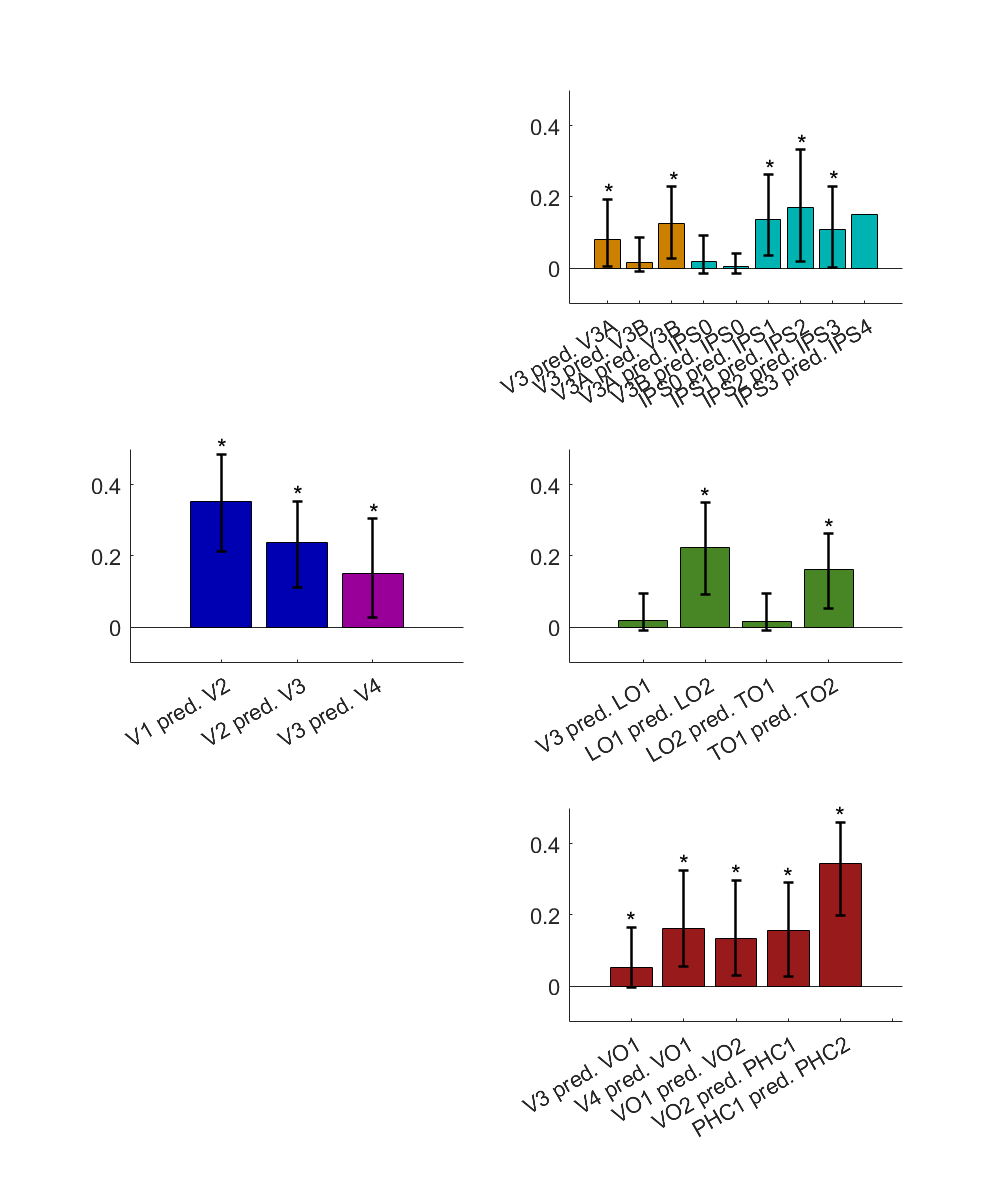

f = figure('Renderer', 'painters', 'Position', [10 10 1000 1200]);
s1 = subplot(3,2,3);
bar(1:2,vc_R2_human(1:2),'FaceColor',EVCcolor)
hold on;
bar(3,vc_R2_human(3),'FaceColor',V4color)
for i = 1:length(vc_p_human)
    errorbar(i,vc_R2_human(i),vc_R2_human(i)-vc_ci_human(i,1),vc_ci_human(i,2)-vc_R2_human(i),'k','LineWidth',1.5)
    if vc_p_human(i)<0.05
        text(i-0.05,vc_ci_human(i,2)+0.02,'*','FontSize',15)
    end
end
xticks(1:3)
xticklabels({'V1 pred. V2','V2 pred. V3','V3 pred. V4'})
xtickangle(30)
% ylabel('Lin. Reg. R^2')
ylim([-0.1 0.5])
s1.FontSize = 13;
box off

s2 = subplot(3,2,2);
bar(1:3,ips_R2_human(1:3),'FaceColor',dorsalcolor)
hold on;
bar(4:9,ips_R2_human(4:9),'FaceColor',parietalcolor)
for i = 1:length(ips_p_human)-1
    errorbar(i,ips_R2_human(i),ips_R2_human(i)-ips_ci_human(i,1),ips_ci_human(i,2)-ips_R2_human(i),'k','LineWidth',1.5)
    if ips_p_human(i)<0.05
        text(i-0.1,ips_ci_human(i,2)+0.02,'*','FontSize',15)
    end
end
xticks(1:9)
xticklabels({'V3 pred. V3A','V3 pred. V3B','V3A pred. V3B','V3A pred. IPS0','V3B pred. IPS0','IPS0 pred. IPS1','IPS1 pred. IPS2','IPS2 pred. IPS3','IPS3 pred. IPS4'})
ylim([-0.1 0.5])
xtickangle(30)
s2.FontSize = 13;
box off
% sgtitle('Human Single Area R^2')

s3 = subplot(3,2,4);
bar(lattemp_R2_human,'FaceColor',lateralcolor)
hold on;
for i = 1:length(lattemp_p_human)
    errorbar(i,lattemp_R2_human(i),lattemp_R2_human(i)-lattemp_ci_human(i,1),lattemp_ci_human(i,2)-lattemp_R2_human(i),'k','LineWidth',1.5)
    if lattemp_p_human(i)<0.05
        text(i-0.08,lattemp_ci_human(i,2)+0.02,'*','FontSize',15)
    end
end
xticklabels({'V3 pred. LO1','LO1 pred. LO2','LO2 pred. TO1','TO1 pred. TO2'})
xtickangle(30)
ylim([-0.1 0.5])
s3.FontSize = 13;
box off

s4 = subplot(3,2,6);
bar(1:5,ventral_R2_human(1:5),'FaceColor',ventralcolor)
hold on;
for i = 1:length(ventral_p_human)
    errorbar(i,ventral_R2_human(i),ventral_R2_human(i)-ventral_ci_human(i,1),ventral_ci_human(i,2)-ventral_R2_human(i),'k','LineWidth',1.5)
    if ventral_p_human(i)<0.05
        text(i-0.1,ventral_ci_human(i,2)+0.02,'*','FontSize',15)
    end
end
xticks(1:6)
xticklabels({'V3 pred. VO1','V4 pred. VO1','VO1 pred. VO2','VO2 pred. PHC1','PHC1 pred. PHC2'})
xtickangle(30)
ylim([-0.1 0.5])
s4.FontSize = 13;
box off

## HUMAN INDIVIDUAL MODELS - SPLIT

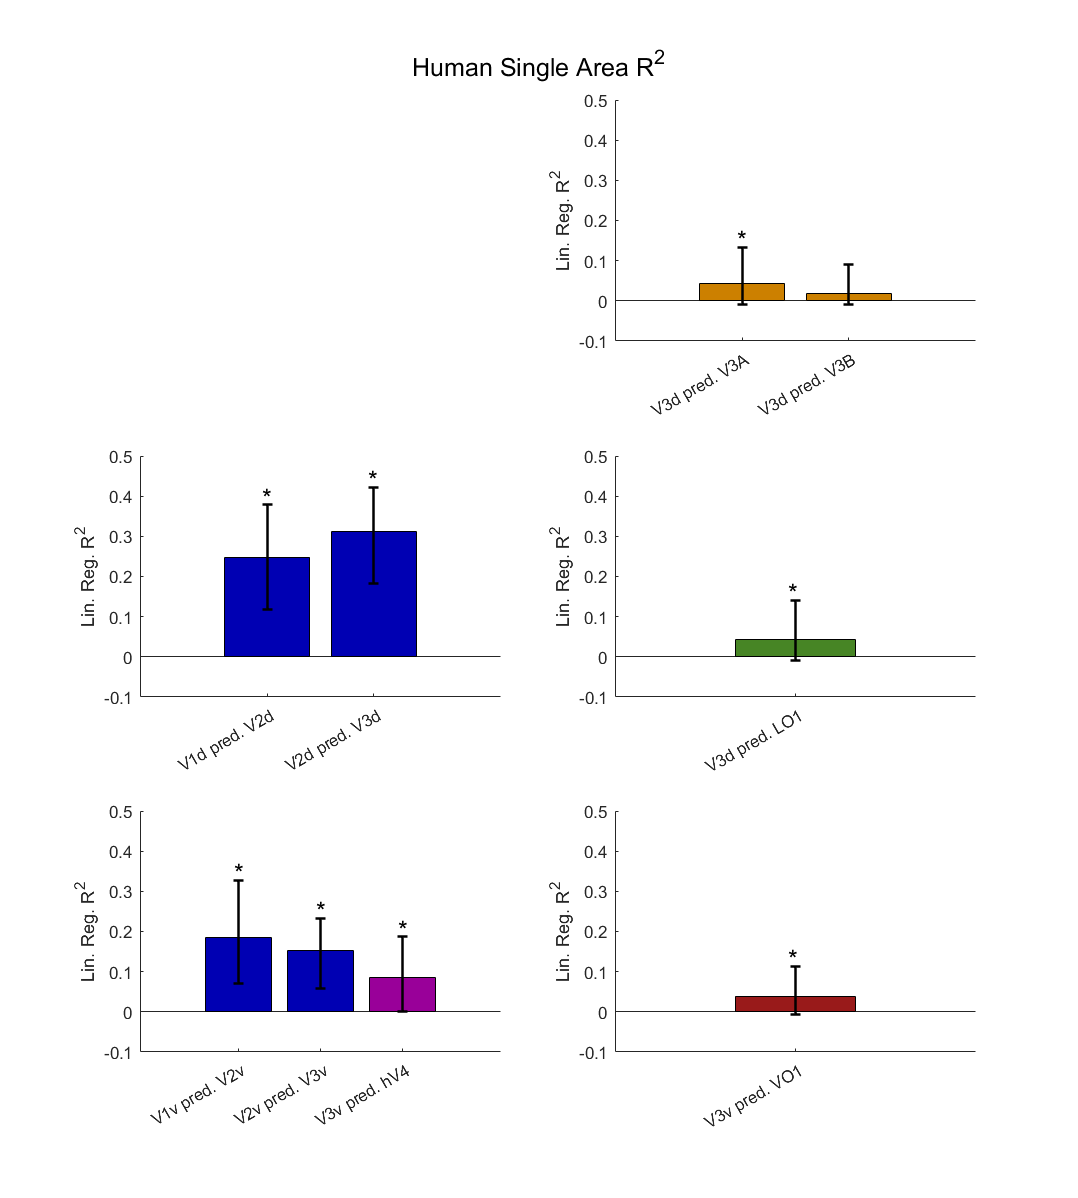

% p values refer to F-statistic of linear fit vs constant model

% vc
human_v1v_v2v_mdl = fitlm(v1v,v2v);
human_v1v_v2v_R2 = human_v1v_v2v_mdl.Rsquared.Ordinary;
human_v1v_v2v_p = anova(human_v1v_v2v_mdl,'summary').pValue('Model');
human_v1v_v2v_ci = bootci(1000,bootfun,v1v,v2v);

human_v1d_v2d_mdl = fitlm(v1d,v2d);
human_v1d_v2d_R2 = human_v1d_v2d_mdl.Rsquared.Ordinary;
human_v1d_v2d_p = anova(human_v1d_v2d_mdl,'summary').pValue('Model');
human_v1d_v2d_ci = bootci(1000,bootfun,v1d,v2d);

human_v2v_v3v_mdl = fitlm(v2v,v3v);
human_v2v_v3v_R2 = human_v2v_v3v_mdl.Rsquared.Ordinary;
human_v2v_v3v_p = anova(human_v2v_v3v_mdl,'summary').pValue('Model');
human_v2v_v3v_ci = bootci(1000,bootfun,v2v,v3v);

human_v2d_v3d_mdl = fitlm(v2d,v3d);
human_v2d_v3d_R2 = human_v2d_v3d_mdl.Rsquared.Ordinary;
human_v2d_v3d_p = anova(human_v2d_v3d_mdl,'summary').pValue('Model');
human_v2d_v3d_ci = bootci(1000,bootfun,v2d,v3d);

% lat temp
human_v3d_lo1_mdl = fitlm(v3d,lo1);
human_v3d_lo1_R2 = human_v3d_lo1_mdl.Rsquared.Ordinary;
human_v3d_lo1_p = anova(human_v3d_lo1_mdl,'summary').pValue('Model');
human_v3d_lo1_ci = bootci(1000,bootfun,v3d,lo1);

% ips
human_v3d_v3a_mdl = fitlm(v3d,v3a);
human_v3d_v3a_R2 = human_v3d_v3a_mdl.Rsquared.Ordinary;
human_v3d_v3a_p = anova(human_v3d_v3a_mdl,'summary').pValue('Model');
human_v3d_v3a_ci = bootci(1000,bootfun,v3d,v3a);

human_v3d_v3b_mdl = fitlm(v3d,v3b);
human_v3d_v3b_R2 = human_v3d_v3b_mdl.Rsquared.Ordinary;
human_v3d_v3b_p = anova(human_v3d_v3b_mdl,'summary').pValue('Model');
human_v3d_v3b_ci = bootci(1000,bootfun,v3d,v3b);

% ventral
human_v3v_v4_mdl = fitlm(v3v,v4);
human_v3v_v4_R2 = human_v3v_v4_mdl.Rsquared.Ordinary;
human_v3v_v4_p = anova(human_v3v_v4_mdl,'summary').pValue('Model');
human_v3v_v4_ci = bootci(1000,bootfun,v3v,v4);

human_v3v_vo1_mdl = fitlm(v3v,vo1);
human_v3v_vo1_R2 = human_v3v_vo1_mdl.Rsquared.Ordinary;
human_v3v_vo1_p = anova(human_v3v_vo1_mdl,'summary').pValue('Model');
human_v3v_vo1_ci = bootci(1000,bootfun,v3v,vo1);


vc_R2_human_split_v = [human_v1v_v2v_R2;human_v2v_v3v_R2;human_v3v_v4_R2];
vc_p_human_split_v = [human_v1v_v2v_p;human_v2v_v3v_p;human_v3v_v4_p];
vc_ci_human_split_v = [human_v1v_v2v_ci';human_v2v_v3v_ci';human_v3v_v4_ci'];
vc_R2_human_split_d = [human_v1d_v2d_R2;human_v2d_v3d_R2];
vc_p_human_split_d = [human_v1d_v2d_p;human_v2d_v3d_p];
vc_ci_human_split_d = [human_v1d_v2d_ci';human_v2d_v3d_ci'];
lattemp_R2_human_split = [human_v3d_lo1_R2];
lattemp_p_human_split = [human_v3d_lo1_p];
lattemp_ci_human_split = [human_v3d_lo1_ci'];
ips_R2_human_split = [human_v3d_v3a_R2;human_v3d_v3b_R2];
ips_p_human_split = [human_v3d_v3a_p;human_v3d_v3b_p];
ips_ci_human_split = [human_v3d_v3a_ci';human_v3d_v3b_ci'];
ventral_R2_human_split = [human_v3v_vo1_R2];
ventral_p_human_split = [human_v3v_vo1_p];
ventral_ci_human_split = [human_v3v_vo1_ci'];

f = figure('Renderer', 'painters', 'Position', [10 10 900 1000]);
hold on;
subplot(3,2,3)
hold on;
bar(vc_R2_human_split_d,'FaceColor',EVCcolor)
for i = 1:length(vc_p_human_split_d)
    errorbar(i,vc_R2_human_split_d(i),vc_R2_human_split_d(i)-vc_ci_human_split_d(i,1),vc_ci_human_split_d(i,2)-vc_R2_human_split_d(i),'k','LineWidth',1.5)
    if vc_p_human_split_d(i)<0.05
        text(i-0.05,vc_ci_human_split_d(i,2)+0.02,'*','FontSize',15)
    end
end
xticks(1:2)
xticklabels({'V1d pred. V2d','V2d pred. V3d'})
xtickangle(30)
ylabel('Lin. Reg. R^2')
ylim([-0.1 0.5])
box off

subplot(3,2,5)
hold on;
bar(1:2,vc_R2_human_split_v(1:2),'FaceColor',EVCcolor)
hold on;
bar(3,vc_R2_human_split_v(3),'FaceColor',V4color)
for i = 1:length(vc_p_human_split_v)
    errorbar(i,vc_R2_human_split_v(i),vc_R2_human_split_v(i)-vc_ci_human_split_v(i,1),vc_ci_human_split_v(i,2)-vc_R2_human_split_v(i),'k','LineWidth',1.5)
    if vc_p_human_split_v(i)<0.05
        text(i-0.05,vc_ci_human_split_v(i,2)+0.02,'*','FontSize',15)
    end
end
xticks(1:3)
xticklabels({'V1v pred. V2v','V2v pred. V3v','V3v pred. hV4'})
xtickangle(30)
ylabel('Lin. Reg. R^2')
ylim([-0.1 0.5])
box off

subplot(3,2,2)
hold on;
bar(1:2,ips_R2_human_split,'FaceColor',dorsalcolor)
for i = 1:length(ips_p_human_split)
    errorbar(i,ips_R2_human_split(i),ips_R2_human_split(i)-ips_ci_human_split(i,1),ips_ci_human_split(i,2)-ips_R2_human_split(i),'k','LineWidth',1.5)
    if ips_p_human_split(i)<0.05
        text(i-0.05,ips_ci_human_split(i,2)+0.02,'*','FontSize',15)
    end
end
xticks(1:2)
xticklabels({'V3d pred. V3A','V3d pred. V3B'})
ylabel('Lin. Reg. R^2')
ylim([-0.1 0.5])
xtickangle(30)
box off
sgtitle('Human Single Area R^2')

subplot(3,2,4)
hold on;
bar(lattemp_R2_human_split,'FaceColor',lateralcolor)
for i = 1:length(lattemp_p_human_split)
    errorbar(i,lattemp_R2_human_split(i),lattemp_R2_human_split(i)-lattemp_ci_human_split(i,1),lattemp_ci_human_split(i,2)-lattemp_R2_human_split(i),'k','LineWidth',1.5)
    if lattemp_p_human_split(i)<0.05
        text(i-0.05,lattemp_ci_human_split(i,2)+0.02,'*','FontSize',15)
    end
end
xticks(1)
xticklabels({'V3d pred. LO1'})
ylabel('Lin. Reg. R^2')
xtickangle(30)
ylim([-0.1 0.5])
box off

subplot(3,2,6)
hold on;
bar(ventral_R2_human_split,'FaceColor',ventralcolor)
for i = 1:length(ventral_p_human_split)
    errorbar(i,ventral_R2_human_split(i),ventral_R2_human_split(i)-ventral_ci_human_split(i,1),ventral_ci_human_split(i,2)-ventral_R2_human_split(i),'k','LineWidth',1.5)
    if ventral_p_human_split(i)<0.05
        text(i-0.05,ventral_ci_human_split(i,2)+0.02,'*','FontSize',15)
    end
end
xticks(1)
xticklabels({'V3v pred. VO1'})
ylabel('Lin. Reg. R^2')
xtickangle(30)
ylim([-0.1 0.5])
box off
sgtitle('Human Single Area R^2')

## HUMAN SINGLE MODELS ACCOUNTING FOR BRAIN SIZE

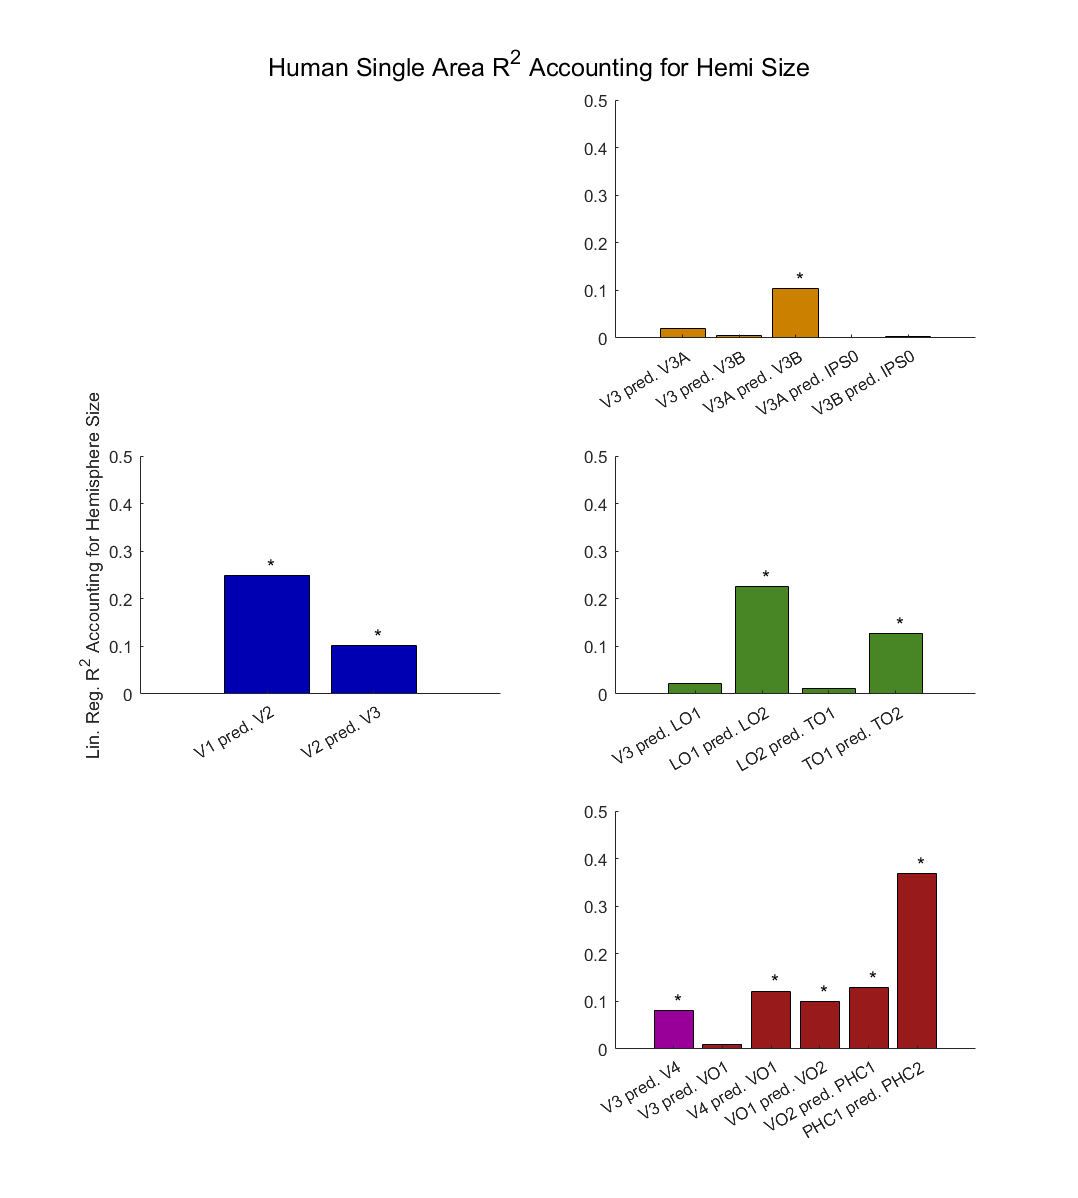

% HUMAN INDIVIDUAL MODELS
% p values refer to F-statistic of linear fit vs constant model

human_area_resid1 = fitlm(total_area_cat_human,v1);
human_area_resid2 = fitlm(total_area_cat_human,v2);
resid_1 = human_area_resid1.Residuals.Raw;
resid_2 = human_area_resid2.Residuals.Raw;
human_r1_r2_mdl = fitlm(resid_1,resid_2);
human_v1_v2_R2_resid = human_r1_r2_mdl.Rsquared.Ordinary;
human_v1_v2_p_resid = anova(human_r1_r2_mdl,'summary').pValue('Model');

human_area_resid1 = fitlm(total_area_cat_human,v2);
human_area_resid2 = fitlm(total_area_cat_human,v3);
resid_1 = human_area_resid1.Residuals.Raw;
resid_2 = human_area_resid2.Residuals.Raw;
human_r1_r2_mdl = fitlm(resid_1,resid_2);
human_v2_v3_R2_resid = human_r1_r2_mdl.Rsquared.Ordinary;
human_v2_v3_p_resid = anova(human_r1_r2_mdl,'summary').pValue('Model');

human_area_resid1 = fitlm(total_area_cat_human,v3);
human_area_resid2 = fitlm(total_area_cat_human,lo1);
resid_1 = human_area_resid1.Residuals.Raw;
resid_2 = human_area_resid2.Residuals.Raw;
human_r1_r2_mdl = fitlm(resid_1,resid_2);
human_v3_lo1_R2_resid = human_r1_r2_mdl.Rsquared.Ordinary;
human_v3_lo1_p_resid = anova(human_r1_r2_mdl,'summary').pValue('Model');

human_area_resid1 = fitlm(total_area_cat_human,lo1);
human_area_resid2 = fitlm(total_area_cat_human,lo2);
resid_1 = human_area_resid1.Residuals.Raw;
resid_2 = human_area_resid2.Residuals.Raw;
human_r1_r2_mdl = fitlm(resid_1,resid_2);
human_lo1_lo2_R2_resid = human_r1_r2_mdl.Rsquared.Ordinary;
human_lo1_lo2_p_resid = anova(human_r1_r2_mdl,'summary').pValue('Model');

human_area_resid1 = fitlm(total_area_cat_human,lo2);
human_area_resid2 = fitlm(total_area_cat_human,to1);
resid_1 = human_area_resid1.Residuals.Raw;
resid_2 = human_area_resid2.Residuals.Raw;
human_r1_r2_mdl = fitlm(resid_1,resid_2);
human_lo2_to1_R2_resid = human_r1_r2_mdl.Rsquared.Ordinary;
human_lo2_to1_p_resid = anova(human_r1_r2_mdl,'summary').pValue('Model');

human_area_resid1 = fitlm(total_area_cat_human,to1);
human_area_resid2 = fitlm(total_area_cat_human,to2);
resid_1 = human_area_resid1.Residuals.Raw;
resid_2 = human_area_resid2.Residuals.Raw;
human_r1_r2_mdl = fitlm(resid_1,resid_2);
human_to1_to2_R2_resid = human_r1_r2_mdl.Rsquared.Ordinary;
human_to1_to2_p_resid = anova(human_r1_r2_mdl,'summary').pValue('Model');

human_area_resid1 = fitlm(total_area_cat_human,v3);
human_area_resid2 = fitlm(total_area_cat_human,v3a);
resid_1 = human_area_resid1.Residuals.Raw;
resid_2 = human_area_resid2.Residuals.Raw;
human_r1_r2_mdl = fitlm(resid_1,resid_2);
human_v3_v3a_R2_resid = human_r1_r2_mdl.Rsquared.Ordinary;
human_v3_v3a_p_resid = anova(human_r1_r2_mdl,'summary').pValue('Model');

human_area_resid1 = fitlm(total_area_cat_human,v3);
human_area_resid2 = fitlm(total_area_cat_human,v3b);
resid_1 = human_area_resid1.Residuals.Raw;
resid_2 = human_area_resid2.Residuals.Raw;
human_r1_r2_mdl = fitlm(resid_1,resid_2);
human_v3_v3b_R2_resid = human_r1_r2_mdl.Rsquared.Ordinary;
human_v3_v3b_p_resid = anova(human_r1_r2_mdl,'summary').pValue('Model');

human_area_resid1 = fitlm(total_area_cat_human,v3a);
human_area_resid2 = fitlm(total_area_cat_human,v3b);
resid_1 = human_area_resid1.Residuals.Raw;
resid_2 = human_area_resid2.Residuals.Raw;
human_r1_r2_mdl = fitlm(resid_1,resid_2);
human_v3a_v3b_R2_resid = human_r1_r2_mdl.Rsquared.Ordinary;
human_v3a_v3b_p_resid = anova(human_r1_r2_mdl,'summary').pValue('Model');

human_area_resid1 = fitlm(total_area_cat_human,v3a);
human_area_resid2 = fitlm(total_area_cat_human,ips0);
resid_1 = human_area_resid1.Residuals.Raw;
resid_2 = human_area_resid2.Residuals.Raw;
human_r1_r2_mdl = fitlm(resid_1,resid_2);
human_v3a_ips0_R2_resid = human_r1_r2_mdl.Rsquared.Ordinary;
human_v3a_ips0_p_resid = anova(human_r1_r2_mdl,'summary').pValue('Model');

human_area_resid1 = fitlm(total_area_cat_human,v3b);
human_area_resid2 = fitlm(total_area_cat_human,ips0);
resid_1 = human_area_resid1.Residuals.Raw;
resid_2 = human_area_resid2.Residuals.Raw;
human_r1_r2_mdl = fitlm(resid_1,resid_2);
human_v3b_ips0_R2_resid = human_r1_r2_mdl.Rsquared.Ordinary;
human_v3b_ips0_p_resid = anova(human_r1_r2_mdl,'summary').pValue('Model');

human_area_resid1 = fitlm(total_area_cat_human,v3);
human_area_resid2 = fitlm(total_area_cat_human,v4);
resid_1 = human_area_resid1.Residuals.Raw;
resid_2 = human_area_resid2.Residuals.Raw;
human_r1_r2_mdl = fitlm(resid_1,resid_2);
human_v3_v4_R2_resid = human_r1_r2_mdl.Rsquared.Ordinary;
human_v3_v4_p_resid = anova(human_r1_r2_mdl,'summary').pValue('Model');

human_area_resid1 = fitlm(total_area_cat_human,v3);
human_area_resid2 = fitlm(total_area_cat_human,vo1);
resid_1 = human_area_resid1.Residuals.Raw;
resid_2 = human_area_resid2.Residuals.Raw;
human_r1_r2_mdl = fitlm(resid_1,resid_2);
human_v3_vo1_R2_resid = human_r1_r2_mdl.Rsquared.Ordinary;
human_v3_vo1_p_resid = anova(human_r1_r2_mdl,'summary').pValue('Model');

human_area_resid1 = fitlm(total_area_cat_human,v4);
human_area_resid2 = fitlm(total_area_cat_human,vo1);
resid_1 = human_area_resid1.Residuals.Raw;
resid_2 = human_area_resid2.Residuals.Raw;
human_r1_r2_mdl = fitlm(resid_1,resid_2);
human_v4_vo1_R2_resid = human_r1_r2_mdl.Rsquared.Ordinary;
human_v4_vo1_p_resid = anova(human_r1_r2_mdl,'summary').pValue('Model');

human_area_resid1 = fitlm(total_area_cat_human,vo1);
human_area_resid2 = fitlm(total_area_cat_human,vo2);
resid_1 = human_area_resid1.Residuals.Raw;
resid_2 = human_area_resid2.Residuals.Raw;
human_r1_r2_mdl = fitlm(resid_1,resid_2);
human_vo1_vo2_R2_resid = human_r1_r2_mdl.Rsquared.Ordinary;
human_vo1_vo2_p_resid = anova(human_r1_r2_mdl,'summary').pValue('Model');

human_area_resid1 = fitlm(total_area_cat_human,vo2);
human_area_resid2 = fitlm(total_area_cat_human,phc1);
resid_1 = human_area_resid1.Residuals.Raw;
resid_2 = human_area_resid2.Residuals.Raw;
human_r1_r2_mdl = fitlm(resid_1,resid_2);
human_vo2_phc1_R2_resid = human_r1_r2_mdl.Rsquared.Ordinary;
human_vo2_phc1_p_resid = anova(human_r1_r2_mdl,'summary').pValue('Model');

human_area_resid1 = fitlm(total_area_cat_human,phc1);
human_area_resid2 = fitlm(total_area_cat_human,phc2);
resid_1 = human_area_resid1.Residuals.Raw;
resid_2 = human_area_resid2.Residuals.Raw;
human_r1_r2_mdl = fitlm(resid_1,resid_2);
human_phc1_phc2_R2_resid = human_r1_r2_mdl.Rsquared.Ordinary;
human_phc1_phc2_p_resid = anova(human_r1_r2_mdl,'summary').pValue('Model');

vc_R2_human = [human_v1_v2_R2_resid;human_v2_v3_R2_resid];
vc_p_human = [human_v1_v2_p_resid;human_v2_v3_p_resid];
lattemp_R2_human = [human_v3_lo1_R2_resid;human_lo1_lo2_R2_resid;human_lo2_to1_R2_resid;human_to1_to2_R2_resid];
lattemp_p_human = [human_v3_lo1_p_resid;human_lo1_lo2_p_resid;human_lo2_to1_p_resid;human_to1_to2_p_resid];
ips_R2_human = [human_v3_v3a_R2_resid;human_v3_v3b_R2_resid;human_v3a_v3b_R2_resid;human_v3a_ips0_R2_resid;human_v3b_ips0_R2_resid];
ips_p_human = [human_v3_v3a_p_resid;human_v3_v3b_p_resid;human_v3a_v3b_p_resid;human_v3a_ips0_p_resid;human_v3b_ips0_p_resid];
ventral_R2_human = [human_v3_v4_R2_resid;human_v3_vo1_R2_resid;human_v4_vo1_R2_resid;human_vo1_vo2_R2_resid;human_vo2_phc1_R2_resid;human_phc1_phc2_R2_resid];
ventral_p_human = [human_v3_v4_p_resid;human_v3_vo1_p_resid;human_v4_vo1_p_resid;human_vo1_vo2_p_resid;human_vo2_phc1_p_resid;human_phc1_phc2_p_resid];

f = figure('Renderer', 'painters', 'Position', [10 10 900 1000]);
subplot(3,2,3)
bar(vc_R2_human,'FaceColor',EVCcolor)
for i = 1:length(vc_p_human)
    if vc_p_human(i)<0.05
        text(i,vc_R2_human(i)+0.02,'*','FontSize',12)
    end
end
xticklabels({'V1 pred. V2','V2 pred. V3'})
xtickangle(30)
ylabel('Lin. Reg. R^2 Accounting for Hemisphere Size')
ylim([0 0.5])
box off

subplot(3,2,2)
bar(1:3,ips_R2_human(1:3),'FaceColor',dorsalcolor)
hold on;
bar(4:5,ips_R2_human(4:5),'FaceColor',parietalcolor)
for i = 1:length(ips_p_human)
    if ips_p_human(i)<0.05
        text(i,ips_R2_human(i)+0.02,'*','FontSize',12)
    end
end
xticks(1:5)
xticklabels({'V3 pred. V3A','V3 pred. V3B','V3A pred. V3B','V3A pred. IPS0','V3B pred. IPS0'})
ylim([0 0.5])
xtickangle(30)
box off

subplot(3,2,4)
bar(lattemp_R2_human,'FaceColor',lateralcolor)
for i = 1:length(lattemp_p_human)
    if lattemp_p_human(i)<0.05
        text(i,lattemp_R2_human(i)+0.02,'*','FontSize',12)
    end
end
xticklabels({'V3 pred. LO1','LO1 pred. LO2','LO2 pred. TO1','TO1 pred. TO2'})
xtickangle(30)
ylim([0 0.5])
box off

subplot(3,2,6)
bar(1,ventral_R2_human(1),'FaceColor',V4color)
hold on;
bar(2:6,ventral_R2_human(2:6),'FaceColor',ventralcolor)
for i = 1:length(ventral_p_human)
    if ventral_p_human(i)<0.05
        text(i,ventral_R2_human(i)+0.02,'*','FontSize',12)
    end
end
xticks(1:6)
xticklabels({'V3 pred. V4','V3 pred. VO1','V4 pred. VO1','VO1 pred. VO2','VO2 pred. PHC1','PHC1 pred. PHC2'})
xtickangle(30)
ylim([0 0.5])
box off
sgtitle('Human Single Area R^2 Accounting for Hemi Size')

## HUMAN CUMULATIVE MODELS

% v1v2 = [v1;v2]';
% v1v2v3 = [v1;v2;v3]';
% % v1v2v3v4 = [v1;v2;v3;v4]';
% % v1v2v3v4vo1 = [v1;v2;v3;v4;vo1]';
% % v1v2v3v4vo1vo2 = [v1;v2;v3;v4;vo1;vo2]';
% % v1v2v3v4vo1vo2phc1 = [v1;v2;v3;v4;vo1;vo2;phc1]';
% % v1v2v3lo1 = [v1;v2;v3;lo1]';
% % v1v2v3lo1lo2 = [v1;v2;v3;lo1;lo2]';
% % v1v2v3lo1lo2to1 = [v1;v2;v3;lo1;lo2;to1]';
% % v1v2v3v3a = [v1;v2;v3;v3a]';
% % v1v2v3v3b = [v1;v2;v3;v3b]';
% % v1v2v3v3av3b = [v1;v2;v3;v3a;v3b]';
% % v1v2v3v3aips0 = [v1;v2;v3;v3a;ips0]';
% % v1v2v3v3bips0 = [v1;v2;v3;v3b;ips0]';
% 
% human_v1v2_v3_mdl = fitlm(v1v2,v3);
% human_v1v2_v3_R2 = human_v1v2_v3_mdl.Rsquared.Ordinary;
% human_v1v2_v3_p = anova(human_v1v2_v3_mdl,'summary').pValue('Model');
% human_v1v2_v3_ci = bootci(1000,bootfun,v1v2,v3);
% 
% human_v1v2v3_lo1_mdl = fitlm(v1v2v3,lo1);
% human_v1v2v3_lo1_R2 = human_v1v2v3_lo1_mdl.Rsquared.Ordinary;
% human_v1v2v3_lo1_p = anova(human_v1v2v3_lo1_mdl,'summary').pValue('Model');
% human_v1v2v3_lo1_ci = bootci(1000,bootfun,v1v2v3,lo1);
% 
% human_v1v2v3_lo2_mdl = fitlm(v1v2v3,lo2);
% human_v1v2v3_lo2_R2 = human_v1v2v3_lo2_mdl.Rsquared.Ordinary;
% human_v1v2v3_lo2_p = anova(human_v1v2v3_lo2_mdl,'summary').pValue('Model');
% human_v1v2v3_lo2_ci = bootci(1000,bootfun,v1v2v3,lo2);
% 
% % human_v1v2v3lo1_lo2_mdl = fitlm(v1v2v3lo1,lo2);
% % human_v1v2v3lo1_lo2_R2 = human_v1v2v3lo1_lo2_mdl.Rsquared.Ordinary;
% % human_v1v2v3lo1_lo2_p = anova(human_v1v2v3lo1_lo2_mdl,'summary').pValue('Model');
% 
% human_v1v2v3_to1_mdl = fitlm(v1v2v3,to1);
% human_v1v2v3_to1_R2 = human_v1v2v3_to1_mdl.Rsquared.Ordinary;
% human_v1v2v3_to1_p = anova(human_v1v2v3_to1_mdl,'summary').pValue('Model');
% human_v1v2v3_to1_ci = bootci(1000,bootfun,v1v2v3,to1);
% 
% % human_v1v2v3lo1lo2_to1_mdl = fitlm(v1v2v3lo1lo2,to1);
% % human_v1v2v3lo1lo2_to1_R2 = human_v1v2v3lo1lo2_to1_mdl.Rsquared.Ordinary;
% % human_v1v2v3lo1lo2_to1_p = anova(human_v1v2v3lo1lo2_to1_mdl,'summary').pValue('Model');
% 
% human_v1v2v3_to2_mdl = fitlm(v1v2v3,to2);
% human_v1v2v3_to2_R2 = human_v1v2v3_to2_mdl.Rsquared.Ordinary;
% human_v1v2v3_to2_p = anova(human_v1v2v3_to2_mdl,'summary').pValue('Model');
% human_v1v2v3_to2_ci = bootci(1000,bootfun,v1v2v3,to2);
% 
% % human_v1v2v3lo1lo2to1_to2_mdl = fitlm(v1v2v3lo1lo2to1,to2);
% % human_v1v2v3lo1lo2to1_to2_R2 = human_v1v2v3lo1lo2to1_to2_mdl.Rsquared.Ordinary;
% % human_v1v2v3lo1lo2to1_to2_p = anova(human_v1v2v3lo1lo2to1_to2_mdl,'summary').pValue('Model');
% 
% human_v1v2v3_v3a_mdl = fitlm(v1v2v3,v3a);
% human_v1v2v3_v3a_R2 = human_v1v2v3_v3a_mdl.Rsquared.Ordinary;
% human_v1v2v3_v3a_p = anova(human_v1v2v3_v3a_mdl,'summary').pValue('Model');
% human_v1v2v3_v3a_ci = bootci(1000,bootfun,v1v2v3,v3a);
% 
% human_v1v2v3_v3b_mdl = fitlm(v1v2v3,v3b);
% human_v1v2v3_v3b_R2 = human_v1v2v3_v3b_mdl.Rsquared.Ordinary;
% human_v1v2v3_v3b_p = anova(human_v1v2v3_v3b_mdl,'summary').pValue('Model');
% human_v1v2v3_v3b_ci = bootci(1000,bootfun,v1v2v3,v3b);
% 
% % human_v1v2v3v3a_ips0_mdl = fitlm(v1v2v3v3a,ips0);
% % human_v1v2v3v3a_ips0_R2 = human_v1v2v3v3a_ips0_mdl.Rsquared.Ordinary;
% % human_v1v2v3v3a_ips0_p = anova(human_v1v2v3v3a_ips0_mdl,'summary').pValue('Model');
% % 
% % human_v1v2v3v3b_ips0_mdl = fitlm(v1v2v3v3b,ips0);
% % human_v1v2v3v3b_ips0_R2 = human_v1v2v3v3b_ips0_mdl.Rsquared.Ordinary;
% % human_v1v2v3v3b_ips0_p = anova(human_v1v2v3v3b_ips0_mdl,'summary').pValue('Model');
% 
% human_v1v2v3_ips0_mdl = fitlm(v1v2v3,ips0);
% human_v1v2v3_ips0_R2 = human_v1v2v3_ips0_mdl.Rsquared.Ordinary;
% human_v1v2v3_ips0_p = anova(human_v1v2v3_ips0_mdl,'summary').pValue('Model');
% human_v1v2v3_ips0_ci = bootci(1000,bootfun,v1v2v3,ips0);
% 
% human_v1v2v3_ips1_mdl = fitlm(v1v2v3,ips1);
% human_v1v2v3_ips1_R2 = human_v1v2v3_ips1_mdl.Rsquared.Ordinary;
% human_v1v2v3_ips1_p = anova(human_v1v2v3_ips1_mdl,'summary').pValue('Model');
% human_v1v2v3_ips1_ci = bootci(1000,bootfun,v1v2v3,ips1);
% 
% human_v1v2v3_ips2_mdl = fitlm(v1v2v3,ips2);
% human_v1v2v3_ips2_R2 = human_v1v2v3_ips2_mdl.Rsquared.Ordinary;
% human_v1v2v3_ips2_p = anova(human_v1v2v3_ips2_mdl,'summary').pValue('Model');
% human_v1v2v3_ips2_ci = bootci(1000,bootfun,v1v2v3,ips2);
% 
% human_v1v2v3_ips3_mdl = fitlm(v1v2v3,ips3);
% human_v1v2v3_ips3_R2 = human_v1v2v3_ips3_mdl.Rsquared.Ordinary;
% human_v1v2v3_ips3_p = anova(human_v1v2v3_ips3_mdl,'summary').pValue('Model');
% human_v1v2v3_ips3_ci = bootci(1000,bootfun,v1v2v3,ips3);
% 
% human_v1v2v3_ips4_mdl = fitlm(v1v2v3,ips4);
% human_v1v2v3_ips4_R2 = human_v1v2v3_ips4_mdl.Rsquared.Ordinary;
% human_v1v2v3_ips4_p = anova(human_v1v2v3_ips4_mdl,'summary').pValue('Model');
% human_v1v2v3_ips4_ci = bootci(1000,bootfun,v1v2v3,ips4);
% 
% human_v1v2v3_ips5_mdl = fitlm(v1v2v3,ips5);
% human_v1v2v3_ips5_R2 = human_v1v2v3_ips5_mdl.Rsquared.Ordinary;
% human_v1v2v3_ips5_p = anova(human_v1v2v3_ips5_mdl,'summary').pValue('Model');
% human_v1v2v3_ips5_ci = bootci(1000,bootfun,v1v2v3,ips5);
% 
% % 
% % human_v1v2v3v3av3b_ips0_mdl = fitlm(v1v2v3v3av3b,ips0);
% % human_v1v2v3v3av3b_ips0_R2 = human_v1v2v3v3av3b_ips0_mdl.Rsquared.Ordinary;
% % human_v1v2v3v3av3b_ips0_p = anova(human_v1v2v3v3av3b_ips0_mdl,'summary').pValue('Model');
% 
% human_v1v2v3_v4_mdl = fitlm(v1v2v3,v4);
% human_v1v2v3_v4_R2 = human_v1v2v3_v4_mdl.Rsquared.Ordinary;
% human_v1v2v3_v4_p = anova(human_v1v2v3_v4_mdl,'summary').pValue('Model');
% human_v1v2v3_v4_ci = bootci(1000,bootfun,v1v2v3,v4);
% 
% human_v1v2v3_vo1_mdl = fitlm(v1v2v3,vo1);
% human_v1v2v3_vo1_R2 = human_v1v2v3_vo1_mdl.Rsquared.Ordinary;
% human_v1v2v3_vo1_p = anova(human_v1v2v3_vo1_mdl,'summary').pValue('Model');
% human_v1v2v3_vo1_ci = bootci(1000,bootfun,v1v2v3,vo1);
% 
% % human_v1v2v3v4_vo1_mdl = fitlm(v1v2v3v4,vo1);
% % human_v1v2v3v4_vo1_R2 = human_v1v2v3v4_vo1_mdl.Rsquared.Ordinary;
% % human_v1v2v3v4_vo1_p = anova(human_v1v2v3v4_vo1_mdl,'summary').pValue('Model');
% 
% human_v1v2v3_vo2_mdl = fitlm(v1v2v3,vo2);
% human_v1v2v3_vo2_R2 = human_v1v2v3_vo2_mdl.Rsquared.Ordinary;
% human_v1v2v3_vo2_p = anova(human_v1v2v3_vo2_mdl,'summary').pValue('Model');
% human_v1v2v3_vo2_ci = bootci(1000,bootfun,v1v2v3,vo2);
% 
% % human_v1v2v3v4vo1_vo2_mdl = fitlm(v1v2v3v4vo1,vo2);
% % human_v1v2v3v4vo1_vo2_R2 = human_v1v2v3v4vo1_vo2_mdl.Rsquared.Ordinary;
% % human_v1v2v3v4vo1_vo2_p = anova(human_v1v2v3v4vo1_vo2_mdl,'summary').pValue('Model');
% 
% human_v1v2v3_phc1_mdl = fitlm(v1v2v3,phc1);
% human_v1v2v3_phc1_R2 = human_v1v2v3_phc1_mdl.Rsquared.Ordinary;
% human_v1v2v3_phc1_p = anova(human_v1v2v3_phc1_mdl,'summary').pValue('Model');
% human_v1v2v3_phc1_ci = bootci(1000,bootfun,v1v2v3,phc1);
% 
% % human_v1v2v3v4vo1vo2_phc1_mdl = fitlm(v1v2v3v4vo1vo2,phc1);
% % human_v1v2v3v4vo1vo2_phc1_R2 = human_v1v2v3v4vo1vo2_phc1_mdl.Rsquared.Ordinary;
% % human_v1v2v3v4vo1vo2_phc1_p = anova(human_v1v2v3v4vo1vo2_phc1_mdl,'summary').pValue('Model');
% 
% human_v1v2v3_phc2_mdl = fitlm(v1v2v3,phc2);
% human_v1v2v3_phc2_R2 = human_v1v2v3_phc2_mdl.Rsquared.Ordinary;
% human_v1v2v3_phc2_p = anova(human_v1v2v3_phc2_mdl,'summary').pValue('Model');
% human_v1v2v3_phc2_ci = bootci(1000,bootfun,v1v2v3,phc2);
% 
% % human_v1v2v3v4vo1vo2phc1_phc2_mdl = fitlm(v1v2v3v4vo1vo2phc1,phc2);
% % human_v1v2v3v4vo1vo2phc1_phc2_R2 = human_v1v2v3v4vo1vo2phc1_phc2_mdl.Rsquared.Ordinary;
% % human_v1v2v3v4vo1vo2phc1_phc2_p = anova(human_v1v2v3v4vo1vo2phc1_phc2_mdl,'summary').pValue('Model');
% 
% vc_cumul_R2_human = [human_v1_v2_R2;human_v1v2_v3_R2;human_v1v2v3_v4_R2];
% vc_cumul_p_human = [human_v1_v2_p;human_v1v2_v3_p;human_v1v2v3_v4_p];
% vc_cumul_ci_human = [human_v1_v2_ci';human_v1v2_v3_ci';human_v1v2v3_v4_ci'];
% lattemp_cumul_R2_human = [human_v1v2v3_lo1_R2;human_v1v2v3_lo2_R2;human_v1v2v3_to1_R2;human_v1v2v3_to2_R2];
% lattemp_cumul_p_human = [human_v1v2v3_lo1_p;human_v1v2v3_lo2_p;human_v1v2v3_to1_p;human_v1v2v3_to2_p];
% lattemp_cumul_ci_human = [human_v1v2v3_lo1_ci';human_v1v2v3_lo2_ci';human_v1v2v3_to1_ci';human_v1v2v3_to2_ci'];
% ips_cumul_R2_human = [human_v1v2v3_v3a_R2;human_v1v2v3_v3b_R2;human_v1v2v3_ips0_R2;human_v1v2v3_ips1_R2;human_v1v2v3_ips2_R2;human_v1v2v3_ips3_R2;human_v1v2v3_ips4_R2;human_v1v2v3_ips5_R2];
% ips_cumul_p_human = [human_v1v2v3_v3a_p;human_v1v2v3_v3b_p;human_v1v2v3_ips0_p;human_v1v2v3_ips1_p;human_v1v2v3_ips2_p;human_v1v2v3_ips3_p;human_v1v2v3_ips4_p;human_v1v2v3_ips5_p];
% ips_cumul_ci_human = [human_v1v2v3_v3a_ci';human_v1v2v3_v3b_ci';human_v1v2v3_ips0_ci';human_v1v2v3_ips1_ci';human_v1v2v3_ips2_ci';human_v1v2v3_ips3_ci';human_v1v2v3_ips4_ci';human_v1v2v3_ips5_ci'];
% ventral_cumul_R2_human = [human_v1v2v3_vo1_R2;human_v1v2v3_vo2_R2;human_v1v2v3_phc1_R2;human_v1v2v3_phc2_R2];
% ventral_cumul_p_human = [human_v1v2v3_vo1_p;human_v1v2v3_vo2_p;human_v1v2v3_phc1_p;human_v1v2v3_phc2_p];
% ventral_cumul_ci_human = [human_v1v2v3_vo1_ci';human_v1v2v3_vo2_ci';human_v1v2v3_phc1_ci';human_v1v2v3_phc2_ci'];

% vc_cumul_R2_human = [human_v1_v2_R2;human_v1v2_v3_R2];
% vc_cumul_p_human = [human_v1_v2_p;human_v1v2_v3_p];
% lattemp_cumul_R2_human = [human_v1v2v3_lo1_R2;human_v1v2v3lo1_lo2_R2;human_v1v2v3lo1lo2_to1_R2;human_v1v2v3lo1lo2to1_to2_R2];
% lattemp_cumul_p_human = [human_v1v2v3_lo1_p;human_v1v2v3lo1_lo2_p;human_v1v2v3lo1lo2_to1_p;human_v1v2v3lo1lo2to1_to2_p];
% ips_cumul_R2_human = [human_v1v2v3_v3a_R2;human_v1v2v3_v3b_R2;human_v1v2v3v3a_ips0_R2;human_v1v2v3v3b_ips0_R2;human_v1v2v3v3av3b_ips0_R2];
% ips_cumul_p_human = [human_v1v2v3_v3a_p;human_v1v2v3_v3b_p;human_v1v2v3v3a_ips0_p;human_v1v2v3v3b_ips0_p;human_v1v2v3v3av3b_ips0_p];
% ventral_cumul_R2_human = [human_v1v2v3_v4_R2;human_v1v2v3v4_vo1_R2;human_v1v2v3v4vo1_vo2_R2;human_v1v2v3v4vo1vo2_phc1_R2;human_v1v2v3v4vo1vo2phc1_phc2_R2];
% ventral_cumul_p_human = [human_v1v2v3_v4_p;human_v1v2v3v4_vo1_p;human_v1v2v3v4vo1_vo2_p;human_v1v2v3v4vo1vo2_phc1_p;human_v1v2v3v4vo1vo2phc1_phc2_p];


% f = figure('Renderer', 'painters', 'Position', [10 10 900 1000]);
% subplot(3,2,3)
% bar(1:2,vc_cumul_R2_human(1:2),'FaceColor',EVCcolor)
% hold on;
% bar(3,vc_cumul_R2_human(3),'FaceColor',V4color)
% for i = 1:length(vc_cumul_p_human)
%     errorbar(i,vc_cumul_R2_human(i),vc_cumul_R2_human(i)-vc_cumul_ci_human(i,1),vc_cumul_ci_human(i,2)-vc_cumul_R2_human(i),'k','LineWidth',1.5)
%     if vc_cumul_p_human(i)<0.05
%         text(i-0.05,vc_cumul_ci_human(i,2)+0.02,'*','FontSize',15)
%     end
% end
% xticks(1:3)
% xticklabels({'Pred. V2','Pred. V3','Pred. hV4'})
% xtickangle(30)
% ylim([-0.1 0.5])
% ylabel('Lin. Reg. R^2')
% box off
% 
% subplot(3,2,2)
% bar(1:2,ips_cumul_R2_human(1:2),'FaceColor',dorsalcolor)
% hold on;
% bar(3:8,ips_cumul_R2_human(3:8),'FaceColor',parietalcolor)
% for i = 1:length(ips_cumul_p_human)
%     errorbar(i,ips_cumul_R2_human(i),ips_cumul_R2_human(i)-ips_cumul_ci_human(i,1),ips_cumul_ci_human(i,2)-ips_cumul_R2_human(i),'k','LineWidth',1.5)
%     if ips_cumul_p_human(i)<0.05
%         text(i-0.05,ips_cumul_ci_human(i,2)+0.02,'*','FontSize',15)
%     end
% end
% xticks(1:8)
% xticklabels({'Pred. V3A','Pred. V3B','Pred. IPS0','Pred. IPS1','Pred. IPS2','Pred. IPS3','Pred. IPS4','Pred. IPS5'})
% ylabel('Lin. Reg. R^2')
% xtickangle(30)
% ylim([-0.1 0.5])
% box off
% 
% subplot(3,2,4)
% hold on;
% bar(lattemp_cumul_R2_human,'FaceColor',lateralcolor)
% for i = 1:length(lattemp_cumul_p_human)
%     errorbar(i,lattemp_cumul_R2_human(i),lattemp_cumul_R2_human(i)-lattemp_cumul_ci_human(i,1),lattemp_cumul_ci_human(i,2)-lattemp_cumul_R2_human(i),'k','LineWidth',1.5)
%     if lattemp_cumul_p_human(i)<0.05
%         text(i-0.05,lattemp_cumul_ci_human(i,2)+0.02,'*','FontSize',15)
%     end
% end
% xticks(1:4)
% xticklabels({'Pred. LO1','Pred. LO2','Pred. TO1','Pred. TO2'})
% ylabel('Lin. Reg. R^2')
% ylim([-0.1 0.5])
% xtickangle(30)
% box off
% 
% subplot(3,2,6)
% hold on;
% bar(1:4,ventral_cumul_R2_human,'FaceColor',ventralcolor)
% for i = 1:length(ventral_cumul_p_human)
%     errorbar(i,ventral_cumul_R2_human(i),ventral_cumul_R2_human(i)-ventral_cumul_ci_human(i,1),ventral_cumul_ci_human(i,2)-ventral_cumul_R2_human(i),'k','LineWidth',1.5)
%     if ventral_cumul_p_human(i)<0.05
%         text(i-0.05,ventral_cumul_ci_human(i,2)+0.02,'*','FontSize',15)
%     end
% end
% xticks(1:4)
% xticklabels({'Pred. VO1','Pred. VO2','Pred. PHC1','Pred. PHC2'})
% ylabel('Lin. Reg. R^2')
% xtickangle(30)
% ylim([-0.1 0.5])
% box off
% sgtitle('Human Cumulative Area R^2')

## Regression of Area Combinations - Monkeys

% MONKEY SINGLE AREA MODELS
% surfacearea_monkey_merge = surfacearea_monkey_merge ./ total_area_cat_monkey;

v1 = surfacearea_monkey_merge(1,:);
v1v = concat_bothhemi_monkey(1,:);
v1d = concat_bothhemi_monkey(2,:);
v2 = surfacearea_monkey_merge(2,:);
v2v = concat_bothhemi_monkey(3,:);
v2d = concat_bothhemi_monkey(4,:);
v3 = surfacearea_monkey_merge(3,:);
v3v = concat_bothhemi_monkey(5,:);
v3d = concat_bothhemi_monkey(6,:);
v4 = surfacearea_monkey_merge(4,:);
v4v = concat_bothhemi_monkey(7,:);
v4d = concat_bothhemi_monkey(8,:);
v4a = surfacearea_monkey_merge(5,:);
v4av = concat_bothhemi_monkey(9,:);
v4ad = concat_bothhemi_monkey(10,:);
mt = surfacearea_monkey_merge(13,:);
mst = surfacearea_monkey_merge(14,:);
fst = surfacearea_monkey_merge(15,:);
v4t = surfacearea_monkey_merge(16,:);
ot = surfacearea_monkey_merge(6,:);
pitv = surfacearea_monkey_merge(7,:);
pitd = surfacearea_monkey_merge(8,:);
ots1 = surfacearea_monkey_merge(9,:);
ots2 = surfacearea_monkey_merge(10,:);
v3a = surfacearea_monkey_merge(11,:);
dp = surfacearea_monkey_merge(12,:);
cip1 = surfacearea_monkey_merge(17,:);
cip2 = surfacearea_monkey_merge(18,:);
lip1 = surfacearea_monkey_merge(19,:);
lip2 = surfacearea_monkey_merge(20,:);
lip3 = surfacearea_monkey_merge(21,:);

v1v2 = [v1;v2]';
v1v2v3 = [v1;v2;v3]';
v1v2v3v4 = [v1;v2;v3;v4]';
v1v2v3v4v4a = [v1;v2;v3;v4;v4a]';

EVCrois_monkey=1:6; EVCcolor=[0.1 0.6 1];
V4rois_monkey=7:10; V4color=[1 0.2 1];
ventralrois_monkey=11:15; ventralcolor=[1 0.2 0.2];
dorsalrois_monkey=16:17; dorsalcolor=[1 .8 0];
lateralrois_monkey=18:21; lateralcolor=[0 1 0];
parietalrois_monkey=22:26; parietalcolor=[0 1 1];

monkey_v1_v2_mdl = fitlm(v1,v2);
monkey_v1_v2_R2 = monkey_v1_v2_mdl.Rsquared.Ordinary;
monkey_v1_v2_p = anova(monkey_v1_v2_mdl,'summary').pValue('Model');
monkey_v1_v2_ci = bootci(1000,bootfun,v1,v2);
monkey_v1_v2_corr = corr(v1',v2','rows','complete');

monkey_v2_v3_mdl = fitlm(v2,v3);
monkey_v2_v3_R2 = monkey_v2_v3_mdl.Rsquared.Ordinary;
monkey_v2_v3_p = anova(monkey_v2_v3_mdl,'summary').pValue('Model');
monkey_v2_v3_ci = bootci(1000,bootfun,v2,v3);
monkey_v2_v3_corr = corr(v2',v3','rows','complete');

monkey_v3_v4_mdl = fitlm(v3,v4);
monkey_v3_v4_R2 = monkey_v3_v4_mdl.Rsquared.Ordinary;
monkey_v3_v4_p = anova(monkey_v3_v4_mdl,'summary').pValue('Model');
monkey_v3_v4_ci = bootci(1000,bootfun,v3,v4);
monkey_v3_v4_corr = corr(v3',v4','rows','complete');

monkey_v4_v4a_mdl = fitlm(v4,v4a);
monkey_v4_v4a_R2 = monkey_v4_v4a_mdl.Rsquared.Ordinary;
monkey_v4_v4a_p = anova(monkey_v4_v4a_mdl,'summary').pValue('Model');
monkey_v4_v4a_ci = bootci(1000,bootfun,v4,v4a);
monkey_v4_v4a_corr = corr(v4',v4a','rows','complete');

monkey_v4a_mt_mdl = fitlm(v4a,mt);
monkey_v4a_mt_R2 = monkey_v4a_mt_mdl.Rsquared.Ordinary;
monkey_v4a_mt_p = anova(monkey_v4a_mt_mdl,'summary').pValue('Model');
monkey_v4a_mt_ci = bootci(1000,bootfun,v4a,mt);
monkey_v4a_mt_corr = corr(v4a',mt','rows','complete');

monkey_v4a_mst_mdl = fitlm(v4a,mst);
monkey_v4a_mst_R2 = monkey_v4a_mst_mdl.Rsquared.Ordinary;
monkey_v4a_mst_p = anova(monkey_v4a_mst_mdl,'summary').pValue('Model');
monkey_v4a_mst_ci = bootci(1000,bootfun,v4a,mst);
monkey_v4a_mst_corr = corr(v4a',mst','rows','complete');

monkey_v4a_fst_mdl = fitlm(v4a,fst);
monkey_v4a_fst_R2 = monkey_v4a_fst_mdl.Rsquared.Ordinary;
monkey_v4a_fst_p = anova(monkey_v4a_fst_mdl,'summary').pValue('Model');
monkey_v4a_fst_ci = bootci(1000,bootfun,v4a,fst);
monkey_v4a_fst_corr = corr(v4a',fst','rows','complete');

monkey_v4a_v4t_mdl = fitlm(v4a,v4t);
monkey_v4a_v4t_R2 = monkey_v4a_v4t_mdl.Rsquared.Ordinary;
monkey_v4a_v4t_p = anova(monkey_v4a_v4t_mdl,'summary').pValue('Model');
monkey_v4a_v4t_ci = bootci(1000,bootfun,v4a,v4t);
monkey_v4a_v4t_corr = corr(v4a',v4t','rows','complete');

monkey_v4a_ot_mdl = fitlm(v4a,ot);
monkey_v4a_ot_R2 = monkey_v4a_ot_mdl.Rsquared.Ordinary;
monkey_v4a_ot_p = anova(monkey_v4a_ot_mdl,'summary').pValue('Model');
monkey_v4a_ot_ci = bootci(1000,bootfun,v4a,ot);
monkey_v4a_ot_corr = corr(v4a',ot','rows','complete');

monkey_v4a_pitv_mdl = fitlm(v4a,pitv);
monkey_v4a_pitv_R2 = monkey_v4a_pitv_mdl.Rsquared.Ordinary;
monkey_v4a_pitv_p = anova(monkey_v4a_pitv_mdl,'summary').pValue('Model');
monkey_v4a_pitv_ci = bootci(1000,bootfun,v4a,pitv);
monkey_v4a_pitv_corr = corr(v4a',pitv','rows','complete');

monkey_ot_pitd_mdl = fitlm(ot,pitd);
monkey_ot_pitd_R2 = monkey_ot_pitd_mdl.Rsquared.Ordinary;
monkey_ot_pitd_p = anova(monkey_ot_pitd_mdl,'summary').pValue('Model');
monkey_ot_pitd_ci = bootci(1000,bootfun,ot,pitd);
monkey_ot_pitd_corr = corr(ot',pitd','rows','complete');

monkey_pitv_pitd_mdl = fitlm(pitv,pitd);
monkey_pitv_pitd_R2 = monkey_pitv_pitd_mdl.Rsquared.Ordinary;
monkey_pitv_pitd_p = anova(monkey_pitv_pitd_mdl,'summary').pValue('Model');
monkey_pitv_pitd_ci = bootci(1000,bootfun,pitv,pitd);
monkey_pitv_pitd_corr = corr(pitv',pitd','rows','complete');

monkey_pitv_ots1_mdl = fitlm(pitv,ots1);
monkey_pitv_ots1_R2 = monkey_pitv_ots1_mdl.Rsquared.Ordinary;
monkey_pitv_ots1_p = anova(monkey_pitv_ots1_mdl,'summary').pValue('Model');
monkey_pitv_ots1_ci = bootci(1000,bootfun,pitv,ots1);
monkey_pitv_ots1_corr = corr(pitv',ots1','rows','complete');

monkey_pitv_ots2_mdl = fitlm(pitv,ots2);
monkey_pitv_ots2_R2 = monkey_pitv_ots2_mdl.Rsquared.Ordinary;
monkey_pitv_ots2_p = anova(monkey_pitv_ots2_mdl,'summary').pValue('Model');
monkey_pitv_ots2_ci = bootci(1000,bootfun,pitv,ots2);
monkey_pitv_ots2_corr = corr(pitv',ots2','rows','complete');

monkey_ots1_ots2_mdl = fitlm(ots1,ots2);
monkey_ots1_ots2_R2 = monkey_ots1_ots2_mdl.Rsquared.Ordinary;
monkey_ots1_ots2_p = anova(monkey_ots1_ots2_mdl,'summary').pValue('Model');
monkey_ots1_ots2_ci = bootci(1000,bootfun,ots1,ots2);
monkey_ots1_ots2_corr = corr(ots1',ots2','rows','complete');

monkey_v3_v3a_mdl = fitlm(v3,v3a);
monkey_v3_v3a_R2 = monkey_v3_v3a_mdl.Rsquared.Ordinary;
monkey_v3_v3a_p = anova(monkey_v3_v3a_mdl,'summary').pValue('Model');
monkey_v3_v3a_ci = bootci(1000,bootfun,v3,v3a);
monkey_v3_v3a_corr = corr(v3',v3a','rows','complete');

monkey_v3_dp_mdl = fitlm(v3,dp);
monkey_v3_dp_R2 = monkey_v3_dp_mdl.Rsquared.Ordinary;
monkey_v3_dp_p = anova(monkey_v3_dp_mdl,'summary').pValue('Model');
monkey_v3_dp_ci = bootci(1000,bootfun,v3,dp);
monkey_v3_dp_corr = corr(v3',dp','rows','complete');

monkey_v3a_dp_mdl = fitlm(v3a,dp);
monkey_v3a_dp_R2 = monkey_v3a_dp_mdl.Rsquared.Ordinary;
monkey_v3a_dp_p = anova(monkey_v3a_dp_mdl,'summary').pValue('Model');
monkey_v3a_dp_ci = bootci(1000,bootfun,v3a,dp);
monkey_v3a_dp_corr = corr(v3a',dp','rows','complete');

monkey_v3a_cip1_mdl = fitlm(v3a,cip1);
monkey_v3a_cip1_R2 = monkey_v3a_cip1_mdl.Rsquared.Ordinary;
monkey_v3a_cip1_p = anova(monkey_v3a_cip1_mdl,'summary').pValue('Model');
monkey_v3a_cip1_ci = bootci(1000,bootfun,v3a,cip1);
monkey_v3a_cip1_corr = corr(v3a',cip1','rows','complete');

monkey_cip1_cip2_mdl = fitlm(cip1,cip2);
monkey_cip1_cip2_R2 = monkey_cip1_cip2_mdl.Rsquared.Ordinary;
monkey_cip1_cip2_p = anova(monkey_cip1_cip2_mdl,'summary').pValue('Model');
monkey_cip1_cip2_ci = bootci(1000,bootfun,cip1,cip2);
monkey_cip1_cip2_corr = corr(cip1',cip2','rows','complete');

monkey_cip2_lip1_mdl = fitlm(cip2,lip1);
monkey_cip2_lip1_R2 = monkey_cip2_lip1_mdl.Rsquared.Ordinary;
monkey_cip2_lip1_p = anova(monkey_cip2_lip1_mdl,'summary').pValue('Model');
monkey_cip2_lip1_ci = bootci(1000,bootfun,cip2,lip1);
monkey_cip2_lip1_corr = corr(cip2',lip1','rows','complete');

monkey_lip1_lip2_mdl = fitlm(lip1,lip2);
monkey_lip1_lip2_R2 = monkey_lip1_lip2_mdl.Rsquared.Ordinary;
monkey_lip1_lip2_p = anova(monkey_lip1_lip2_mdl,'summary').pValue('Model');
monkey_lip1_lip2_ci = bootci(1000,bootfun,lip1,lip2);
monkey_lip1_lip2_corr = corr(lip1',lip2','rows','complete');

% monkey_lip2_lip3_mdl = fitlm(lip2,lip3);
% monkey_lip2_lip3_R2 = monkey_lip2_lip3_mdl.Rsquared.Ordinary;
% monkey_lip2_lip3_p = anova(monkey_lip2_lip3_mdl,'summary').pValue('Model');
% monkey_lip2_lip3_ci = bootci(1000,bootfun,lip2,lip3);

vc_R2_monkey = [monkey_v1_v2_R2;monkey_v2_v3_R2;monkey_v3_v4_R2;monkey_v4_v4a_R2];
vc_p_monkey = [monkey_v1_v2_p;monkey_v2_v3_p;monkey_v3_v4_p;monkey_v4_v4a_p];
vc_ci_monkey = [monkey_v1_v2_ci';monkey_v2_v3_ci';monkey_v3_v4_ci';monkey_v4_v4a_ci'];
vc_corr_monkey = [monkey_v1_v2_corr';monkey_v2_v3_corr';monkey_v3_v4_corr';monkey_v4_v4a_corr'];
dorsoparietal_R2_monkey = [monkey_v3_v3a_R2;monkey_v3_dp_R2;monkey_v3a_dp_R2;monkey_v3a_cip1_R2;monkey_cip1_cip2_R2;monkey_cip2_lip1_R2;monkey_lip1_lip2_R2];
dorsoparietal_p_monkey = [monkey_v3_v3a_p;monkey_v3_dp_p;monkey_v3a_dp_p;monkey_v3a_cip1_p;monkey_cip1_cip2_p;monkey_cip2_lip1_p;monkey_lip1_lip2_p];
dorsoparietal_ci_monkey = [monkey_v3_v3a_ci';monkey_v3_dp_ci';monkey_v3a_dp_ci';monkey_v3a_cip1_ci';monkey_cip1_cip2_ci';monkey_cip2_lip1_ci';monkey_lip1_lip2_ci'];
dorsoparietal_corr_monkey = [monkey_v3_v3a_corr';monkey_v3_dp_corr';monkey_v3a_dp_corr';monkey_v3a_cip1_corr';monkey_cip1_cip2_corr';monkey_cip2_lip1_corr';monkey_lip1_lip2_corr'];
lateral_R2_monkey = [monkey_v4a_mt_R2;monkey_v4a_mst_R2;monkey_v4a_fst_R2;monkey_v4a_v4t_R2];
lateral_p_monkey = [monkey_v4a_mt_p;monkey_v4a_mst_p;monkey_v4a_fst_p;monkey_v4a_v4t_p];
lateral_ci_monkey = [monkey_v4a_mt_ci';monkey_v4a_mst_ci';monkey_v4a_fst_ci';monkey_v4a_v4t_ci'];
lateral_corr_monkey = [monkey_v4a_mt_corr';monkey_v4a_mst_corr';monkey_v4a_fst_corr';monkey_v4a_v4t_corr'];
ventral_R2_monkey = [monkey_v4a_ot_R2;monkey_v4a_pitv_R2;monkey_ot_pitd_R2;monkey_pitv_pitd_R2;monkey_pitv_ots1_R2;monkey_pitv_ots2_R2;monkey_ots1_ots2_R2];
ventral_p_monkey = [monkey_v4a_ot_p;monkey_v4a_pitv_p;monkey_ot_pitd_p;monkey_pitv_pitd_p;monkey_pitv_ots1_p;monkey_pitv_ots2_p;monkey_ots1_ots2_p];
ventral_ci_monkey = [monkey_v4a_ot_ci';monkey_v4a_pitv_ci';monkey_ot_pitd_ci';monkey_pitv_pitd_ci';monkey_pitv_ots1_ci';monkey_pitv_ots2_ci';monkey_ots1_ots2_ci'];
ventral_corr_monkey = [monkey_v4a_ot_corr';monkey_v4a_pitv_corr';monkey_ot_pitd_corr';monkey_pitv_pitd_corr';monkey_pitv_ots1_corr';monkey_pitv_ots2_corr';monkey_ots1_ots2_corr'];


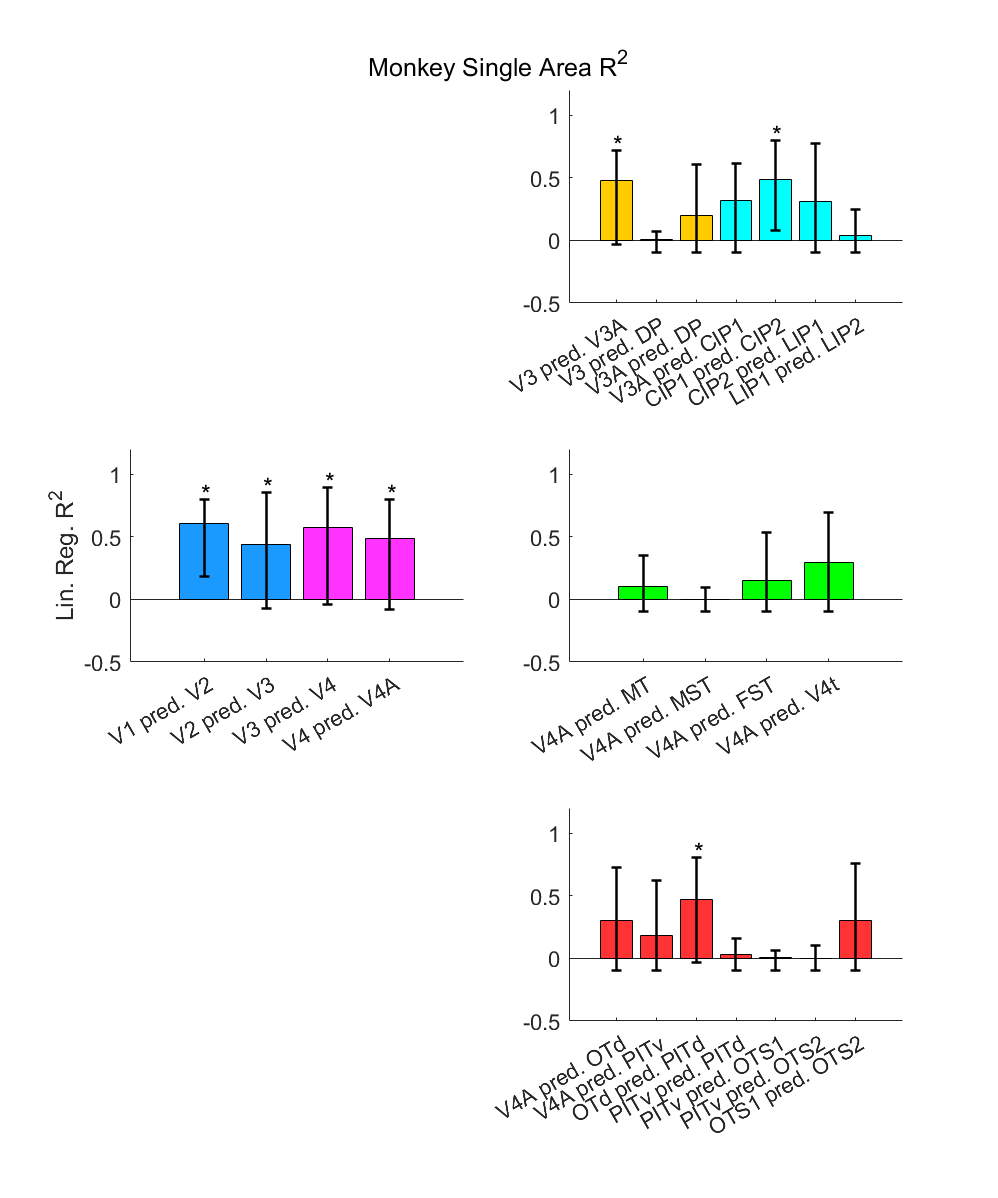

figure('Renderer', 'painters', 'Position', [10 10 1000 1200]);
s1 = subplot(3,2,3);
bar(1:2,vc_R2_monkey(1:2),'FaceColor',EVCcolor)
hold on;
bar(3:4,vc_R2_monkey(3:4),'FaceColor',V4color)
for i = 1:length(vc_p_monkey)
    errorbar(i,vc_R2_monkey(i),vc_R2_monkey(i)-vc_ci_monkey(i,1),vc_ci_monkey(i,2)-vc_R2_monkey(i),'k','LineWidth',1.5)
    if vc_p_monkey(i)<0.05
        text(i-0.05,vc_ci_monkey(i,2)+0.05,'*','FontSize',15)
    end
end
xticks(1:4)
xticklabels({'V1 pred. V2','V2 pred. V3','V3 pred. V4','V4 pred. V4A'})
ylabel('Lin. Reg. R^2')
ylim([-0.5 1.2])
s1.FontSize = 13;
xtickangle(30)
box off

s2 = subplot(3,2,2);
bar(1:3,dorsoparietal_R2_monkey(1:3),'FaceColor',dorsalcolor)
hold on;
bar(4:7,dorsoparietal_R2_monkey(4:7),'FaceColor',parietalcolor)
for i = 1:length(dorsoparietal_p_monkey)
    errorbar(i,dorsoparietal_R2_monkey(i),dorsoparietal_R2_monkey(i)-dorsoparietal_ci_monkey(i,1),dorsoparietal_ci_monkey(i,2)-dorsoparietal_R2_monkey(i),'k','LineWidth',1.5)
    if dorsoparietal_p_monkey(i)<0.05
        text(i-0.1,dorsoparietal_ci_monkey(i,2)+0.05,'*','FontSize',15)
    end
end
xticks(1:7)
xticklabels({'V3 pred. V3A','V3 pred. DP','V3A pred. DP','V3A pred. CIP1','CIP1 pred. CIP2','CIP2 pred. LIP1','LIP1 pred. LIP2'})
ylim([-0.5 1.2])
s2.FontSize = 13;
xtickangle(30)
box off

s3 = subplot(3,2,4);
bar(lateral_R2_monkey,'FaceColor',lateralcolor)
hold on;
for i = 1:length(lateral_p_monkey)
    errorbar(i,lateral_R2_monkey(i),lateral_R2_monkey(i)-lateral_ci_monkey(i,1),lateral_ci_monkey(i,2)-lateral_R2_monkey(i),'k','LineWidth',1.5)
    if lateral_p_monkey(i)<0.05
        text(i,lateral_ci_monkey(i,2)+0.05,'*','FontSize',15)
    end
end
xticklabels({'V4A pred. MT','V4A pred. MST','V4A pred. FST','V4A pred. V4t'})
ylim([-0.5 1.2])
s3.FontSize = 13;
xtickangle(30)
box off

s4 = subplot(3,2,6);
bar(ventral_R2_monkey,'FaceColor',ventralcolor)
hold on;
for i = 1:length(ventral_p_monkey)
    errorbar(i,ventral_R2_monkey(i),ventral_R2_monkey(i)-ventral_ci_monkey(i,1),ventral_ci_monkey(i,2)-ventral_R2_monkey(i),'k','LineWidth',1.5)
    if ventral_p_monkey(i)<0.05
        text(i-0.05,ventral_ci_monkey(i,2)+0.05,'*','FontSize',15)
    end
end
xticklabels({'V4A pred. OTd','V4A pred. PITv','OTd pred. PITd','PITv pred. PITd','PITv pred. OTS1','PITv pred. OTS2','OTS1 pred. OTS2'})
ylim([-0.5 1.2])
s4.FontSize = 13;
xtickangle(30)
box off

sgtitle('Monkey Single Area R^2')

addpath('Violinplot-Matlab')

human_blue = [0 0.4470 0.7410];
monkey_orange = [0.8500 0.3250 0.0980];

% all_R2_human = [vc_R2_human;ips_R2_human;lattemp_R2_human;ventral_R2_human];
all_corr_human = [vc_corr_human;ips_corr_human;lattemp_corr_human;ventral_corr_human];
within_group_human = [1;1;1;0;0;1;0;0;1;0;1;1;0;1;0;1;0;0;1;0;1];

p = ranksum(all_corr_human(within_group_human==1),all_corr_human(within_group_human==0));
disp(p)

    0.0151



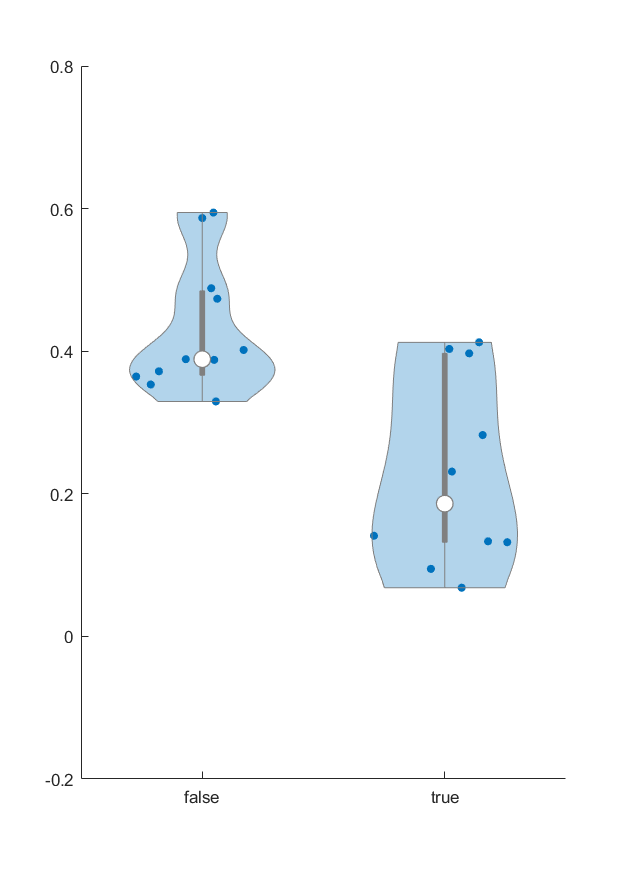


% both_groups = {all_R2_human(within_group==1),all_R2_human(within_group==0)};
% group_name = {'Within Group','Between Group'};

f = figure('Renderer', 'painters', 'Position', [10 10 500 700]);
viol1 = violinplot(all_corr_human,within_group_human==0,'ViolinColor',human_blue,'MedianMarkerSize',100);
box off;
ylim([-0.2 0.8])
yticks(-0.2:0.2:0.8)

% f.Children.XRuler.Axle.LineWidth = 2;
% f.Children.YRuler.Axle.LineWidth = 2;
% ax = gca;
% viol1.XRuler.Axle.LineWidth = 2;
% viol1.YRuler.Axle.LineWidth = 2;

all_corr_monkey = [vc_corr_monkey;dorsoparietal_corr_monkey;lateral_corr_monkey;ventral_corr_monkey];
within_group_monkey = [1;1;1;1;0;0;1;0;1;0;1;0;0;0;0;0;0;1;1;0;0;1];

p = ranksum(all_corr_monkey(within_group_monkey==1),all_corr_monkey(within_group_monkey==0));
disp(p)

    0.0321



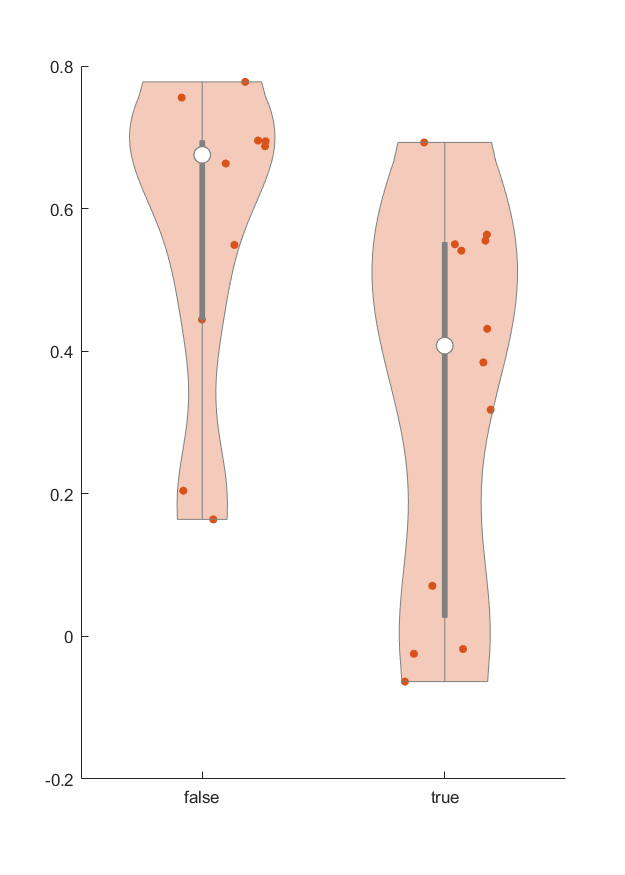


% both_groups = {all_R2_monkey(within_group==1),all_R2_monkey(within_group==0)};
% group_name = {'Within Group','Between Group'};

figure('Renderer', 'painters', 'Position', [10 10 500 700]);
violinplot(all_corr_monkey,within_group_monkey==0,'ViolinColor',monkey_orange,'MedianMarkerSize',100);
box off;
ylim([-0.2 0.8])
yticks(-0.2:0.2:0.8)

## MONKEY SINGLE AREA SPLIT VENTRAL/DORSAL

monkey_v1v_v2v_mdl = fitlm(v1v,v2v);
monkey_v1v_v2v_R2 = monkey_v1v_v2v_mdl.Rsquared.Ordinary;
monkey_v1v_v2v_p = anova(monkey_v1v_v2v_mdl,'summary').pValue('Model');
monkey_v1v_v2v_ci = bootci(1000,bootfun,v1v,v2v);

monkey_v1d_v2d_mdl = fitlm(v1d,v2d);
monkey_v1d_v2d_R2 = monkey_v1d_v2d_mdl.Rsquared.Ordinary;
monkey_v1d_v2d_p = anova(monkey_v1d_v2d_mdl,'summary').pValue('Model');
monkey_v1d_v2d_ci = bootci(1000,bootfun,v1d,v2d);

monkey_v2v_v3v_mdl = fitlm(v2v,v3v);
monkey_v2v_v3v_R2 = monkey_v2v_v3v_mdl.Rsquared.Ordinary;
monkey_v2v_v3v_p = anova(monkey_v2v_v3v_mdl,'summary').pValue('Model');
monkey_v2v_v3v_ci = bootci(1000,bootfun,v2v,v3v);

monkey_v2d_v3d_mdl = fitlm(v2d,v3d);
monkey_v2d_v3d_R2 = monkey_v2d_v3d_mdl.Rsquared.Ordinary;
monkey_v2d_v3d_p = anova(monkey_v2d_v3d_mdl,'summary').pValue('Model');
monkey_v2d_v3d_ci = bootci(1000,bootfun,v2d,v3d);

monkey_v3v_v4v_mdl = fitlm(v3v,v4v);
monkey_v3v_v4v_R2 = monkey_v3v_v4v_mdl.Rsquared.Ordinary;
monkey_v3v_v4v_p = anova(monkey_v3v_v4v_mdl,'summary').pValue('Model');
monkey_v3v_v4v_ci = bootci(1000,bootfun,v3v,v4v);

monkey_v3d_v4d_mdl = fitlm(v3d,v4d);
monkey_v3d_v4d_R2 = monkey_v3d_v4d_mdl.Rsquared.Ordinary;
monkey_v3d_v4d_p = anova(monkey_v3d_v4d_mdl,'summary').pValue('Model');
monkey_v3d_v4d_ci = bootci(1000,bootfun,v3d,v4d);

monkey_v3d_v3a_mdl = fitlm(v3d,v3a);
monkey_v3d_v3a_R2 = monkey_v3d_v3a_mdl.Rsquared.Ordinary;
monkey_v3d_v3a_p = anova(monkey_v3d_v3a_mdl,'summary').pValue('Model');
monkey_v3d_v3a_ci = bootci(1000,bootfun,v3d,v3a);

monkey_v3d_dp_mdl = fitlm(v3d,dp);
monkey_v3d_dp_R2 = monkey_v3d_dp_mdl.Rsquared.Ordinary;
monkey_v3d_dp_p = anova(monkey_v3d_dp_mdl,'summary').pValue('Model');
monkey_v3d_dp_ci = bootci(1000,bootfun,v3d,dp);

monkey_v4v_v4av_mdl = fitlm(v4v,v4av);
monkey_v4v_v4av_R2 = monkey_v4v_v4av_mdl.Rsquared.Ordinary;
monkey_v4v_v4av_p = anova(monkey_v4v_v4av_mdl,'summary').pValue('Model');
monkey_v4v_v4av_ci = bootci(1000,bootfun,v4v,v4av);

monkey_v4d_v4ad_mdl = fitlm(v4d,v4ad);
monkey_v4d_v4ad_R2 = monkey_v4d_v4ad_mdl.Rsquared.Ordinary;
monkey_v4d_v4ad_p = anova(monkey_v4d_v4ad_mdl,'summary').pValue('Model');
monkey_v4d_v4ad_ci = bootci(1000,bootfun,v4d,v4ad);

monkey_v4ad_mt_mdl = fitlm(v4ad,mt);
monkey_v4ad_mt_R2 = monkey_v4ad_mt_mdl.Rsquared.Ordinary;
monkey_v4ad_mt_p = anova(monkey_v4ad_mt_mdl,'summary').pValue('Model');
monkey_v4ad_mt_ci = bootci(1000,bootfun,v4ad,mt);

monkey_v4ad_mst_mdl = fitlm(v4ad,mst);
monkey_v4ad_mst_R2 = monkey_v4ad_mst_mdl.Rsquared.Ordinary;
monkey_v4ad_mst_p = anova(monkey_v4ad_mst_mdl,'summary').pValue('Model');
monkey_v4ad_mst_ci = bootci(1000,bootfun,v4ad,mst);

monkey_v4ad_fst_mdl = fitlm(v4ad,fst);
monkey_v4ad_fst_R2 = monkey_v4ad_fst_mdl.Rsquared.Ordinary;
monkey_v4ad_fst_p = anova(monkey_v4ad_fst_mdl,'summary').pValue('Model');
monkey_v4ad_fst_ci = bootci(1000,bootfun,v4ad,fst);

monkey_v4ad_v4t_mdl = fitlm(v4ad,v4t);
monkey_v4ad_v4t_R2 = monkey_v4ad_v4t_mdl.Rsquared.Ordinary;
monkey_v4ad_v4t_p = anova(monkey_v4ad_v4t_mdl,'summary').pValue('Model');
monkey_v4ad_v4t_ci = bootci(1000,bootfun,v4ad,v4t);

monkey_v4av_ot_mdl = fitlm(v4av,ot);
monkey_v4av_ot_R2 = monkey_v4av_ot_mdl.Rsquared.Ordinary;
monkey_v4av_ot_p = anova(monkey_v4av_ot_mdl,'summary').pValue('Model');
monkey_v4av_ot_ci = bootci(1000,bootfun,v4av,ot);

monkey_v4av_pitv_mdl = fitlm(v4av,pitv);
monkey_v4av_pitv_R2 = monkey_v4av_pitv_mdl.Rsquared.Ordinary;
monkey_v4av_pitv_p = anova(monkey_v4av_pitv_mdl,'summary').pValue('Model');
monkey_v4av_pitv_ci = bootci(1000,bootfun,v4av,pitv);

monkey_ot_pitd_mdl = fitlm(ot,pitd);
monkey_ot_pitd_R2 = monkey_ot_pitd_mdl.Rsquared.Ordinary;
monkey_ot_pitd_p = anova(monkey_ot_pitd_mdl,'summary').pValue('Model');
monkey_ot_pitd_ci = bootci(1000,bootfun,ot,pitd);

monkey_pitv_pitd_mdl = fitlm(pitv,pitd);
monkey_pitv_pitd_R2 = monkey_pitv_pitd_mdl.Rsquared.Ordinary;
monkey_pitv_pitd_p = anova(monkey_pitv_pitd_mdl,'summary').pValue('Model');
monkey_pitv_pitd_ci = bootci(1000,bootfun,pitv,pitd);

monkey_pitv_ots1_mdl = fitlm(pitv,ots1);
monkey_pitv_ots1_R2 = monkey_pitv_ots1_mdl.Rsquared.Ordinary;
monkey_pitv_ots1_p = anova(monkey_pitv_ots1_mdl,'summary').pValue('Model');
monkey_pitv_ots1_ci = bootci(1000,bootfun,pitv,ots1);

monkey_pitv_ots2_mdl = fitlm(pitv,ots2);
monkey_pitv_ots2_R2 = monkey_pitv_ots2_mdl.Rsquared.Ordinary;
monkey_pitv_ots2_p = anova(monkey_pitv_ots2_mdl,'summary').pValue('Model');
monkey_pitv_ots2_ci = bootci(1000,bootfun,pitv,ots2);

monkey_ots1_ots2_mdl = fitlm(ots1,ots2);
monkey_ots1_ots2_R2 = monkey_ots1_ots2_mdl.Rsquared.Ordinary;
monkey_ots1_ots2_p = anova(monkey_ots1_ots2_mdl,'summary').pValue('Model');
monkey_ots1_ots2_ci = bootci(1000,bootfun,ots1,ots2);

vc_R2_monkey_split_v = [monkey_v1v_v2v_R2;monkey_v2v_v3v_R2;monkey_v3v_v4v_R2;monkey_v4v_v4av_R2];
vc_p_monkey_split_v = [monkey_v1v_v2v_p;monkey_v2v_v3v_p;monkey_v3v_v4v_p;monkey_v4v_v4av_p];
vc_ci_monkey_split_v = [monkey_v1v_v2v_ci';monkey_v2v_v3v_ci';monkey_v3v_v4v_ci';monkey_v4v_v4av_ci'];
vc_R2_monkey_split_d = [monkey_v1d_v2d_R2;monkey_v2d_v3d_R2;monkey_v3d_v4d_R2;monkey_v4d_v4ad_R2];
vc_p_monkey_split_d = [monkey_v1d_v2d_p;monkey_v2d_v3d_p;monkey_v3d_v4d_p;monkey_v4d_v4ad_p];
vc_ci_monkey_split_d = [monkey_v1d_v2d_ci';monkey_v2d_v3d_ci';monkey_v3d_v4d_ci';monkey_v4d_v4ad_ci'];
dorsoparietal_R2_monkey_split = [monkey_v3d_v3a_R2;monkey_v3d_dp_R2];
dorsoparietal_p_monkey_split = [monkey_v3d_v3a_p;monkey_v3d_dp_p];
dorsoparietal_ci_monkey_split = [monkey_v3d_v3a_ci';monkey_v3d_dp_ci'];
lateral_R2_monkey_split = [monkey_v4ad_mt_R2;monkey_v4ad_mst_R2;monkey_v4ad_fst_R2;monkey_v4ad_v4t_R2];
lateral_p_monkey_split = [monkey_v4ad_mt_p;monkey_v4ad_mst_p;monkey_v4ad_fst_p;monkey_v4ad_v4t_p];
lateral_ci_monkey_split = [monkey_v4ad_mt_ci';monkey_v4ad_mst_ci';monkey_v4ad_fst_ci';monkey_v4ad_v4t_ci'];
ventral_R2_monkey_split = [monkey_v4av_ot_R2;monkey_v4av_pitv_R2];
ventral_p_monkey_split = [monkey_v4av_ot_p;monkey_v4av_pitv_p];
ventral_ci_monkey_split = [monkey_v4av_ot_ci';monkey_v4av_pitv_ci'];


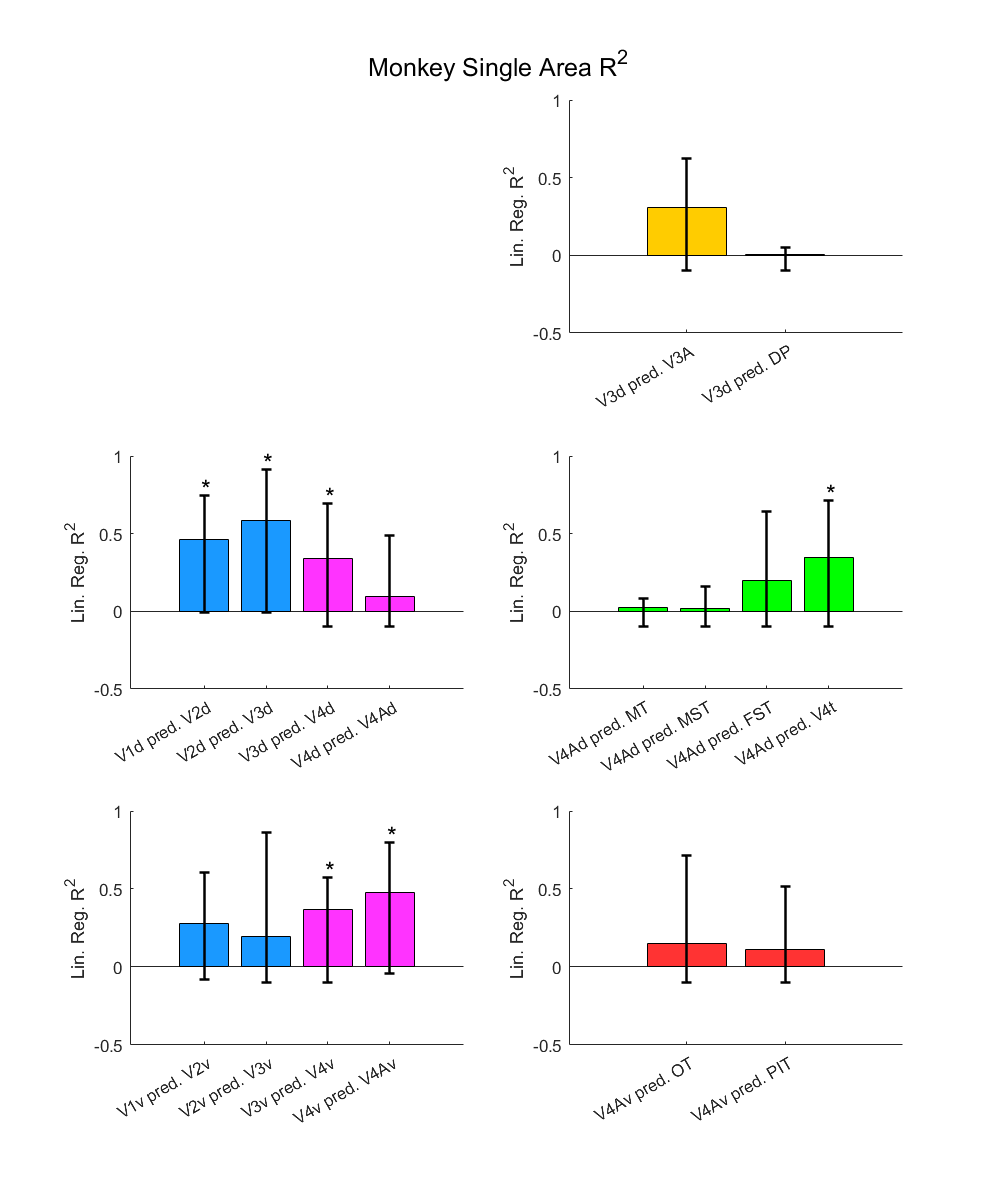

figure('Renderer', 'painters', 'Position', [10 10 1000 1200]);
subplot(3,2,3)
bar(1:2,vc_R2_monkey_split_d(1:2),'FaceColor',EVCcolor)
hold on;
bar(3:4,vc_R2_monkey_split_d(3:4),'FaceColor',V4color)
for i = 1:length(vc_p_monkey_split_d)
    errorbar(i,vc_R2_monkey_split_d(i),vc_R2_monkey_split_d(i)-vc_ci_monkey_split_d(i,1),vc_ci_monkey_split_d(i,2)-vc_R2_monkey_split_d(i),'k','LineWidth',1.5)
    if vc_p_monkey_split_d(i)<0.05
        text(i-0.05,vc_ci_monkey_split_d(i,2)+0.05,'*','FontSize',15)
    end
end
xticks(1:4)
xticklabels({'V1d pred. V2d','V2d pred. V3d','V3d pred. V4d','V4d pred. V4Ad'})
ylabel('Lin. Reg. R^2')
ylim([-0.5 1])
xtickangle(30)
box off

subplot(3,2,5)
bar(1:2,vc_R2_monkey_split_v(1:2),'FaceColor',EVCcolor)
hold on;
bar(3:4,vc_R2_monkey_split_v(3:4),'FaceColor',V4color)
for i = 1:length(vc_p_monkey_split_v)
    errorbar(i,vc_R2_monkey_split_v(i),vc_R2_monkey_split_v(i)-vc_ci_monkey_split_v(i,1),vc_ci_monkey_split_v(i,2)-vc_R2_monkey_split_v(i),'k','LineWidth',1.5)
    if vc_p_monkey_split_v(i)<0.05
        text(i-0.05,vc_ci_monkey_split_v(i,2)+0.05,'*','FontSize',15)
    end
end
xticks(1:4)
xticklabels({'V1v pred. V2v','V2v pred. V3v','V3v pred. V4v','V4v pred. V4Av'})
ylabel('Lin. Reg. R^2')
ylim([-0.5 1])
xtickangle(30)
box off

subplot(3,2,2)
hold on;
bar(1:2,dorsoparietal_R2_monkey_split,'FaceColor',dorsalcolor)
for i = 1:length(dorsoparietal_p_monkey_split)
    errorbar(i,dorsoparietal_R2_monkey_split(i),dorsoparietal_R2_monkey_split(i)-dorsoparietal_ci_monkey_split(i,1),dorsoparietal_ci_monkey_split(i,2)-dorsoparietal_R2_monkey_split(i),'k','LineWidth',1.5)
    if dorsoparietal_p_monkey_split(i)<0.05
        text(i-0.05,dorsoparietal_ci_monkey_split(i,2)+0.05,'*','FontSize',15)
    end
end
xticks(1:2)
xticklabels({'V3d pred. V3A','V3d pred. DP'})
ylabel('Lin. Reg. R^2')
ylim([-0.5 1])
xtickangle(30)
box off

subplot(3,2,4)
hold on;
bar(lateral_R2_monkey_split,'FaceColor',lateralcolor)
for i = 1:length(lateral_p_monkey_split)
    errorbar(i,lateral_R2_monkey_split(i),lateral_R2_monkey_split(i)-lateral_ci_monkey_split(i,1),lateral_ci_monkey_split(i,2)-lateral_R2_monkey_split(i),'k','LineWidth',1.5)
    if lateral_p_monkey_split(i)<0.05
        text(i-0.05,lateral_ci_monkey_split(i,2)+0.05,'*','FontSize',15)
    end
end
xticks(1:4)
xticklabels({'V4Ad pred. MT','V4Ad pred. MST','V4Ad pred. FST','V4Ad pred. V4t'})
ylabel('Lin. Reg. R^2')
ylim([-0.5 1])
xtickangle(30)
box off

subplot(3,2,6)
hold on;
bar(ventral_R2_monkey_split,'FaceColor',ventralcolor)
for i = 1:length(ventral_p_monkey_split)
    errorbar(i,ventral_R2_monkey_split(i),ventral_R2_monkey_split(i)-ventral_ci_monkey_split(i,1),ventral_ci_monkey_split(i,2)-ventral_R2_monkey_split(i),'k','LineWidth',1.5)
    if ventral_p_monkey_split(i)<0.05
        text(i-0.05,ventral_ci_monkey_split(i,2)+0.05,'*','FontSize',15)
    end
end
xticks(1:2)
xticklabels({'V4Av pred. OT','V4Av pred. PIT'})
ylabel('Lin. Reg. R^2')
ylim([-0.5 1])
xtickangle(30)
box off

sgtitle('Monkey Single Area R^2')

## MONKEY SINGLE AREAS REGRESS OUT HEMISPHERE SIZE

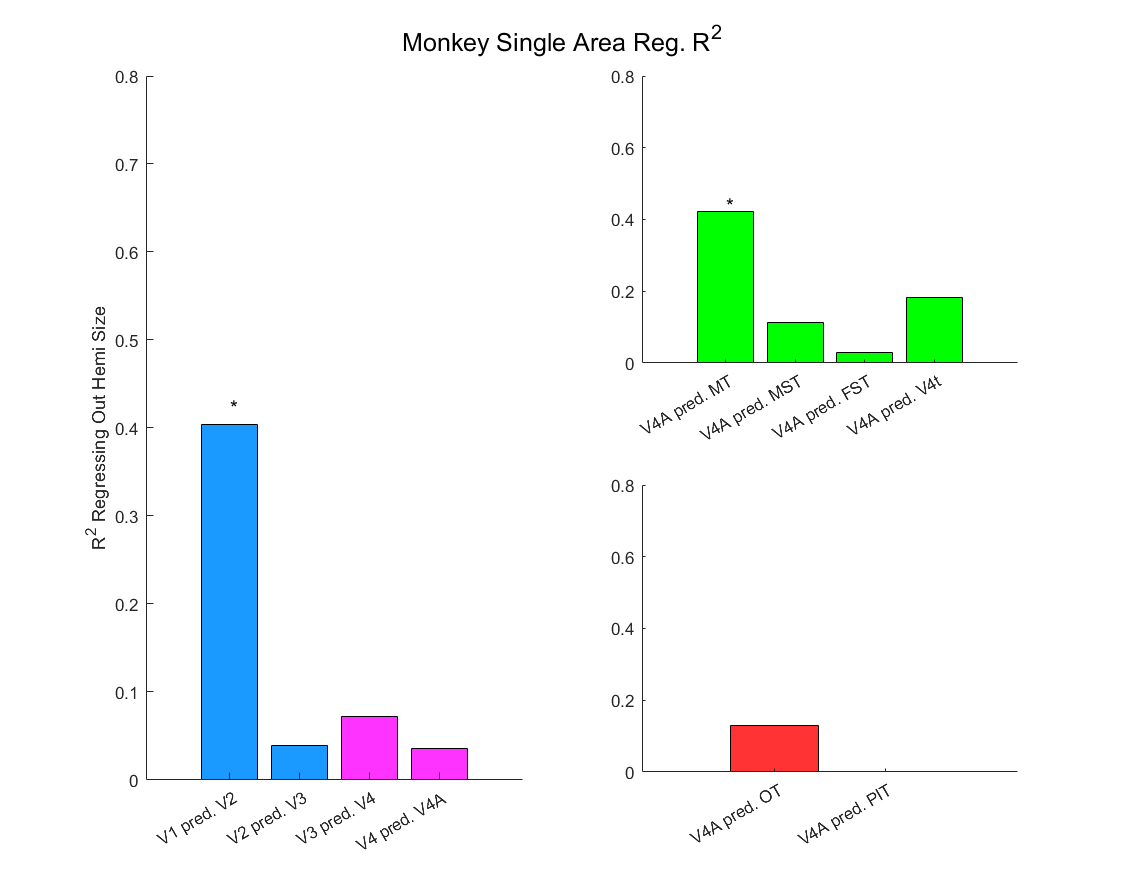

monkey_area_resid1 = fitlm(total_area_cat_monkey,v1);
monkey_area_resid2 = fitlm(total_area_cat_monkey,v2);
resid_1 = monkey_area_resid1.Residuals.Raw;
resid_2 = monkey_area_resid2.Residuals.Raw;
monkey_r1_r2_mdl = fitlm(resid_1,resid_2);
monkey_v1_v2_R2_resid = monkey_r1_r2_mdl.Rsquared.Ordinary;
monkey_v1_v2_p_resid = anova(monkey_r1_r2_mdl,'summary').pValue('Model');

monkey_area_resid1 = fitlm(total_area_cat_monkey,v2);
monkey_area_resid2 = fitlm(total_area_cat_monkey,v3);
resid_1 = monkey_area_resid1.Residuals.Standardized;
resid_2 = monkey_area_resid2.Residuals.Standardized;
monkey_r1_r2_mdl = fitlm(resid_1,resid_2);
monkey_v2_v3_R2_resid = monkey_r1_r2_mdl.Rsquared.Ordinary;
monkey_v2_v3_p_resid = anova(monkey_r1_r2_mdl,'summary').pValue('Model');

monkey_area_resid1 = fitlm(total_area_cat_monkey,v3);
monkey_area_resid2 = fitlm(total_area_cat_monkey,v4);
resid_1 = monkey_area_resid1.Residuals.Raw;
resid_2 = monkey_area_resid2.Residuals.Raw;
monkey_r1_r2_mdl = fitlm(resid_1,resid_2);
monkey_v3_v4_R2_resid = monkey_r1_r2_mdl.Rsquared.Ordinary;
monkey_v3_v4_p_resid = anova(monkey_r1_r2_mdl,'summary').pValue('Model');

monkey_area_resid1 = fitlm(total_area_cat_monkey,v4);
monkey_area_resid2 = fitlm(total_area_cat_monkey,v4a);
resid_1 = monkey_area_resid1.Residuals.Raw;
resid_2 = monkey_area_resid2.Residuals.Raw;
monkey_r1_r2_mdl = fitlm(resid_1,resid_2);
monkey_v4_v4a_R2_resid = monkey_r1_r2_mdl.Rsquared.Ordinary;
monkey_v4_v4a_p_resid = anova(monkey_r1_r2_mdl,'summary').pValue('Model');

monkey_area_resid1 = fitlm(total_area_cat_monkey,v4a);
monkey_area_resid2 = fitlm(total_area_cat_monkey,mt);
resid_1 = monkey_area_resid1.Residuals.Raw;
resid_2 = monkey_area_resid2.Residuals.Raw;
monkey_r1_r2_mdl = fitlm(resid_1,resid_2);
monkey_v4a_mt_R2_resid = monkey_r1_r2_mdl.Rsquared.Ordinary;
monkey_v4a_mt_p_resid = anova(monkey_r1_r2_mdl,'summary').pValue('Model');

monkey_area_resid1 = fitlm(total_area_cat_monkey,v4a);
monkey_area_resid2 = fitlm(total_area_cat_monkey,mst);
resid_1 = monkey_area_resid1.Residuals.Raw;
resid_2 = monkey_area_resid2.Residuals.Raw;
monkey_r1_r2_mdl = fitlm(resid_1,resid_2);
monkey_v4a_mst_R2_resid = monkey_r1_r2_mdl.Rsquared.Ordinary;
monkey_v4a_mst_p_resid = anova(monkey_r1_r2_mdl,'summary').pValue('Model');

monkey_area_resid1 = fitlm(total_area_cat_monkey,v4a);
monkey_area_resid2 = fitlm(total_area_cat_monkey,fst);
resid_1 = monkey_area_resid1.Residuals.Raw;
resid_2 = monkey_area_resid2.Residuals.Raw;
monkey_r1_r2_mdl = fitlm(resid_1,resid_2);
monkey_v4a_fst_R2_resid = monkey_r1_r2_mdl.Rsquared.Ordinary;
monkey_v4a_fst_p_resid = anova(monkey_r1_r2_mdl,'summary').pValue('Model');

monkey_area_resid1 = fitlm(total_area_cat_monkey,v4a);
monkey_area_resid2 = fitlm(total_area_cat_monkey,v4t);
resid_1 = monkey_area_resid1.Residuals.Raw;
resid_2 = monkey_area_resid2.Residuals.Raw;
monkey_r1_r2_mdl = fitlm(resid_1,resid_2);
monkey_v4a_v4t_R2_resid = monkey_r1_r2_mdl.Rsquared.Ordinary;
monkey_v4a_v4t_p_resid = anova(monkey_r1_r2_mdl,'summary').pValue('Model');

monkey_area_resid1 = fitlm(total_area_cat_monkey,v4a);
monkey_area_resid2 = fitlm(total_area_cat_monkey,ot);
resid_1 = monkey_area_resid1.Residuals.Raw;
resid_2 = monkey_area_resid2.Residuals.Raw;
monkey_r1_r2_mdl = fitlm(resid_1,resid_2);
monkey_v4a_ot_R2_resid = monkey_r1_r2_mdl.Rsquared.Ordinary;
monkey_v4a_ot_p_resid = anova(monkey_r1_r2_mdl,'summary').pValue('Model');

monkey_area_resid1 = fitlm(total_area_cat_monkey,v4a);
monkey_area_resid2 = fitlm(total_area_cat_monkey,pit);
resid_1 = monkey_area_resid1.Residuals.Raw;
resid_2 = monkey_area_resid2.Residuals.Raw;
monkey_r1_r2_mdl = fitlm(resid_1,resid_2);
monkey_v4a_pit_R2_resid = monkey_r1_r2_mdl.Rsquared.Ordinary;
monkey_v4a_pit_p_resid = anova(monkey_r1_r2_mdl,'summary').pValue('Model');

vc_R2_monkey = [monkey_v1_v2_R2_resid;monkey_v2_v3_R2_resid;monkey_v3_v4_R2_resid;monkey_v4_v4a_R2_resid];
vc_p_monkey = [monkey_v1_v2_p_resid;monkey_v2_v3_p_resid;monkey_v3_v4_p_resid;monkey_v4_v4a_p_resid];
lateral_R2_monkey = [monkey_v4a_mt_R2_resid;monkey_v4a_mst_R2_resid;monkey_v4a_fst_R2_resid;monkey_v4a_v4t_R2_resid];
lateral_p_monkey = [monkey_v4a_mt_p_resid;monkey_v4a_mst_p_resid;monkey_v4a_fst_p_resid;monkey_v4a_v4t_p_resid];
ventral_R2_monkey = [monkey_v4a_ot_R2_resid;monkey_v4a_pit_R2_resid];
ventral_p_monkey = [monkey_v4a_ot_p_resid;monkey_v4a_pit_p_resid];

figure('Renderer', 'painters', 'Position', [10 10 900 700]);
subplot(2,2,[1 3])
bar(1:2,vc_R2_monkey(1:2),'FaceColor',EVCcolor)
hold on;
bar(3:4,vc_R2_monkey(3:4),'FaceColor',V4color)
for i = 1:length(vc_p_monkey)
    if vc_p_monkey(i)<0.05
        text(i,vc_R2_monkey(i)+0.02,'*','FontSize',12)
    end
end
xticks(1:4)
xticklabels({'V1 pred. V2','V2 pred. V3','V3 pred. V4','V4 pred. V4A'})
ylabel('R^2 Regressing Out Hemi Size')
ylim([0 0.8])
xtickangle(30)
box off

subplot(2,2,2)
bar(lateral_R2_monkey,'FaceColor',lateralcolor)
for i = 1:length(lateral_p_monkey)
    if lateral_p_monkey(i)<0.05
        text(i,lateral_R2_monkey(i)+0.02,'*','FontSize',12)
    end
end
xticklabels({'V4A pred. MT','V4A pred. MST','V4A pred. FST','V4A pred. V4t'})
ylim([0 0.8])
xtickangle(30)
box off

subplot(2,2,4)
bar(ventral_R2_monkey,'FaceColor',ventralcolor)
for i = 1:length(ventral_p_monkey)
    if ventral_p_monkey(i)<0.05
        text(i,ventral_R2_monkey(i)+0.02,'*','FontSize',12)
    end
end
xticklabels({'V4A pred. OT','V4A pred. PIT'})
ylim([0 0.8])
xtickangle(30)
box off

sgtitle('Monkey Single Area Reg. R^2')

## MONKEY CUMULATIVE MODELS

monkey_v1v2_v3_mdl = fitlm(v1v2,v3);
monkey_v1v2_v3_R2 = monkey_v1v2_v3_mdl.Rsquared.Ordinary;
monkey_v1v2_v3_p = anova(monkey_v1v2_v3_mdl,'summary').pValue('Model');
monkey_v1v2_v3_ci = bootci(1000,bootfun,v1v2,v3);

monkey_v1v2v3_v4_mdl = fitlm(v1v2v3,v4);
monkey_v1v2v3_v4_R2 = monkey_v1v2v3_v4_mdl.Rsquared.Ordinary;
monkey_v1v2v3_v4_p = anova(monkey_v1v2v3_v4_mdl,'summary').pValue('Model');
monkey_v1v2v3_v4_ci = bootci(1000,bootfun,v1v2v3,v4);

monkey_v1v2v3v4_v4a_mdl = fitlm(v1v2v3v4,v4a');
monkey_v1v2v3v4_v4a_R2 = monkey_v1v2v3v4_v4a_mdl.Rsquared.Ordinary;
monkey_v1v2v3v4_v4a_p = anova(monkey_v1v2v3v4_v4a_mdl,'summary').pValue('Model');
monkey_v1v2v3v4_v4a_ci = bootci(1000,bootfun,v1v2v3v4,v4a);

w = warning('query','last');
id = w.identifier;
warning('off',id)

monkey_v1v2v3v4v4a_mt_mdl = fitlm(v1v2v3v4v4a,mt');
monkey_v1v2v3v4v4a_mt_R2 = monkey_v1v2v3v4v4a_mt_mdl.Rsquared.Ordinary;
monkey_v1v2v3v4v4a_mt_p = anova(monkey_v1v2v3v4v4a_mt_mdl,'summary').pValue('Model');
monkey_v1v2v3v4v4a_mt_ci = bootci(1000,bootfun,v1v2v3v4v4a,mt);

monkey_v1v2v3v4v4a_mst_mdl = fitlm(v1v2v3v4v4a,mst');
monkey_v1v2v3v4v4a_mst_R2 = monkey_v1v2v3v4v4a_mst_mdl.Rsquared.Ordinary;
monkey_v1v2v3v4v4a_mst_p = anova(monkey_v1v2v3v4v4a_mst_mdl,'summary').pValue('Model');
monkey_v1v2v3v4v4a_mst_ci = bootci(1000,bootfun,v1v2v3v4v4a,mst);

monkey_v1v2v3v4v4a_fst_mdl = fitlm(v1v2v3v4v4a,fst');
monkey_v1v2v3v4v4a_fst_R2 = monkey_v1v2v3v4v4a_fst_mdl.Rsquared.Ordinary;
monkey_v1v2v3v4v4a_fst_p = anova(monkey_v1v2v3v4v4a_fst_mdl,'summary').pValue('Model');
monkey_v1v2v3v4v4a_fst_ci = bootci(100,bootfun,v1v2v3v4v4a,fst');

monkey_v1v2v3v4v4a_v4t_mdl = fitlm(v1v2v3v4v4a,v4t');
monkey_v1v2v3v4v4a_v4t_R2 = monkey_v1v2v3v4v4a_v4t_mdl.Rsquared.Ordinary;
monkey_v1v2v3v4v4a_v4t_p = anova(monkey_v1v2v3v4v4a_v4t_mdl,'summary').pValue('Model');
monkey_v1v2v3v4v4a_v4t_ci = bootci(1000,bootfun,v1v2v3v4v4a,v4t);

monkey_v1v2v3v4v4a_ot_mdl = fitlm(v1v2v3v4v4a,ot');
monkey_v1v2v3v4v4a_ot_R2 = monkey_v1v2v3v4v4a_ot_mdl.Rsquared.Ordinary;
monkey_v1v2v3v4v4a_ot_p = anova(monkey_v1v2v3v4v4a_ot_mdl,'summary').pValue('Model');
monkey_v1v2v3v4v4a_ot_ci = bootci(1000,bootfun,v1v2v3v4v4a,ot);

monkey_v1v2v3v4v4a_pitv_mdl = fitlm(v1v2v3v4v4a,pitv');
monkey_v1v2v3v4v4a_pitv_R2 = monkey_v1v2v3v4v4a_pitv_mdl.Rsquared.Ordinary;
monkey_v1v2v3v4v4a_pitv_p = anova(monkey_v1v2v3v4v4a_pitv_mdl,'summary').pValue('Model');
monkey_v1v2v3v4v4a_pitv_ci = bootci(1000,bootfun,v1v2v3v4v4a,pitv);

monkey_v1v2v3v4v4a_pitd_mdl = fitlm(v1v2v3v4v4a,pitd');
monkey_v1v2v3v4v4a_pitd_R2 = monkey_v1v2v3v4v4a_pitd_mdl.Rsquared.Ordinary;
monkey_v1v2v3v4v4a_pitd_p = anova(monkey_v1v2v3v4v4a_pitd_mdl,'summary').pValue('Model');
monkey_v1v2v3v4v4a_pitd_ci = bootci(1000,bootfun,v1v2v3v4v4a,pitd);

monkey_v1v2v3v4v4a_ots1_mdl = fitlm(v1v2v3v4v4a,ots1');
monkey_v1v2v3v4v4a_ots1_R2 = monkey_v1v2v3v4v4a_ots1_mdl.Rsquared.Ordinary;
monkey_v1v2v3v4v4a_ots1_p = anova(monkey_v1v2v3v4v4a_ots1_mdl,'summary').pValue('Model');
monkey_v1v2v3v4v4a_ots1_ci = bootci(1000,bootfun,v1v2v3v4v4a,ots1);

monkey_v1v2v3v4v4a_ots2_mdl = fitlm(v1v2v3v4v4a,ots2');
monkey_v1v2v3v4v4a_ots2_R2 = monkey_v1v2v3v4v4a_ots2_mdl.Rsquared.Ordinary;
monkey_v1v2v3v4v4a_ots2_p = anova(monkey_v1v2v3v4v4a_ots2_mdl,'summary').pValue('Model');
monkey_v1v2v3v4v4a_ots2_ci = bootci(1000,bootfun,v1v2v3v4v4a,ots2);

monkey_v1v2v3v4v4a_v3a_mdl = fitlm(v1v2v3v4v4a,v3a');
monkey_v1v2v3v4v4a_v3a_R2 = monkey_v1v2v3v4v4a_v3a_mdl.Rsquared.Ordinary;
monkey_v1v2v3v4v4a_v3a_p = anova(monkey_v1v2v3v4v4a_v3a_mdl,'summary').pValue('Model');
monkey_v1v2v3v4v4a_v3a_ci = bootci(1000,bootfun,v1v2v3v4v4a,v3a);

monkey_v1v2v3v4v4a_dp_mdl = fitlm(v1v2v3v4v4a,dp');
monkey_v1v2v3v4v4a_dp_R2 = monkey_v1v2v3v4v4a_dp_mdl.Rsquared.Ordinary;
monkey_v1v2v3v4v4a_dp_p = anova(monkey_v1v2v3v4v4a_dp_mdl,'summary').pValue('Model');
monkey_v1v2v3v4v4a_dp_ci = bootci(1000,bootfun,v1v2v3v4v4a,dp);

monkey_v1v2v3v4v4a_cip1_mdl = fitlm(v1v2v3v4v4a,cip1);
monkey_v1v2v3v4v4a_cip1_R2 = monkey_v1v2v3v4v4a_cip1_mdl.Rsquared.Ordinary;
monkey_v1v2v3v4v4a_cip1_p = anova(monkey_v1v2v3v4v4a_cip1_mdl,'summary').pValue('Model');
monkey_v1v2v3v4v4a_cip1_ci = bootci(1000,bootfun,v1v2v3v4v4a,cip1);

monkey_v1v2v3v4v4a_cip2_mdl = fitlm(v1v2v3v4v4a,cip2);
monkey_v1v2v3v4v4a_cip2_R2 = monkey_v1v2v3v4v4a_cip2_mdl.Rsquared.Ordinary;
monkey_v1v2v3v4v4a_cip2_p = anova(monkey_v1v2v3v4v4a_cip2_mdl,'summary').pValue('Model');
monkey_v1v2v3v4v4a_cip2_ci = bootci(1000,bootfun,v1v2v3v4v4a,cip2);

monkey_v1v2v3v4v4a_lip1_mdl = fitlm(v1v2v3v4v4a,lip1);
monkey_v1v2v3v4v4a_lip1_R2 = monkey_v1v2v3v4v4a_lip1_mdl.Rsquared.Ordinary;
monkey_v1v2v3v4v4a_lip1_p = anova(monkey_v1v2v3v4v4a_lip1_mdl,'summary').pValue('Model');
monkey_v1v2v3v4v4a_lip1_ci = bootci(1000,bootfun,v1v2v3v4v4a,lip1);

monkey_v1v2v3v4v4a_lip2_mdl = fitlm(v1v2v3v4v4a,lip2);
monkey_v1v2v3v4v4a_lip2_R2 = monkey_v1v2v3v4v4a_lip2_mdl.Rsquared.Ordinary;
monkey_v1v2v3v4v4a_lip2_p = anova(monkey_v1v2v3v4v4a_lip2_mdl,'summary').pValue('Model');
monkey_v1v2v3v4v4a_lip2_ci = bootci(1000,bootfun,v1v2v3v4v4a,lip2);

monkey_v1v2v3v4v4a_lip3_mdl = fitlm(v1v2v3v4v4a,lip3);
monkey_v1v2v3v4v4a_lip3_R2 = monkey_v1v2v3v4v4a_lip3_mdl.Rsquared.Ordinary;
monkey_v1v2v3v4v4a_lip3_p = anova(monkey_v1v2v3v4v4a_lip3_mdl,'summary').pValue('Model');
monkey_v1v2v3v4v4a_lip3_ci = bootci(1000,bootfun,v1v2v3v4v4a,lip3);

vc_cumu_R2_monkey = [monkey_v1_v2_R2;monkey_v1v2_v3_R2;monkey_v1v2v3_v4_R2;monkey_v1v2v3v4_v4a_R2];
vc_cumu_p_monkey = [monkey_v1_v2_p;monkey_v1v2_v3_p;monkey_v1v2v3_v4_p;monkey_v1v2v3v4_v4a_p];
vc_cumu_ci_monkey = [monkey_v1_v2_ci';monkey_v1v2_v3_ci';monkey_v1v2v3_v4_ci';monkey_v1v2v3v4_v4a_ci'];
dorsoparietal_cumu_R2_monkey = [monkey_v1v2v3v4v4a_v3a_R2;monkey_v1v2v3v4v4a_dp_R2;monkey_v1v2v3v4v4a_cip1_R2;monkey_v1v2v3v4v4a_cip2_R2;monkey_v1v2v3v4v4a_lip1_R2;monkey_v1v2v3v4v4a_lip2_R2;monkey_v1v2v3v4v4a_lip3_R2];
dorsoparietal_cumu_p_monkey = [monkey_v1v2v3v4v4a_v3a_p;monkey_v1v2v3v4v4a_dp_p;monkey_v1v2v3v4v4a_cip1_p;monkey_v1v2v3v4v4a_cip2_p;monkey_v1v2v3v4v4a_lip1_p;monkey_v1v2v3v4v4a_lip2_p;monkey_v1v2v3v4v4a_lip3_p];
dorsoparietal_cumu_ci_monkey = [monkey_v1v2v3v4v4a_v3a_ci';monkey_v1v2v3v4v4a_dp_ci';monkey_v1v2v3v4v4a_cip1_ci';monkey_v1v2v3v4v4a_cip2_ci';monkey_v1v2v3v4v4a_lip1_ci';monkey_v1v2v3v4v4a_lip2_ci';monkey_v1v2v3v4v4a_lip3_ci'];
lateral_cumu_R2_monkey = [monkey_v1v2v3v4v4a_mt_R2;monkey_v1v2v3v4v4a_mst_R2;monkey_v1v2v3v4v4a_fst_R2;monkey_v1v2v3v4v4a_v4t_R2];
lateral_cumu_p_monkey = [monkey_v1v2v3v4v4a_mt_p;monkey_v1v2v3v4v4a_mst_p;monkey_v1v2v3v4v4a_fst_p;monkey_v1v2v3v4v4a_v4t_p];
lateral_cumu_ci_monkey = [monkey_v1v2v3v4v4a_mt_ci';monkey_v1v2v3v4v4a_mst_ci';monkey_v1v2v3v4v4a_fst_ci';monkey_v1v2v3v4v4a_v4t_ci'];
ventral_cumu_R2_monkey = [monkey_v1v2v3v4v4a_ot_R2;monkey_v1v2v3v4v4a_pitv_R2;monkey_v1v2v3v4v4a_pitd_R2;monkey_v1v2v3v4v4a_ots1_R2;monkey_v1v2v3v4v4a_ots2_R2];
ventral_cumu_p_monkey = [monkey_v1v2v3v4v4a_ot_p;monkey_v1v2v3v4v4a_pitv_p;monkey_v1v2v3v4v4a_pitd_p;monkey_v1v2v3v4v4a_ots1_p;monkey_v1v2v3v4v4a_ots2_p];
ventral_cumu_ci_monkey = [monkey_v1v2v3v4v4a_ot_ci';monkey_v1v2v3v4v4a_pitv_ci';monkey_v1v2v3v4v4a_pitd_ci';monkey_v1v2v3v4v4a_ots1_ci';monkey_v1v2v3v4v4a_ots2_ci'];


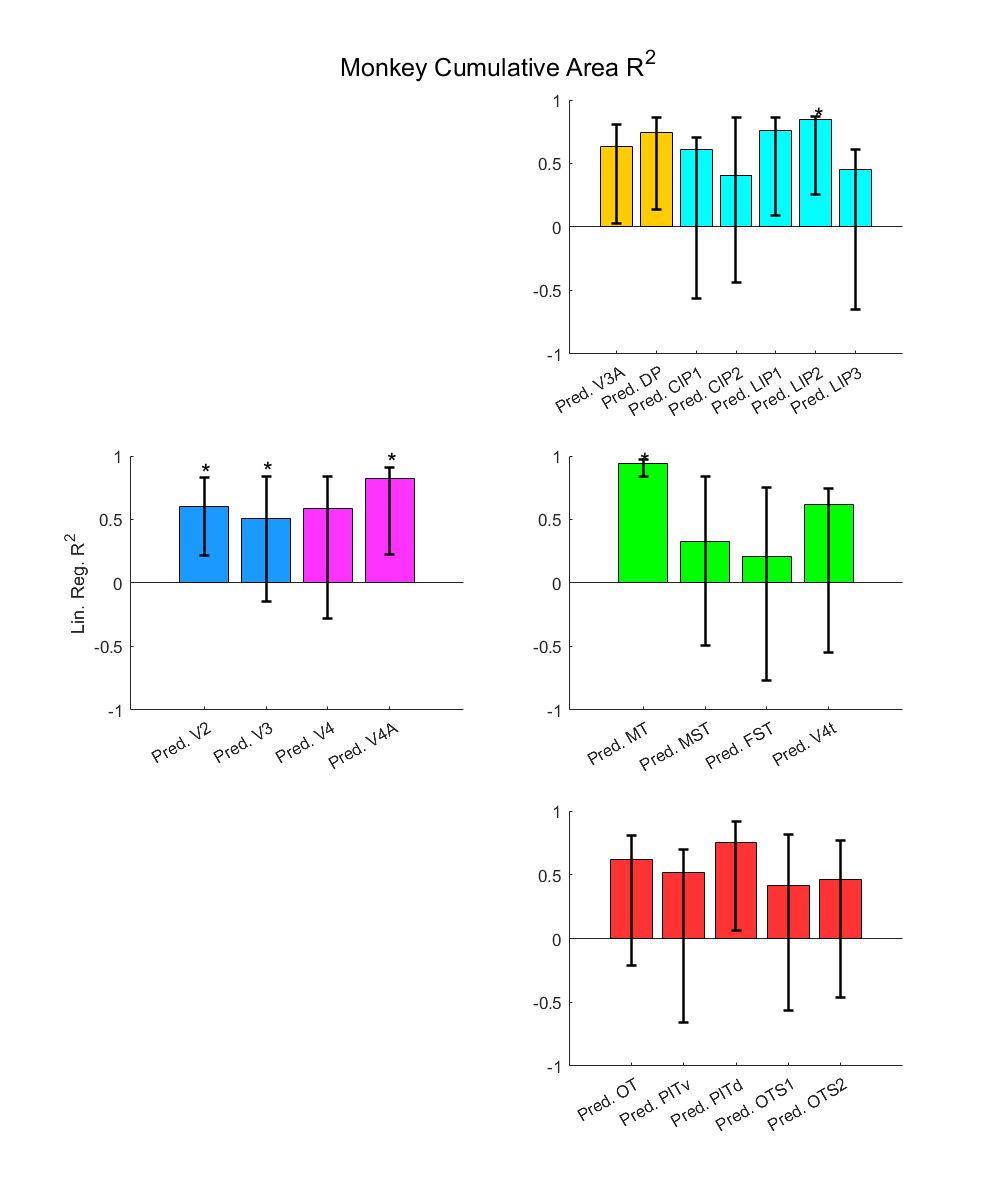

figure('Renderer', 'painters', 'Position', [10 10 1000 1200]);
subplot(3,2,3)
bar(1:2,vc_cumu_R2_monkey(1:2),'FaceColor',EVCcolor)
hold on;
bar(3:4,vc_cumu_R2_monkey(3:4),'FaceColor',V4color)
for i = 1:length(vc_cumu_p_monkey)
    errorbar(i,vc_cumu_R2_monkey(i),vc_cumu_R2_monkey(i)-vc_cumu_ci_monkey(i,1),vc_cumu_ci_monkey(i,2)-vc_cumu_R2_monkey(i),'k','LineWidth',1.5)
    if vc_cumu_p_monkey(i)<0.05
        text(i-0.05,vc_cumu_ci_monkey(i,2)+0.05,'*','FontSize',15)
    end
end
xticks(1:4)
xticklabels({'Pred. V2','Pred. V3','Pred. V4','Pred. V4A'})
ylabel('Lin. Reg. R^2')
ylim([-1 1])
box off

subplot(3,2,2)
bar(1:2,dorsoparietal_cumu_R2_monkey(1:2),'FaceColor',dorsalcolor)
hold on;
bar(3:7,dorsoparietal_cumu_R2_monkey(3:7),'FaceColor',parietalcolor)
for i = 1:length(dorsoparietal_cumu_p_monkey)
    errorbar(i,dorsoparietal_cumu_R2_monkey(i),dorsoparietal_cumu_R2_monkey(i)-dorsoparietal_cumu_ci_monkey(i,1),dorsoparietal_cumu_ci_monkey(i,2)-dorsoparietal_cumu_R2_monkey(i),'k','LineWidth',1.5)
    if dorsoparietal_cumu_p_monkey(i)<0.05
        text(i-0.05,dorsoparietal_cumu_ci_monkey(i,2)+0.05,'*','FontSize',15)
    end
end
xticks(1:7)
xticklabels({'Pred. V3A','Pred. DP','Pred. CIP1','Pred. CIP2','Pred. LIP1','Pred. LIP2','Pred. LIP3'})
ylim([-1 1])
box off

subplot(3,2,4)
hold on;
bar(lateral_cumu_R2_monkey,'FaceColor',lateralcolor)
for i = 1:length(lateral_cumu_p_monkey)
    errorbar(i,lateral_cumu_R2_monkey(i),lateral_cumu_R2_monkey(i)-lateral_cumu_ci_monkey(i,1),lateral_cumu_ci_monkey(i,2)-lateral_cumu_R2_monkey(i),'k','LineWidth',1.5)
    if lateral_cumu_p_monkey(i)<0.05
        text(i-0.05,lateral_cumu_ci_monkey(i,2)+0.05,'*','FontSize',15)
    end
end
xticks(1:4)
xticklabels({'Pred. MT','Pred. MST','Pred. FST','Pred. V4t'})
ylim([-1 1])
box off

subplot(3,2,6)
hold on;
bar(ventral_cumu_R2_monkey,'FaceColor',ventralcolor)
for i = 1:length(ventral_cumu_p_monkey)
    errorbar(i,ventral_cumu_R2_monkey(i),ventral_cumu_R2_monkey(i)-ventral_cumu_ci_monkey(i,1),ventral_cumu_ci_monkey(i,2)-ventral_cumu_R2_monkey(i),'k','LineWidth',1.5)
    if ventral_cumu_p_monkey(i)<0.05
        text(i-0.05,ventral_cumu_ci_monkey(i,2)+0.05,'*','FontSize',15)
    end
end
xticks(1:5)
xticklabels({'Pred. OT','Pred. PITv','Pred. PITd','Pred. OTS1','Pred. OTS2'})
ylim([-1 1])
box off
sgtitle('Monkey Cumulative Area R^2')

## Additional plots related to higher-order monkey areas

%*****NEEDS TO BE ADJUSTED BASED ON USING OCTAVIUS OR NOT, DOESN'T WORK RIGHT NOW*****

% figure('Renderer', 'painters', 'Position', [10 10 1000 300]);
% subplot(1,3,1)
% scatter(v4(1:7),v4a(1:7))
% hold on;
% scatter(v4(8:end),v4a(8:end))
% idx = ~isnan(v4) & ~isnan(v4a);
% coefficients = polyfit(v4(idx),v4a(idx), 1);
% xFit = linspace(50, 300, 1000);
% yFit = polyval(coefficients , xFit);
% plot(xFit,yFit,'k','linewidth',1.5)
% title(['r = ', num2str(corr2(v4(idx),v4a(idx)))])
% xlabel('V4 Size')
% ylabel('V4A Size')
% 
% subplot(1,3,2)
% scatter(v4a(1:7),mt(1:7))
% hold on;
% scatter(v4a(8:end),mt(8:end))
% idx = ~isnan(v4a) & ~isnan(mt);
% coefficients = polyfit(v4a(idx),mt(idx), 1);
% xFit = linspace(50, 150, 1000);
% yFit = polyval(coefficients , xFit);
% plot(xFit,yFit,'k','linewidth',1.5)
% title(['r = ', num2str(corr2(v4a(idx),mt(idx)))])
% xlabel('V4A Size')
% ylabel('MT Size')
% legend('Right Hemi','Left Hemi','Location','best')
% 
% subplot(1,3,3)
% % v4a_new = v4a(~isnan(v4a));
% scatter(v4a(1:6),v4a(7:end))
% hold on;
% v4a_rh = v4a(1:6);v4a_lh = v4a(7:end);
% idx = ~isnan(v4a_rh) & ~isnan(v4a_lh);
% coefficients = polyfit(v4a_rh(idx),v4a_lh(idx), 1);
% xFit = linspace(50, 150, 1000);
% yFit = polyval(coefficients , xFit);
% plot(xFit,yFit,'k','linewidth',1.5)
% title(['r = ', num2str(corr2(v4a_rh(idx),v4a_lh(idx)))])
% xlabel('V4A Right Hemi')
% ylabel('V4A Left Hemi')

% figure('Renderer', 'painters', 'Position', [10 10 1000 300]);
% subplot(1,3,1)
% % mt_new = mt(~isnan(mt));
% scatter(mt(1:6),mt(7:end))
% hold on;
% coefficients = polyfit(mt(1:6),mt(7:end), 1);
% xFit = linspace(50, 150, 1000);
% yFit = polyval(coefficients , xFit);
% plot(xFit,yFit,'k','linewidth',1.5)
% title(['r = ', num2str(corr2(mt(1:6),mt(7:end)))])
% xlim([50 150])
% ylim([50 150])
% xlabel('MT Right Hemi')
% ylabel('MT Left Hemi')
% 
% subplot(1,3,2)
% % mst_new = mst(~isnan(mst));
% scatter(mst(1:6),mst(7:end))
% hold on;
% coefficients = polyfit(mst(1:6),mst(7:end), 1);
% xFit = linspace(0, 100, 1000);
% yFit = polyval(coefficients , xFit);
% plot(xFit,yFit,'k','linewidth',1.5)
% title(['r = ', num2str(corr2(mst(1:6),mst(7:end)))])
% xlim([0 100])
% ylim([0 100])
% xlabel('MST Right Hemi')
% ylabel('MST Left Hemi')
% 
% subplot(1,3,3)
% scatter(mt(1:7),mst(1:7))
% hold on
% scatter(mt(8:end),mst(8:end))
% idx = ~isnan(mt) & ~isnan(mst);
% coefficients = polyfit(mt(idx),mst(idx), 1);
% xFit = linspace(0, 150, 1000);
% yFit = polyval(coefficients , xFit);
% plot(xFit,yFit,'k','linewidth',1.5)
% title(['r = ', num2str(corr2(mt(idx),mst(idx)))])
% xlim([50 150])
% ylim([0 100])
% xlabel('MT Size')
% ylabel('MST Size')
% legend('Right Hemi','Left Hemi','Location','best')


## HUMAN SINGLE MODELS - PLOT COEFFICIENTS

% HUMAN INDIVIDUAL MODELS
% p values refer to F-statistic of linear fit vs constant model

% vc
% human_v1_v2_mdl = fitlm(v1,v2);
% human_v1_v2_R2 = human_v1_v2_mdl.Coefficients.Estimate(2);
% human_v1_v2_p = human_v1_v2_mdl.Coefficients.pValue(2);
% 
% human_v1v_v2v_mdl = fitlm(v1v,v2v);
% human_v1v_v2v_R2 = human_v1v_v2v_mdl.Coefficients.Estimate(2);
% human_v1v_v2v_p = human_v1v_v2v_mdl.Coefficients.pValue(2);
% 
% human_v1d_v2d_mdl = fitlm(v1d,v2d);
% human_v1d_v2d_R2 = human_v1d_v2d_mdl.Coefficients.Estimate(2);
% human_v1d_v2d_p = human_v1d_v2d_mdl.Coefficients.pValue(2);
% 
% human_v2_v3_mdl = fitlm(v2,v3);
% human_v2_v3_R2 = human_v2_v3_mdl.Coefficients.Estimate(2);
% human_v2_v3_p = human_v2_v3_mdl.Coefficients.pValue(2);
% 
% human_v2v_v3v_mdl = fitlm(v2v,v3v);
% human_v2v_v3v_R2 = human_v2v_v3v_mdl.Coefficients.Estimate(2);
% human_v2v_v3v_p = human_v2v_v3v_mdl.Coefficients.pValue(2);
% 
% human_v2d_v3d_mdl = fitlm(v2d,v3d);
% human_v2d_v3d_R2 = human_v2d_v3d_mdl.Coefficients.Estimate(2);
% human_v2d_v3d_p = human_v2d_v3d_mdl.Coefficients.pValue(2);
% 
% % lat temp
% human_v3_lo1_mdl = fitlm(v3,lo1);
% human_v3_lo1_R2 = human_v3_lo1_mdl.Coefficients.Estimate(2);
% human_v3_lo1_p = human_v3_lo1_mdl.Coefficients.pValue(2);
% 
% human_v3d_lo1_mdl = fitlm(v3d,lo1);
% human_v3d_lo1_R2 = human_v3d_lo1_mdl.Coefficients.Estimate(2);
% human_v3d_lo1_p = human_v3d_lo1_mdl.Coefficients.pValue(2);
% 
% human_lo1_lo2_mdl = fitlm(lo1,lo2);
% human_lo1_lo2_R2 = human_lo1_lo2_mdl.Coefficients.Estimate(2);
% human_lo1_lo2_p = human_lo1_lo2_mdl.Coefficients.pValue(2);
% 
% human_lo2_to1_mdl = fitlm(lo2,to1);
% human_lo2_to1_R2 = human_lo2_to1_mdl.Coefficients.Estimate(2);
% human_lo2_to1_p = human_lo2_to1_mdl.Coefficients.pValue(2);
% 
% human_to1_to2_mdl = fitlm(to1,to2);
% human_to1_to2_R2 = human_to1_to2_mdl.Coefficients.Estimate(2);
% human_to1_to2_p = human_to1_to2_mdl.Coefficients.pValue(2);
% 
% % ips
% human_v3_v3a_mdl = fitlm(v3,v3a);
% human_v3_v3a_R2 = human_v3_v3a_mdl.Coefficients.Estimate(2);
% human_v3_v3a_p = human_v3_v3a_mdl.Coefficients.pValue(2);
% 
% human_v3d_v3a_mdl = fitlm(v3d,v3a);
% human_v3d_v3a_R2 = human_v3d_v3a_mdl.Coefficients.Estimate(2);
% human_v3d_v3a_p = human_v3d_v3a_mdl.Coefficients.pValue(2);
% 
% human_v3_v3b_mdl = fitlm(v3,v3b);
% human_v3_v3b_R2 = human_v3_v3b_mdl.Coefficients.Estimate(2);
% human_v3_v3b_p = human_v3_v3b_mdl.Coefficients.pValue(2);
% 
% human_v3d_v3b_mdl = fitlm(v3d,v3b);
% human_v3d_v3b_R2 = human_v3d_v3b_mdl.Coefficients.Estimate(2);
% human_v3d_v3b_p = human_v3d_v3b_mdl.Coefficients.pValue(2);
% 
% human_v3a_v3b_mdl = fitlm(v3a,v3b);
% human_v3a_v3b_R2 = human_v3a_v3b_mdl.Coefficients.Estimate(2);
% human_v3a_v3b_p = human_v3a_v3b_mdl.Coefficients.pValue(2);
% 
% human_v3a_ips0_mdl = fitlm(v3a,ips0);
% human_v3a_ips0_R2 = human_v3a_ips0_mdl.Coefficients.Estimate(2);
% human_v3a_ips0_p = human_v3a_ips0_mdl.Coefficients.pValue(2);
% 
% human_v3b_ips0_mdl = fitlm(v3b,ips0);
% human_v3b_ips0_R2 = human_v3b_ips0_mdl.Coefficients.Estimate(2);
% human_v3b_ips0_p = human_v3b_ips0_mdl.Coefficients.pValue(2);
% 
% % ventral
% human_v3_v4_mdl = fitlm(v3,v4);
% human_v3_v4_R2 = human_v3_v4_mdl.Coefficients.Estimate(2);
% human_v3_v4_p = human_v3_v4_mdl.Coefficients.pValue(2);
% 
% human_v3v_v4_mdl = fitlm(v3v,v4);
% human_v3v_v4_R2 = human_v3v_v4_mdl.Coefficients.Estimate(2);
% human_v3v_v4_p = human_v3v_v4_mdl.Coefficients.pValue(2);
% 
% human_v3_vo1_mdl = fitlm(v3,vo1);
% human_v3_vo1_R2 = human_v3_vo1_mdl.Coefficients.Estimate(2);
% human_v3_vo1_p = human_v3_vo1_mdl.Coefficients.pValue(2);
% 
% human_v3v_vo1_mdl = fitlm(v3v,vo1);
% human_v3v_vo1_R2 = human_v3v_vo1_mdl.Coefficients.Estimate(2);
% human_v3v_vo1_p = human_v3v_vo1_mdl.Coefficients.pValue(2);
% 
% human_v4_vo1_mdl = fitlm(v4,vo1);
% human_v4_vo1_R2 = human_v4_vo1_mdl.Coefficients.Estimate(2);
% human_v4_vo1_p = human_v4_vo1_mdl.Coefficients.pValue(2);
% 
% human_vo1_vo2_mdl = fitlm(vo1,vo2);
% human_vo1_vo2_R2 = human_vo1_vo2_mdl.Coefficients.Estimate(2);
% human_vo1_vo2_p = human_vo1_vo2_mdl.Coefficients.pValue(2);
% 
% human_vo2_phc1_mdl = fitlm(vo2,phc1);
% human_vo2_phc1_R2 = human_vo2_phc1_mdl.Coefficients.Estimate(2);
% human_vo2_phc1_p = human_vo2_phc1_mdl.Coefficients.pValue(2);
% 
% human_phc1_phc2_mdl = fitlm(phc1,phc2);
% human_phc1_phc2_R2 = human_phc1_phc2_mdl.Coefficients.Estimate(2);
% human_phc1_phc2_p = human_phc1_phc2_mdl.Coefficients.pValue(2);
% 
% vc_R2_human = [human_v1_v2_R2;human_v2_v3_R2];
% vc_p_human = [human_v1_v2_p;human_v2_v3_p];
% lattemp_R2_human = [human_v3_lo1_R2;human_lo1_lo2_R2;human_lo2_to1_R2;human_to1_to2_R2];
% lattemp_p_human = [human_v3_lo1_p;human_lo1_lo2_p;human_lo2_to1_p;human_to1_to2_p];
% ips_R2_human = [human_v3_v3a_R2;human_v3_v3b_R2;human_v3a_v3b_R2;human_v3a_ips0_R2;human_v3b_ips0_R2];
% ips_p_human = [human_v3_v3a_p;human_v3_v3b_p;human_v3a_v3b_p;human_v3a_ips0_p;human_v3b_ips0_p];
% ventral_R2_human = [human_v3_v4_R2;human_v3_vo1_R2;human_v4_vo1_R2;human_vo1_vo2_R2;human_vo2_phc1_R2;human_phc1_phc2_R2];
% ventral_p_human = [human_v3_v4_p;human_v3_vo1_p;human_v4_vo1_p;human_vo1_vo2_p;human_vo2_phc1_p;human_phc1_phc2_p];
% 
% vc_R2_human_split_v = [human_v1v_v2v_R2;human_v2v_v3v_R2];
% vc_p_human_split_v = [human_v1v_v2v_p;human_v2v_v3v_p];
% vc_R2_human_split_d = [human_v1d_v2d_R2;human_v2d_v3d_R2];
% vc_p_human_split_d = [human_v1d_v2d_p;human_v2d_v3d_p];
% lattemp_R2_human_split = [human_v3d_lo1_R2;human_lo1_lo2_R2;human_lo2_to1_R2;human_to1_to2_R2];
% lattemp_p_human_split = [human_v3d_lo1_p;human_lo1_lo2_p;human_lo2_to1_p;human_to1_to2_p];
% ips_R2_human_split = [human_v3d_v3a_R2;human_v3d_v3b_R2;human_v3a_v3b_R2;human_v3a_ips0_R2;human_v3b_ips0_R2];
% ips_p_human_split = [human_v3d_v3a_p;human_v3d_v3b_p;human_v3a_v3b_p;human_v3a_ips0_p;human_v3b_ips0_p];
% ventral_R2_human_split = [human_v3v_v4_R2;human_v3v_vo1_R2;human_v4_vo1_R2;human_vo1_vo2_R2;human_vo2_phc1_R2;human_phc1_phc2_R2];
% ventral_p_human_split = [human_v3v_v4_p;human_v3v_vo1_p;human_v4_vo1_p;human_vo1_vo2_p;human_vo2_phc1_p;human_phc1_phc2_p];
% 
% 
% f = figure('Renderer', 'painters', 'Position', [10 10 900 1000]);
% subplot(3,2,3)
% bar(vc_R2_human)
% for i = 1:length(vc_p_human)
%     if vc_p_human(i)<0.05
%         text(i,vc_R2_human(i)+0.02,'*','FontSize',12)
%     end
% end
% xticklabels({'V1 pred. V2','V2 pred. V3'})
% xtickangle(30)
% ylabel('Lin. Reg. Coeff')
% ylim([0 1])
% box off
% 
% subplot(3,2,2)
% bar(lattemp_R2_human)
% for i = 1:length(lattemp_p_human)
%     if lattemp_p_human(i)<0.05
%         text(i,lattemp_R2_human(i)+0.02,'*','FontSize',12)
%     end
% end
% xticklabels({'V3 pred. LO1','LO1 pred. LO2','LO2 pred. TO1','TO1 pred. TO2'})
% xtickangle(30)
% ylim([0 1])
% box off
% 
% subplot(3,2,4)
% bar(ips_R2_human)
% for i = 1:length(ips_p_human)
%     if ips_p_human(i)<0.05
%         text(i,ips_R2_human(i)+0.02,'*','FontSize',12)
%     end
% end
% xticklabels({'V3 pred. V3A','V3 pred. V3B','V3A pred. V3B','V3A pred. IPS0','V3B pred. IPS0'})
% ylim([0 1])
% xtickangle(30)
% box off
% sgtitle('Human Single Area R^2')
% 
% subplot(3,2,6)
% bar(ventral_R2_human)
% for i = 1:length(ventral_p_human)
%     if ventral_p_human(i)<0.05
%         text(i,ventral_R2_human(i)+0.02,'*','FontSize',12)
%     end
% end
% xticklabels({'V3 pred. V4','V3 pred. VO1','V4 pred. VO1','VO1 pred. VO2','VO2 pred. PHC1','PHC1 pred. PHC2'})
% xtickangle(30)
% ylim([0 1])
% box off
% sgtitle('Human Single Area R^2')

% f = figure('Renderer', 'painters', 'Position', [10 10 900 1000]);
% hold on;
% subplot(3,2,3)
% bar(vc_R2_human_split_v)
% for i = 1:length(vc_p_human_split_v)
%     if vc_p_human_split_v(i)<0.05
%         text(i,vc_R2_human_split_v(i)+0.02,'*','FontSize',12)
%     end
% end
% xticklabels({'V1d pred. V2d','V2d pred. V3d'})
% xtickangle(30)
% ylabel('Lin. Reg. Coeff')
% ylim([0 1])
% box off
% 
% subplot(3,2,5)
% bar(vc_R2_human_split_d)
% for i = 1:length(vc_p_human_split_d)
%     if vc_p_human_split_d(i)<0.05
%         text(i,vc_R2_human_split_d(i)+0.02,'*','FontSize',12)
%     end
% end
% xticklabels({'V1v pred. V2v','V2v pred. V3v'})
% ylabel('Lin. Reg. Coeff')
% xtickangle(30)
% ylim([0 1])
% box off
% 
% subplot(3,2,2)
% bar(lattemp_R2_human_split)
% for i = 1:length(lattemp_p_human_split)
%     if lattemp_p_human_split(i)<0.05
%         text(i,lattemp_R2_human_split(i)+0.02,'*','FontSize',12)
%     end
% end
% xticklabels({'V3d pred. LO1','LO1 pred. LO2','LO2 pred. TO1','TO1 pred. TO2'})
% xtickangle(30)
% ylim([0 1])
% box off
% 
% subplot(3,2,4)
% bar(ips_R2_human_split)
% for i = 1:length(ips_p_human_split)
%     if ips_p_human_split(i)<0.05
%         text(i,ips_R2_human_split(i)+0.02,'*','FontSize',12)
%     end
% end
% xticklabels({'V3d pred. V3A','V3d pred. V3B','V3A pred. V3B','V3A pred. IPS0','V3B pred. IPS0'})
% ylim([0 1])
% xtickangle(30)
% box off
% sgtitle('Human Single Area R^2')
% 
% subplot(3,2,6)
% bar(ventral_R2_human_split)
% for i = 1:length(ventral_p_human_split)
%     if ventral_p_human_split(i)<0.05
%         text(i,ventral_R2_human_split(i)+0.02,'*','FontSize',12)
%     end
% end
% xticklabels({'V3v pred. V4','V3v pred. VO1','V4 pred. VO1','VO1 pred. VO2','VO2 pred. PHC1','PHC1 pred. PHC2'})
% xtickangle(30)
% ylim([0 1])
% box off
% sgtitle('Human Single Area R^2')

% vc
% human_v1_v2_mdl = fitlm([v1;total_area_cat_human]',v2);
% human_v1_v2_R2 = human_v1_v2_mdl.Coefficients.Estimate(2);
% human_v1_v2_p = human_v1_v2_mdl.Coefficients.pValue(2);
% 
% human_v1v_v2v_mdl = fitlm([v1v;total_area_cat_human]',v2v);
% human_v1v_v2v_R2 = human_v1v_v2v_mdl.Coefficients.Estimate(2);
% human_v1v_v2v_p = human_v1v_v2v_mdl.Coefficients.pValue(2);
% 
% human_v1d_v2d_mdl = fitlm([v1d;total_area_cat_human]',v2d);
% human_v1d_v2d_R2 = human_v1d_v2d_mdl.Coefficients.Estimate(2);
% human_v1d_v2d_p = human_v1d_v2d_mdl.Coefficients.pValue(2);
% 
% human_v2_v3_mdl = fitlm([v2;total_area_cat_human]',v3);
% human_v2_v3_R2 = human_v2_v3_mdl.Coefficients.Estimate(2);
% human_v2_v3_p = human_v2_v3_mdl.Coefficients.pValue(2);
% 
% human_v2v_v3v_mdl = fitlm([v2v;total_area_cat_human]',v3v);
% human_v2v_v3v_R2 = human_v2v_v3v_mdl.Coefficients.Estimate(2);
% human_v2v_v3v_p = human_v2v_v3v_mdl.Coefficients.pValue(2);
% 
% human_v2d_v3d_mdl = fitlm([v2d;total_area_cat_human]',v3d);
% human_v2d_v3d_R2 = human_v2d_v3d_mdl.Coefficients.Estimate(2);
% human_v2d_v3d_p = human_v2d_v3d_mdl.Coefficients.pValue(2);

% lat temp
% human_v3_lo1_mdl = fitlm([v3;total_area_cat_human]',lo1);
% human_v3_lo1_R2 = human_v3_lo1_mdl.Coefficients.Estimate(2);
% human_v3_lo1_p = human_v3_lo1_mdl.Coefficients.pValue(2);
% 
% human_v3d_lo1_mdl = fitlm([v3d;total_area_cat_human]',lo1);
% human_v3d_lo1_R2 = human_v3d_lo1_mdl.Coefficients.Estimate(2);
% human_v3d_lo1_p = human_v3d_lo1_mdl.Coefficients.pValue(2);

% human_lo1_lo2_mdl = fitlm([lo1;total_area_cat_human]',lo2);
% human_lo1_lo2_R2 = human_lo1_lo2_mdl.Coefficients.Estimate(2);
% human_lo1_lo2_p = human_lo1_lo2_mdl.Coefficients.pValue(2);

% human_lo2_to1_mdl = fitlm([lo2;total_area_cat_human]',to1);
% human_lo2_to1_R2 = human_lo2_to1_mdl.Coefficients.Estimate(2);
% human_lo2_to1_p = human_lo2_to1_mdl.Coefficients.pValue(2);
% 
% human_to1_to2_mdl = fitlm([to1;total_area_cat_human]',to2);
% human_to1_to2_R2 = human_to1_to2_mdl.Coefficients.Estimate(2);
% human_to1_to2_p = human_to1_to2_mdl.Coefficients.pValue(2);

% ips
% human_v3_v3a_mdl = fitlm([v3;total_area_cat_human]',v3a);
% human_v3_v3a_R2 = human_v3_v3a_mdl.Coefficients.Estimate(2);
% human_v3_v3a_p = human_v3_v3a_mdl.Coefficients.pValue(2);
% 
% human_v3d_v3a_mdl = fitlm([v3d;total_area_cat_human]',v3a);
% human_v3d_v3a_R2 = human_v3d_v3a_mdl.Coefficients.Estimate(2);
% human_v3d_v3a_p = human_v3d_v3a_mdl.Coefficients.pValue(2);

% human_v3_v3b_mdl = fitlm([v3;total_area_cat_human]',v3b);
% human_v3_v3b_R2 = human_v3_v3b_mdl.Coefficients.Estimate(2);
% human_v3_v3b_p = human_v3_v3b_mdl.Coefficients.pValue(2);
% 
% human_v3d_v3b_mdl = fitlm([v3d;total_area_cat_human]',v3b);
% human_v3d_v3b_R2 = human_v3d_v3b_mdl.Coefficients.Estimate(2);
% human_v3d_v3b_p = human_v3d_v3b_mdl.Coefficients.pValue(2);
% 
% human_v3a_v3b_mdl = fitlm([v3a;total_area_cat_human]',v3b);
% human_v3a_v3b_R2 = human_v3a_v3b_mdl.Coefficients.Estimate(2);
% human_v3a_v3b_p = human_v3a_v3b_mdl.Coefficients.pValue(2);

% human_v3a_ips0_mdl = fitlm([v3a;total_area_cat_human]',ips0);
% human_v3a_ips0_R2 = human_v3a_ips0_mdl.Coefficients.Estimate(2);
% human_v3a_ips0_p = human_v3a_ips0_mdl.Coefficients.pValue(2);
% 
% human_v3b_ips0_mdl = fitlm([v3b;total_area_cat_human]',ips0);
% human_v3b_ips0_R2 = human_v3b_ips0_mdl.Coefficients.Estimate(2);
% human_v3b_ips0_p = human_v3b_ips0_mdl.Coefficients.pValue(2);

% ventral
% human_v3_v4_mdl = fitlm([v3;total_area_cat_human]',v4);
% human_v3_v4_R2 = human_v3_v4_mdl.Coefficients.Estimate(2);
% human_v3_v4_p = human_v3_v4_mdl.Coefficients.pValue(2);
% 
% human_v3v_v4_mdl = fitlm([v3v;total_area_cat_human]',v4);
% human_v3v_v4_R2 = human_v3v_v4_mdl.Coefficients.Estimate(2);
% human_v3v_v4_p = human_v3v_v4_mdl.Coefficients.pValue(2);

% human_v3_vo1_mdl = fitlm([v3;total_area_cat_human]',vo1);
% human_v3_vo1_R2 = human_v3_vo1_mdl.Coefficients.Estimate(2);
% human_v3_vo1_p = human_v3_vo1_mdl.Coefficients.pValue(2);
% 
% human_v3v_vo1_mdl = fitlm([v3v;total_area_cat_human]',vo1);
% human_v3v_vo1_R2 = human_v3v_vo1_mdl.Coefficients.Estimate(2);
% human_v3v_vo1_p = human_v3v_vo1_mdl.Coefficients.pValue(2);

% human_v4_vo1_mdl = fitlm([v4;total_area_cat_human]',vo1);
% human_v4_vo1_R2 = human_v4_vo1_mdl.Coefficients.Estimate(2);
% human_v4_vo1_p = human_v4_vo1_mdl.Coefficients.pValue(2);

% human_vo1_vo2_mdl = fitlm([vo1;total_area_cat_human]',vo2);
% human_vo1_vo2_R2 = human_vo1_vo2_mdl.Coefficients.Estimate(2);
% human_vo1_vo2_p = human_vo1_vo2_mdl.Coefficients.pValue(2);
% 
% human_vo2_phc1_mdl = fitlm([vo2;total_area_cat_human]',phc1);
% human_vo2_phc1_R2 = human_vo2_phc1_mdl.Coefficients.Estimate(2);
% human_vo2_phc1_p = human_vo2_phc1_mdl.Coefficients.pValue(2);
% 
% human_phc1_phc2_mdl = fitlm([phc1;total_area_cat_human]',phc2);
% human_phc1_phc2_R2 = human_phc1_phc2_mdl.Coefficients.Estimate(2);
% human_phc1_phc2_p = human_phc1_phc2_mdl.Coefficients.pValue(2);

% vc_R2_human_split_v = [human_v1v_v2v_R2;human_v2v_v3v_R2];
% vc_p_human_split_v = [human_v1v_v2v_p;human_v2v_v3v_p];
% vc_R2_human_split_d = [human_v1d_v2d_R2;human_v2d_v3d_R2];
% vc_p_human_split_d = [human_v1d_v2d_p;human_v2d_v3d_p];
% lattemp_R2_human_split = [human_v3d_lo1_R2;human_lo1_lo2_R2;human_lo2_to1_R2;human_to1_to2_R2];
% lattemp_p_human_split = [human_v3d_lo1_p;human_lo1_lo2_p;human_lo2_to1_p;human_to1_to2_p];
% ips_R2_human_split = [human_v3d_v3a_R2;human_v3d_v3b_R2;human_v3a_v3b_R2;human_v3a_ips0_R2;human_v3b_ips0_R2];
% ips_p_human_split = [human_v3d_v3a_p;human_v3d_v3b_p;human_v3a_v3b_p;human_v3a_ips0_p;human_v3b_ips0_p];
% ventral_R2_human_split = [human_v3v_v4_R2;human_v3v_vo1_R2;human_v4_vo1_R2;human_vo1_vo2_R2;human_vo2_phc1_R2;human_phc1_phc2_R2];
% ventral_p_human_split = [human_v3v_v4_p;human_v3v_vo1_p;human_v4_vo1_p;human_vo1_vo2_p;human_vo2_phc1_p;human_phc1_phc2_p];

% f = figure('Renderer', 'painters', 'Position', [10 10 900 1000]);
% hold on;
% subplot(3,2,3)
% bar(vc_R2_human_split_v)
% for i = 1:length(vc_p_human_split_v)
%     if vc_p_human_split_v(i)<0.05
%         text(i,vc_R2_human_split_v(i)+0.02,'*','FontSize',12)
%     end
% end
% xticklabels({'V1d pred. V2d','V2d pred. V3d'})
% xtickangle(30)
% ylim([0 1])
% box off
% 
% subplot(3,2,5)
% bar(vc_R2_human_split_d)
% for i = 1:length(vc_p_human_split_d)
%     if vc_p_human_split_d(i)<0.05
%         text(i,vc_R2_human_split_d(i)+0.02,'*','FontSize',12)
%     end
% end
% xticklabels({'V1v pred. V2v','V2v pred. V3v'})
% ylabel('Lin. Reg. Coeff Accounting for Hemi Size')
% xtickangle(30)
% ylim([0 1])
% box off
% 
% subplot(3,2,2)
% bar(lattemp_R2_human_split)
% for i = 1:length(lattemp_p_human_split)
%     if lattemp_p_human_split(i)<0.05
%         text(i,lattemp_R2_human_split(i)+0.02,'*','FontSize',12)
%     end
% end
% xticklabels({'V3d pred. LO1','LO1 pred. LO2','LO2 pred. TO1','TO1 pred. TO2'})
% xtickangle(30)
% ylim([0 1])
% box off
% 
% subplot(3,2,4)
% bar(ips_R2_human_split)
% for i = 1:length(ips_p_human_split)
%     if ips_p_human_split(i)<0.05
%         text(i,ips_R2_human_split(i)+0.02,'*','FontSize',12)
%     end
% end
% xticklabels({'V3d pred. V3A','V3d pred. V3B','V3A pred. V3B','V3A pred. IPS0','V3B pred. IPS0'})
% ylim([0 1])
% xtickangle(30)
% box off
% 
% subplot(3,2,6)
% bar(ventral_R2_human_split)
% for i = 1:length(ventral_p_human_split)
%     if ventral_p_human_split(i)<0.05
%         text(i,ventral_R2_human_split(i)+0.02,'*','FontSize',12)
%     end
% end
% xticklabels({'V3v pred. V4','V3v pred. VO1','V4 pred. VO1','VO1 pred. VO2','VO2 pred. PHC1','PHC1 pred. PHC2'})
% xtickangle(30)
% ylim([0 1])
% box off
% sgtitle('Human Single Area Coefficients')


## MONKEY SINGLE AREAS COEFFICIENTS

% monkey_v1_v2_mdl = fitlm(v1,v2);
% monkey_v1_v2_R2 = monkey_v1_v2_mdl.Coefficients.Estimate(2);
% monkey_v1_v2_p = monkey_v1_v2_mdl.Coefficients.pValue(2);
% 
% monkey_v2_v3_mdl = fitlm(v2,v3);
% monkey_v2_v3_R2 = monkey_v2_v3_mdl.Coefficients.Estimate(2);
% monkey_v2_v3_p = monkey_v2_v3_mdl.Coefficients.pValue(2);
% 
% monkey_v3_v4_mdl = fitlm(v3,v4);
% monkey_v3_v4_R2 = monkey_v3_v4_mdl.Coefficients.Estimate(2);
% monkey_v3_v4_p = monkey_v3_v4_mdl.Coefficients.pValue(2);
% 
% monkey_v4_v4a_mdl = fitlm(v4,v4a);
% monkey_v4_v4a_R2 = monkey_v4_v4a_mdl.Coefficients.Estimate(2);
% monkey_v4_v4a_p = monkey_v4_v4a_mdl.Coefficients.pValue(2);
% 
% monkey_v4a_mt_mdl = fitlm(v4a,mt);
% monkey_v4a_mt_R2 = monkey_v4a_mt_mdl.Coefficients.Estimate(2);
% monkey_v4a_mt_p = monkey_v4a_mt_mdl.Coefficients.pValue(2);
% 
% monkey_v4a_mst_mdl = fitlm(v4a,mst);
% monkey_v4a_mst_R2 = monkey_v4a_mst_mdl.Coefficients.Estimate(2);
% monkey_v4a_mst_p = monkey_v4a_mst_mdl.Coefficients.pValue(2);
% 
% monkey_v4a_fst_mdl = fitlm(v4a,fst);
% monkey_v4a_fst_R2 = monkey_v4a_fst_mdl.Coefficients.Estimate(2);
% monkey_v4a_fst_p = monkey_v4a_fst_mdl.Coefficients.pValue(2);
% 
% monkey_v4a_v4t_mdl = fitlm(v4a,v4t);
% monkey_v4a_v4t_R2 = monkey_v4a_v4t_mdl.Coefficients.Estimate(2);
% monkey_v4a_v4t_p = monkey_v4a_v4t_mdl.Coefficients.pValue(2);
% 
% monkey_v4a_ot_mdl = fitlm(v4a,ot);
% monkey_v4a_ot_R2 = monkey_v4a_ot_mdl.Coefficients.Estimate(2);
% monkey_v4a_ot_p = monkey_v4a_ot_mdl.Coefficients.pValue(2);
% 
% monkey_v4a_pit_mdl = fitlm(v4a,pit);
% monkey_v4a_pit_R2 = monkey_v4a_pit_mdl.Coefficients.Estimate(2);
% monkey_v4a_pit_p = monkey_v4a_pit_mdl.Coefficients.pValue(2);
% 
% vc_R2_monkey = [monkey_v1_v2_R2;monkey_v2_v3_R2;monkey_v3_v4_R2;monkey_v4_v4a_R2];
% vc_p_monkey = [monkey_v1_v2_p;monkey_v2_v3_p;monkey_v3_v4_p;monkey_v4_v4a_p];
% dorsal_R2_monkey = [monkey_v4a_mt_R2;monkey_v4a_mst_R2;monkey_v4a_fst_R2;monkey_v4a_v4t_R2];
% dorsal_p_monkey = [monkey_v4a_mt_p;monkey_v4a_mst_p;monkey_v4a_fst_p;monkey_v4a_v4t_p];
% ventral_R2_monkey = [monkey_v4a_ot_R2;monkey_v4a_pit_R2];
% ventral_p_monkey = [monkey_v4a_ot_p;monkey_v4a_pit_p];
% 
% vc_R2_monkey_split_v = [monkey_v1v_v2v_R2;monkey_v2v_v3v_R2;monkey_v3v_v4v_R2;monkey_v4v_v4av_R2];
% vc_p_monkey_split_v = [monkey_v1v_v2v_p;monkey_v2v_v3v_p;monkey_v3v_v4v_p;monkey_v4v_v4av_p];
% vc_R2_monkey_split_d = [monkey_v1d_v2d_R2;monkey_v2d_v3d_R2;monkey_v3d_v4d_R2;monkey_v4d_v4ad_R2];
% vc_p_monkey_split_d = [monkey_v1d_v2d_p;monkey_v2d_v3d_p;monkey_v3d_v4d_p;monkey_v4d_v4ad_p];
% dorsal_R2_monkey_split = [monkey_v4ad_mt_R2;monkey_v4ad_mst_R2;monkey_v4ad_fst_R2;monkey_v4ad_v4t_R2];
% dorsal_p_monkey_split = [monkey_v4ad_mt_p;monkey_v4ad_mst_p;monkey_v4ad_fst_p;monkey_v4ad_v4t_p];
% ventral_R2_monkey_split = [monkey_v4av_ot_R2;monkey_v4av_pit_R2];
% ventral_p_monkey_split = [monkey_v4av_ot_p;monkey_v4av_pit_p];
% 
% 
% figure('Renderer', 'painters', 'Position', [10 10 900 700]);
% subplot(2,2,[1 3])
% bar(vc_R2_monkey)
% for i = 1:length(vc_p_monkey)
%     if vc_p_monkey(i)<0.05
%         text(i,vc_R2_monkey(i)+0.02,'*','FontSize',12)
%     end
% end
% xticklabels({'V1 pred. V2','V2 pred. V3','V3 pred. V4','V4 pred. V4A'})
% ylabel('Lin. Reg. Coeffs.')
% ylim([-0.1 1.2])
% xtickangle(30)
% box off
% 
% subplot(2,2,2)
% bar(dorsal_R2_monkey)
% for i = 1:length(dorsal_p_monkey)
%     if dorsal_p_monkey(i)<0.05
%         text(i,dorsal_R2_monkey(i)+0.02,'*','FontSize',12)
%     end
% end
% xticklabels({'V4A pred. MT','V4A pred. MST','V4A pred. FST','V4A pred. V4t'})
% ylim([-0.1 1.2])
% xtickangle(30)
% box off
% 
% subplot(2,2,4)
% bar(ventral_R2_monkey)
% for i = 1:length(ventral_p_monkey)
%     if ventral_p_monkey(i)<0.05
%         text(i,ventral_R2_monkey(i)+0.02,'*','FontSize',12)
%     end
% end
% xticklabels({'V4A pred. OT','V4A pred. PIT'})
% ylim([-0.1 1.2])
% xtickangle(30)
% box off
% 
% sgtitle('Monkey Single Area Reg. Coeffs.')

%************

% monkey_v1_v2_mdl = fitlm([v1;total_area_cat_monkey]',v2);
% monkey_v1_v2_R2 = monkey_v1_v2_mdl.Coefficients.Estimate(2);
% monkey_v1_v2_p = monkey_v1_v2_mdl.Coefficients.pValue(2);
% 
% monkey_v2_v3_mdl = fitlm([v2;total_area_cat_monkey]',v3);
% monkey_v2_v3_R2 = monkey_v2_v3_mdl.Coefficients.Estimate(2);
% monkey_v2_v3_p = monkey_v2_v3_mdl.Coefficients.pValue(2);
% 
% monkey_v3_v4_mdl = fitlm([v3;total_area_cat_monkey]',v4);
% monkey_v3_v4_R2 = monkey_v3_v4_mdl.Coefficients.Estimate(2);
% monkey_v3_v4_p = monkey_v3_v4_mdl.Coefficients.pValue(2);
% 
% monkey_v4_v4a_mdl = fitlm([v4;total_area_cat_monkey]',v4a);
% monkey_v4_v4a_R2 = monkey_v4_v4a_mdl.Coefficients.Estimate(2);
% monkey_v4_v4a_p = monkey_v4_v4a_mdl.Coefficients.pValue(2);
% 
% monkey_v4a_mt_mdl = fitlm([v4a;total_area_cat_monkey]',mt);
% monkey_v4a_mt_R2 = monkey_v4a_mt_mdl.Coefficients.Estimate(2);
% monkey_v4a_mt_p = monkey_v4a_mt_mdl.Coefficients.pValue(2);
% 
% monkey_v4a_mst_mdl = fitlm([v4a;total_area_cat_monkey]',mst);
% monkey_v4a_mst_R2 = monkey_v4a_mst_mdl.Coefficients.Estimate(2);
% monkey_v4a_mst_p = monkey_v4a_mst_mdl.Coefficients.pValue(2);
% 
% monkey_v4a_fst_mdl = fitlm([v4a;total_area_cat_monkey]',fst);
% monkey_v4a_fst_R2 = monkey_v4a_fst_mdl.Coefficients.Estimate(2);
% monkey_v4a_fst_p = monkey_v4a_fst_mdl.Coefficients.pValue(2);
% 
% monkey_v4a_v4t_mdl = fitlm([v4a;total_area_cat_monkey]',v4t);
% monkey_v4a_v4t_R2 = monkey_v4a_v4t_mdl.Coefficients.Estimate(2);
% monkey_v4a_v4t_p = monkey_v4a_v4t_mdl.Coefficients.pValue(2);
% 
% monkey_v4a_ot_mdl = fitlm([v4a;total_area_cat_monkey]',ot);
% monkey_v4a_ot_R2 = monkey_v4a_ot_mdl.Coefficients.Estimate(2);
% monkey_v4a_ot_p = monkey_v4a_ot_mdl.Coefficients.pValue(2);
% 
% monkey_v4a_pit_mdl = fitlm([v4a;total_area_cat_monkey]',pit);
% monkey_v4a_pit_R2 = monkey_v4a_pit_mdl.Coefficients.Estimate(2);
% monkey_v4a_pit_p = monkey_v4a_pit_mdl.Coefficients.pValue(2);

## MONKEY SINGLE AREA SPLIT VENTRAL/DORSAL

% monkey_v1v_v2v_mdl = fitlm(v1v,v2v);
% monkey_v1v_v2v_R2 = monkey_v1v_v2v_mdl.Coefficients.Estimate(2);
% monkey_v1v_v2v_p = monkey_v1v_v2v_mdl.Coefficients.pValue(2);
% 
% monkey_v1d_v2d_mdl = fitlm(v1d,v2d);
% monkey_v1d_v2d_R2 = monkey_v1d_v2d_mdl.Coefficients.Estimate(2);
% monkey_v1d_v2d_p = monkey_v1d_v2d_mdl.Coefficients.pValue(2);
% 
% monkey_v2v_v3v_mdl = fitlm(v2v,v3v);
% monkey_v2v_v3v_R2 = monkey_v2v_v3v_mdl.Coefficients.Estimate(2);
% monkey_v2v_v3v_p = monkey_v2v_v3v_mdl.Coefficients.pValue(2);
% 
% monkey_v2d_v3d_mdl = fitlm(v2d,v3d);
% monkey_v2d_v3d_R2 = monkey_v2d_v3d_mdl.Coefficients.Estimate(2);
% monkey_v2d_v3d_p = monkey_v2d_v3d_mdl.Coefficients.pValue(2);
% 
% monkey_v3v_v4v_mdl = fitlm(v3v,v4v);
% monkey_v3v_v4v_R2 = monkey_v3v_v4v_mdl.Coefficients.Estimate(2);
% monkey_v3v_v4v_p = monkey_v3v_v4v_mdl.Coefficients.pValue(2);
% 
% monkey_v3d_v4d_mdl = fitlm(v3d,v4d);
% monkey_v3d_v4d_R2 = monkey_v3d_v4d_mdl.Coefficients.Estimate(2);
% monkey_v3d_v4d_p = monkey_v3d_v4d_mdl.Coefficients.pValue(2);
% 
% monkey_v4v_v4av_mdl = fitlm(v4v,v4av);
% monkey_v4v_v4av_R2 = monkey_v4v_v4av_mdl.Coefficients.Estimate(2);
% monkey_v4v_v4av_p = monkey_v4v_v4av_mdl.Coefficients.pValue(2);
% 
% monkey_v4d_v4ad_mdl = fitlm(v4d,v4ad);
% monkey_v4d_v4ad_R2 = monkey_v4d_v4ad_mdl.Coefficients.Estimate(2);
% monkey_v4d_v4ad_p = monkey_v4d_v4ad_mdl.Coefficients.pValue(2);
% 
% monkey_v4ad_mt_mdl = fitlm(v4ad,mt);
% monkey_v4ad_mt_R2 = monkey_v4ad_mt_mdl.Coefficients.Estimate(2);
% monkey_v4ad_mt_p = monkey_v4ad_mt_mdl.Coefficients.pValue(2);
% 
% monkey_v4ad_mst_mdl = fitlm(v4ad,mst);
% monkey_v4ad_mst_R2 = monkey_v4ad_mst_mdl.Coefficients.Estimate(2);
% monkey_v4ad_mst_p = monkey_v4ad_mst_mdl.Coefficients.pValue(2);
% 
% monkey_v4ad_fst_mdl = fitlm(v4ad,fst);
% monkey_v4ad_fst_R2 = monkey_v4ad_fst_mdl.Coefficients.Estimate(2);
% monkey_v4ad_fst_p = monkey_v4ad_fst_mdl.Coefficients.pValue(2);
% 
% monkey_v4ad_v4t_mdl = fitlm(v4ad,v4t);
% monkey_v4ad_v4t_R2 = monkey_v4ad_v4t_mdl.Coefficients.Estimate(2);
% monkey_v4ad_v4t_p = monkey_v4ad_v4t_mdl.Coefficients.pValue(2);
% 
% monkey_v4av_ot_mdl = fitlm(v4av,ot);
% monkey_v4av_ot_R2 = monkey_v4av_ot_mdl.Coefficients.Estimate(2);
% monkey_v4av_ot_p = monkey_v4av_ot_mdl.Coefficients.pValue(2);
% 
% monkey_v4av_pit_mdl = fitlm(v4av,pit);
% monkey_v4av_pit_R2 = monkey_v4av_pit_mdl.Coefficients.Estimate(2);
% monkey_v4av_pit_p = monkey_v4av_pit_mdl.Coefficients.pValue(2);
% 
% vc_R2_monkey_split_v = [monkey_v1v_v2v_R2;monkey_v2v_v3v_R2;monkey_v3v_v4v_R2;monkey_v4v_v4av_R2];
% vc_p_monkey_split_v = [monkey_v1v_v2v_p;monkey_v2v_v3v_p;monkey_v3v_v4v_p;monkey_v4v_v4av_p];
% vc_R2_monkey_split_d = [monkey_v1d_v2d_R2;monkey_v2d_v3d_R2;monkey_v3d_v4d_R2;monkey_v4d_v4ad_R2];
% vc_p_monkey_split_d = [monkey_v1d_v2d_p;monkey_v2d_v3d_p;monkey_v3d_v4d_p;monkey_v4d_v4ad_p];
% dorsal_R2_monkey_split = [monkey_v4ad_mt_R2;monkey_v4ad_mst_R2;monkey_v4ad_fst_R2;monkey_v4ad_v4t_R2];
% dorsal_p_monkey_split = [monkey_v4ad_mt_p;monkey_v4ad_mst_p;monkey_v4ad_fst_p;monkey_v4ad_v4t_p];
% ventral_R2_monkey_split = [monkey_v4av_ot_R2;monkey_v4av_pit_R2];
% ventral_p_monkey_split = [monkey_v4av_ot_p;monkey_v4av_pit_p];
% 
% figure('Renderer', 'painters', 'Position', [10 10 900 700]);
% subplot(2,2,1)
% bar(vc_R2_monkey_split_d)
% for i = 1:length(vc_p_monkey_split_d)
%     if vc_p_monkey_split_d(i)<0.05
%         text(i,vc_R2_monkey_split_d(i)+0.02,'*','FontSize',12)
%     end
% end
% xticklabels({'V1d pred. V2d','V2d pred. V3d','V3d pred. V4d','V4d pred. V4Ad'})
% ylabel('Lin. Reg. Coeffs.')
% ylim([-0.2 1])
% xtickangle(30)
% box off
% 
% subplot(2,2,3)
% bar(vc_R2_monkey_split_v)
% for i = 1:length(vc_p_monkey_split_v)
%     if vc_p_monkey_split_v(i)<0.05
%         text(i,vc_R2_monkey_split_v(i)+0.02,'*','FontSize',12)
%     end
% end
% xticklabels({'V1v pred. V2v','V2v pred. V3v','V3v pred. V4v','V4v pred. V4Av'})
% ylabel('Lin. Reg. Coeffs.')
% ylim([-0.2 1])
% xtickangle(30)
% box off
% 
% subplot(2,2,2)
% bar(dorsal_R2_monkey_split)
% for i = 1:length(dorsal_p_monkey_split)
%     if dorsal_p_monkey_split(i)<0.05
%         text(i,dorsal_R2_monkey_split(i)+0.02,'*','FontSize',12)
%     end
% end
% xticklabels({'V4Ad pred. MT','V4Ad pred. MST','V4Ad pred. FST','V4Ad pred. V4t'})
% ylim([-0.2 1])
% xtickangle(30)
% box off
% 
% subplot(2,2,4)
% bar(ventral_R2_monkey_split)
% for i = 1:length(ventral_p_monkey_split)
%     if ventral_p_monkey_split(i)<0.05
%         text(i,ventral_R2_monkey_split(i)+0.02,'*','FontSize',12)
%     end
% end
% xticklabels({'V4Av pred. OT','V4Av pred. PIT'})
% ylim([-0.2 1])
% xtickangle(30)
% box off
% 
% sgtitle('Monkey Single Area Coefficients')